%% PREDICTORS: SPEED Factor, Kinematics, INTERACTION. RESPONSE: BRAIN ACTIVITY, STATS TEST
REGRESS_TXT_SIZE = 8;
% REGRESS_TXT_XMULTI = 0.9;
% REGRESS_TXT_YMULTI = 1.0;
im_resize = 0.7;
AX_W = 0.35;
AX_H = 0.25*3;
SCATTER_BOTTOM = 0.175;
GROUP_SHORTS = {'YA','HO','FO'};
GROUP_MARKS = {'o','x','^'};
GROUP_LINESTYLES = {'-','-.',':'};
MEASURE_NAME_LABS = {'Mean \theta','Mean \alpha','Mean \beta'};
PLOT_PARAMS = struct('color_map',[],...
        'cond_labels',unique(TMP_FOOOF_T.cond_char),'group_labels',unique(TMP_FOOOF_T.group_char),...
        'cond_offsets',[-0.3,-0.1,0.1,0.3],'y_label',[],...
        'title',[],'font_size',10,'ylim',[],...
        'font_name','Arial','x_label','speed','do_combine_groups',true);
tmp_savedir = [save_dir filesep 'Pspeedf-Pkin-Pinter-Reeg'];
mkdir(tmp_savedir);



 CL3) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                       0.033569     0.40751    0.082375      0.93441
    cond_char_0.5                      -0.4726     0.68838    -0.68654      0.49302
    cond_char_0.75                    -0.76089     0.67198     -1.1323       0.2586
    cond_char_1.0                     -0.13651     0.58572    -0.23307       0.8159
    mean_APexc_COV                    0.044884    0.017003      2.6398    0.0088204
    cond_char_0.5:mean_APexc_COV      0.023466    0.031098     0.75459  

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      1.7709         3      0.59029      0.50569       0.6787
    mean_APexc_COV                  36.45         1        36.45       31.226    6.034e-08
    cond_char:mean_APexc_COV       2.4486         3      0.81619      0.69921      0.55333
    Error                          289.49       248       1.1673                          
    Total                          327.15       255                                       





 CL3) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         3.9319     0.77759      5.0565    8.3066e-07
    cond_char_0.5                      0.47046      1.3135     0.35816       0.72053
    cond_char_0.75                      0.2745      1.2822     0.21408       0.83066
    cond_char_1.0                     -0.14486      1.1176    -0.12961       0.89698
    mean_APexc_COV                   -0.011807    0.032444    -0.36392       0.71623
    cond_char_0.5:mean_APexc_COV     -0.034866     0.05934    -0.

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      1.1088         3       0.3696      0.08696    0.96714
    mean_APexc_COV                 7.2557         1       7.2557       1.7071    0.19257
    cond_char:mean_APexc_COV       1.5555         3      0.51849      0.12199    0.94708
    Error                          1054.1       248       4.2502                        
    Total                          1066.8       255                                     





 CL3) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.3384      0.4521      5.1722    4.7704e-07
    cond_char_0.5                      0.41394     0.76371     0.54201        0.5883
    cond_char_0.75                     0.21892     0.74551     0.29365       0.76927
    cond_char_1.0                      0.18606     0.64982     0.28633       0.77486
    mean_APexc_COV                   -0.017814    0.018863     -0.9444       0.34588
    cond_char_0.5:mean_APexc_COV     -0.019584    0.034501    -0.5

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                     0.44024         3      0.14675      0.10214     0.95874
    mean_APexc_COV                 7.7621         1       7.7621       5.4025    0.020916
    cond_char:mean_APexc_COV      0.66882         3      0.22294      0.15517     0.92629
    Error                          356.31       248       1.4367                         
    Total                          365.26       255                                      



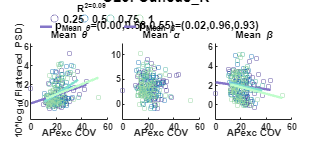



 CL3) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                         1.6425    0.42387      3.8751    0.0001365
    cond_char_0.5                      0.28612    0.72595     0.39413      0.69382
    cond_char_0.75                      1.0109    0.81788      1.2359      0.21765
    cond_char_1.0                     -0.40918    0.75679    -0.54068      0.58921
    mean_APexc_mean                    -9.7753      6.582     -1.4852      0.13877
    cond_char_0.5:mean_APexc_mean      -10.097     13.607    -0.74207      0.4

                                 SumOfSquares    DF     MeanSquares       F        pValue  
                                 ____________    ___    ___________    _______    _________

    cond_char                        3.138         3       1.046       0.82928      0.47884
    mean_APexc_mean                  10.43         1       10.43        8.2687    0.0043839
    cond_char:mean_APexc_mean       4.1111         3      1.3704        1.0864      0.35544
    Error                           312.81       248      1.2613                           
    Total                           327.15       255                                       





 CL3) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                        2.9531     0.77606      3.8052    0.00017851
    cond_char_0.5                      1.1165      1.3291     0.83999       0.40172
    cond_char_0.75                    0.66816      1.4975      0.4462       0.65584
    cond_char_1.0                     -1.1349      1.3856    -0.81908       0.41353
    mean_APexc_mean                    11.714      12.051     0.97202       0.33199
    cond_char_0.5:mean_APexc_mean     -24.858      24.913    -0.99782  

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       9.5336         3      3.1779       0.75157    0.52235
    mean_APexc_mean                 2.5011         1      2.5011       0.59152    0.44256
    cond_char:mean_APexc_mean       9.4565         3      3.1522        0.7455    0.52588
    Error                           1048.6       248      4.2283                         
    Total                           1066.8       255                                     





 CL3) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                        1.2367      0.4544      2.7215    0.0069584
    cond_char_0.5                     0.51773     0.77824     0.66525      0.50651
    cond_char_0.75                      1.038      0.8768      1.1839       0.2376
    cond_char_1.0                      1.1176     0.81131      1.3775      0.16959
    mean_APexc_mean                    11.501      7.0561        1.63      0.10437
    cond_char_0.5:mean_APexc_mean      -6.819      14.587    -0.46748      0.64

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                        3.7262        3       1.2421       0.85683    0.46412
    mean_APexc_mean                0.023923        1     0.023923      0.016503    0.89788
    cond_char:mean_APexc_mean        3.3349        3       1.1116       0.76686    0.51356
    Error                             359.5      248       1.4496                         
    Total                            365.26      255                                      



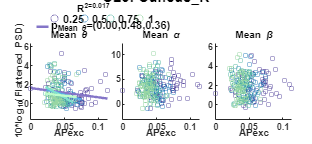



 CL3) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         0.9683      0.3406      2.8429    0.0048426
    cond_char_0.5                     -0.34241     0.58029    -0.59007      0.55568
    cond_char_0.75                     0.19653     0.65947     0.29801      0.76594
    cond_char_1.0                       -0.231     0.63075    -0.36622      0.71451
    mean_MLexc_COV                   0.0067164    0.025868     0.25964      0.79536
    cond_char_0.5:mean_MLexc_COV      0.021425    0.044513     0.48131  

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.90095         3      0.30032       0.2288     0.8763
    mean_MLexc_COV                0.37359         1      0.37359      0.28463    0.59416
    cond_char:mean_MLexc_COV      0.74967         3      0.24989      0.19038    0.90289
    Error                          325.52       248       1.3126                        
    Total                          327.15       255                                     





 CL3) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         4.1351     0.61379      6.7371    1.121e-10
    cond_char_0.5                     -0.34646      1.0457    -0.33131      0.74069
    cond_char_0.75                    -0.90755      1.1884    -0.76366       0.4458
    cond_char_1.0                     -0.91978      1.1367    -0.80919      0.41918
    mean_MLexc_COV                   -0.039364    0.046617    -0.84442      0.39925
    cond_char_0.5:mean_MLexc_COV      0.010957    0.080216      0.1366  

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      4.1416         3       1.3805       0.32387    0.80811
    mean_MLexc_COV                0.37954         1      0.37954      0.089042    0.76565
    cond_char:mean_MLexc_COV       3.4839         3       1.1613       0.27245    0.84524
    Error                          1057.1       248       4.2625                         
    Total                          1066.8       255                                      





 CL3) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat        pValue  
                                     _________    ________    _________    __________

    (Intercept)                         2.2673     0.35817       6.3301    1.1397e-09
    cond_char_0.5                      0.22957     0.61023      0.37621       0.70709
    cond_char_0.75                     0.09967      0.6935      0.14372       0.88584
    cond_char_1.0                    -0.021342      0.6633    -0.032175       0.97436
    mean_MLexc_COV                   -0.027767    0.027203      -1.0207       0.30838
    cond_char_0.5:mean_MLexc_COV     -0.014118     0.04681 

                                SumOfSquares    DF     MeanSquares       F         pValue 
                                ____________    ___    ___________    ________    ________

    cond_char                     0.24852         3     0.082838      0.057071     0.98205
    mean_MLexc_COV                 4.1777         1       4.1777        2.8782    0.091041
    cond_char:mean_MLexc_COV      0.23761         3     0.079202      0.054566     0.98318
    Error                          359.97       248       1.4515                          
    Total                          365.26       255                                       



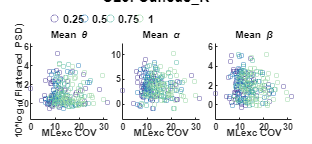



 CL3) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                         0.3797    0.47513     0.79915    0.42497
    cond_char_0.5                     -0.31922    0.70455    -0.45308    0.65089
    cond_char_0.75                    -0.23851    0.73282    -0.32547     0.7451
    cond_char_1.0                     -0.17102    0.76809    -0.22265    0.82399
    mean_MLexc_mean                      5.574     3.7818      1.4739    0.14178
    cond_char_0.5:mean_MLexc_mean       4.1688     6.5471     0.63674    0.52488
    

                                 SumOfSquares    DF     MeanSquares       F         pValue  
                                 ____________    ___    ___________    ________    _________

    cond_char                       0.2858         3     0.095267      0.075113      0.97334
    mean_MLexc_mean                 9.8637         1       9.8637        7.7771    0.0057017
    cond_char:mean_MLexc_mean       1.3432         3      0.44772       0.35301      0.78701
    Error                           314.54       248       1.2683                           
    Total                           327.15       255                                        





 CL3) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat        pValue  
                                      _________    _______    _________    __________

    (Intercept)                          3.2746    0.87167       3.7567    0.00021466
    cond_char_0.5                     -0.014265     1.2926    -0.011036        0.9912
    cond_char_0.75                      0.18436     1.3444      0.13713       0.89104
    cond_char_1.0                      -0.66093     1.4091     -0.46903       0.63946
    mean_MLexc_mean                      3.2528     6.9381      0.46883       0.63961
    cond_char_0.5:mean_MLexc_mean       -1.3587     12.01

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       1.5142         3      0.50473       0.11824    0.94934
    mean_MLexc_mean                 2.3095         1       2.3095       0.54101    0.46271
    cond_char:mean_MLexc_mean       1.0684         3      0.35614      0.083429    0.96902
    Error                           1058.7       248       4.2688                         
    Total                           1066.8       255                                      





 CL3) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                         2.0176    0.50913      3.9629    9.6864e-05
    cond_char_0.5                      0.37933    0.75497     0.50245        0.6158
    cond_char_0.75                     0.52482    0.78527     0.66833       0.50454
    cond_char_1.0                      0.41433    0.82306      0.5034       0.61513
    mean_MLexc_mean                   -0.68409     4.0525    -0.16881       0.86609
    cond_char_0.5:mean_MLexc_mean      -3.7711     7.0156    -0.53753   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       0.7866         3       0.2622      0.18004    0.90988
    mean_MLexc_mean                 3.1659         1       3.1659       2.1739    0.14164
    cond_char:mean_MLexc_mean       1.6262         3      0.54206      0.37221    0.77313
    Error                           361.17       248       1.4563                        
    Total                           365.26       255                                     



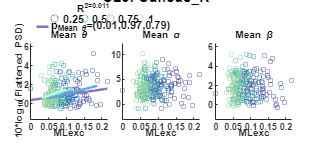



 CL3) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue  
                                   ________    _______    ________    _________

    (Intercept)                      2.8677    0.60356      4.7513    3.425e-06
    cond_char_0.5                   0.16349     1.1178     0.14626      0.88384
    cond_char_0.75                   1.5823      1.457      1.0859      0.27856
    cond_char_1.0                    0.8334     1.7174     0.48527      0.62791
    mean_StepDur                    -1.5984    0.51649     -3.0947    0.0021959
    cond_char_0.5:mean_StepDur     -0.99394     1.2814    -0.77566      0.43869
    cond_char_

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                    1.5752         3      0.52507      0.43757     0.72631
    mean_StepDur                 18.155         1       18.155       15.129    0.000129
    cond_char:mean_StepDur       5.3865         3       1.7955       1.4963     0.21609
    Error                        297.59       248          1.2                         
    Total                        327.15       255                                      





 CL3) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE         tStat       pValue 
                                   ________    _______    _________    ________

    (Intercept)                      2.1041     1.1217       1.8759    0.061848
    cond_char_0.5                    1.0066     2.0774      0.48454     0.62843
    cond_char_0.75                 -0.13196     2.7078    -0.048734     0.96117
    cond_char_1.0                   -5.8727     3.1916        -1.84    0.066958
    mean_StepDur                     1.3714    0.95984       1.4288     0.15433
    cond_char_0.5:mean_StepDur     -0.95924     2.3814     -0.40281     0.68744
    cond_char_

                              SumOfSquares    DF     MeanSquares      F        pValue 
                              ____________    ___    ___________    ______    ________

    cond_char                     17.03         3      5.6767       1.3698     0.25255
    mean_StepDur                   24.5         1        24.5       5.9118    0.015749
    cond_char:mean_StepDur       19.398         3       6.466       1.5602      0.1996
    Error                        1027.8       248      4.1442                         
    Total                        1066.8       255                                     





 CL3) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue 
                                   ________    _______    ________    ________

    (Intercept)                    0.52034     0.66074     0.78751     0.43174
    cond_char_0.5                  0.87955      1.2237     0.71875     0.47297
    cond_char_0.75                  1.7235      1.5951      1.0805     0.28097
    cond_char_1.0                  0.35328      1.8801      0.1879     0.85111
    mean_StepDur                    1.2435     0.56542      2.1992    0.028786
    cond_char_0.5:mean_StepDur     -0.5133      1.4028    -0.36591     0.71474
    cond_char_0.75:mean

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                     2.027         3      0.67566      0.46984    0.70358
    mean_StepDur                0.98627         1      0.98627      0.68583    0.40838
    cond_char:mean_StepDur      0.91204         3      0.30401       0.2114    0.88845
    Error                        356.64       248       1.4381                        
    Total                        365.26       255                                     



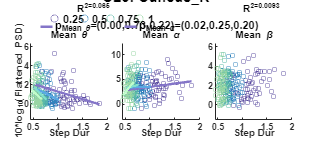



 CL3) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat      pValue 
                                     ________    ________    ________    _______

    (Intercept)                       0.53062     0.54348     0.97634    0.32985
    cond_char_0.5                     -1.1697     0.93411     -1.2523    0.21166
    cond_char_0.75                    -0.2394     0.78564    -0.30471    0.76084
    cond_char_1.0                    0.013707     0.76343    0.017954    0.98569
    mean_UDexc_COV                   0.026404    0.026755     0.98688    0.32466
    cond_char_0.5:mean_UDexc_COV     0.087816    0.059257      1.4819    0.13962
    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                       2.446         3      0.81535      0.63864     0.59078
    mean_UDexc_COV                 8.2042         1       8.2042       6.4262    0.011861
    cond_char:mean_UDexc_COV       3.0249         3       1.0083      0.78978     0.50059
    Error                          316.62       248       1.2767                         
    Total                          327.15       255                                      





 CL3) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat        pValue  
                                     ________    ________    ________    __________

    (Intercept)                        4.1772     0.98736      4.2307    3.2809e-05
    cond_char_0.5                     -1.3713       1.697    -0.80805       0.41983
    cond_char_0.75                   -0.54953      1.4273    -0.38501       0.70056
    cond_char_1.0                     0.87048       1.387     0.62761       0.53084
    mean_UDexc_COV                   -0.02612    0.048608    -0.53736        0.5915
    cond_char_0.5:mean_UDexc_COV     0.070875     0.10766     0.65835   

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                       8.601         3       2.867       0.68038    0.56479
    mean_UDexc_COV                 4.7542         1      4.7542        1.1282    0.28919
    cond_char:mean_UDexc_COV         13.6         3      4.5335        1.0759    0.35991
    Error                            1045       248      4.2138                         
    Total                          1066.8       255                                     





 CL3) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.4167     0.57262      4.2204    3.4236e-05
    cond_char_0.5                      0.43178      0.9842     0.43871       0.66126
    cond_char_0.75                     0.24977     0.82777     0.30173       0.76311
    cond_char_1.0                      0.77401     0.80437     0.96225       0.33686
    mean_UDexc_COV                   -0.024529     0.02819    -0.87015       0.38506
    cond_char_0.5:mean_UDexc_COV     -0.037022    0.062435    -0.5

                                SumOfSquares    DF     MeanSquares      F        pValue  
                                ____________    ___    ___________    ______    _________

    cond_char                       1.381         3      0.46034      0.3248      0.80743
    mean_UDexc_COV                 12.081         1       12.081       8.524    0.0038274
    cond_char:mean_UDexc_COV       5.3062         3       1.7687       1.248      0.29292
    Error                          351.49       248       1.4173                         
    Total                          365.26       255                                      



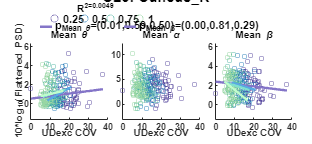



 CL3) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat      pValue 
                                      ________    _______    _________    _______

    (Intercept)                        0.69359     0.4681       1.4817    0.13968
    cond_char_0.5                     -0.24385    0.78657     -0.31002     0.7568
    cond_char_0.75                     0.30802    0.87415      0.35237    0.72486
    cond_char_1.0                     -0.59437    0.90444     -0.65717    0.51168
    mean_UDexc_mean                     25.184      31.63      0.79619    0.42668
    cond_char_0.5:mean_UDexc_mean       1.6737     44.694     0.037447    0.97016
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.0574         3      0.35245      0.27031    0.84678
    mean_UDexc_mean                 2.3583         1       2.3583       1.8087    0.17989
    cond_char:mean_UDexc_mean      0.82647         3      0.27549      0.21129    0.88853
    Error                           323.36       248       1.3039                        
    Total                           327.15       255                                     





 CL3) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                        3.1553     0.84193      3.7476    0.0002221
    cond_char_0.5                     0.43334      1.4148      0.3063      0.75963
    cond_char_0.75                    0.64182      1.5723     0.40821      0.68347
    cond_char_1.0                     -2.3105      1.6268     -1.4203      0.15677
    mean_UDexc_mean                    36.158      56.891     0.63557      0.52564
    cond_char_0.5:mean_UDexc_mean     -43.891      80.389    -0.54599      0.5

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       12.907         3      4.3022        1.0199    0.38441
    mean_UDexc_mean                 3.4696         1      3.4696       0.82255    0.36532
    cond_char:mean_UDexc_mean       8.9139         3      2.9713       0.70441    0.55019
    Error                           1046.1       248      4.2181                         
    Total                           1066.8       255                                     





 CL3) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat       pValue  
                                      _________    _______    _________    _________

    (Intercept)                           2.463    0.48901       5.0367    9.123e-07
    cond_char_0.5                       0.68494    0.82172      0.83355      0.40533
    cond_char_0.75                      0.87345    0.91321      0.95646      0.33977
    cond_char_1.0                     -0.040457    0.94485    -0.042818      0.96588
    mean_UDexc_mean                     -37.423     33.043      -1.1326       0.2585
    cond_char_0.5:mean_UDexc_mean       -22.495     46.691     -0

                                 SumOfSquares    DF     MeanSquares       F        pValue  
                                 ____________    ___    ___________    _______    _________

    cond_char                       2.0574         3      0.6858       0.48194      0.69513
    mean_UDexc_mean                 10.844         1      10.844        7.6203    0.0062027
    cond_char:mean_UDexc_mean       2.1576         3      0.7192       0.50541      0.67889
    Error                            352.9       248       1.423                           
    Total                           365.26       255                                       



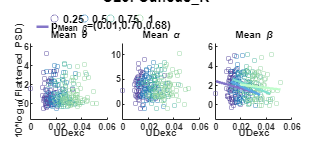



 CL3) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat        pValue  
                                     ________    _______    ________    __________

    (Intercept)                        2.6582    0.58149      4.5713    7.6515e-06
    cond_char_0.5                     0.21256     1.0961     0.19393       0.84639
    cond_char_0.75                     1.3314     1.4881     0.89471       0.37181
    cond_char_1.0                     0.51132     1.7969     0.28456       0.77622
    mean_StanceDur                    -0.9652    0.33868     -2.8499     0.0047408
    cond_char_0.5:mean_StanceDur     -0.82433    0.93041    -0.88598       0.37

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      1.0167         3      0.33891      0.27689     0.84205
    mean_StanceDur                 12.008         1       12.008        9.811    0.001943
    cond_char:mean_StanceDur       4.5338         3       1.5113       1.2347     0.29765
    Error                          303.55       248        1.224                         
    Total                          327.15       255                                      





 CL3) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue  
                                     ________    _______    ________    _________

    (Intercept)                        1.9208     1.0605      1.8111     0.071328
    cond_char_0.5                     0.99017      1.999     0.49532      0.62081
    cond_char_0.75                   -0.90735      2.714    -0.33432      0.73842
    cond_char_1.0                     -7.7287     3.2772     -2.3583     0.019134
    mean_StanceDur                     1.0458    0.61769      1.6931      0.09169
    cond_char_0.5:mean_StanceDur     -0.54889     1.6969    -0.32346      0.74662
    

                                SumOfSquares    DF     MeanSquares      F        pValue  
                                ____________    ___    ___________    ______    _________

    cond_char                       26.23         3      8.7433       2.1475     0.094808
    mean_StanceDur                 40.458         1      40.458       9.9371    0.0018191
    cond_char:mean_StanceDur         31.7         3      10.567       2.5954     0.053068
    Error                          1009.7       248      4.0714                          
    Total                          1066.8       255                                      





 CL3) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                       0.44204    0.62892     0.70286      0.4828
    cond_char_0.5                     0.89536     1.1855     0.75528      0.4508
    cond_char_0.75                     1.9332     1.6094      1.2011     0.23084
    cond_char_1.0                     0.68491     1.9434     0.35243     0.72482
    mean_StanceDur                    0.89556     0.3663      2.4449    0.015187
    cond_char_0.5:mean_StanceDur     -0.28995     1.0063    -0.28814     0.77348
    c

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      2.4719         3      0.82396      0.57548    0.63163
    mean_StanceDur                0.58437         1      0.58437      0.40814     0.5235
    cond_char:mean_StanceDur      0.88759         3      0.29586      0.20664    0.89175
    Error                          355.08       248       1.4318                        
    Total                          365.26       255                                     



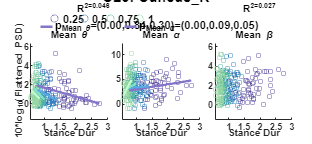



 CL3) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat        pValue  
                                        ________    _______    ________    __________

    (Intercept)                           2.8634    0.60338      4.7455    3.5154e-06
    cond_char_0.5                        0.15862     1.1161     0.14213        0.8871
    cond_char_0.75                        1.5972     1.4599      1.0941       0.27498
    cond_char_1.0                        0.84497     1.7125     0.49341       0.62216
    mean_GaitCycleDur                   -0.79668    0.25796     -3.0883     0.0022417
    cond_char_0.5:mean_GaitCycleDur     -0.49326    0.6

                                   SumOfSquares    DF     MeanSquares       F         pValue  
                                   ____________    ___    ___________    _______    __________

    cond_char                          1.605         3       0.535       0.44582       0.72047
    mean_GaitCycleDur                 18.238         1      18.238        15.198    0.00012468
    cond_char:mean_GaitCycleDur       5.4307         3      1.8102        1.5085       0.21286
    Error                             297.61       248         1.2                            
    Total                             327.15       255                                        





 CL3) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE         tStat       pValue 
                                        ________    _______    _________    ________

    (Intercept)                            2.122     1.1212       1.8926    0.059576
    cond_char_0.5                        0.98669     2.0739      0.47577     0.63466
    cond_char_0.75                      -0.16739     2.7128    -0.061705     0.95085
    cond_char_1.0                        -5.9092     3.1822      -1.8569    0.064505
    mean_GaitCycleDur                    0.67728    0.47935       1.4129     0.15893
    cond_char_0.5:mean_GaitCycleDur     -0.47006     1.1879   

                                   SumOfSquares    DF     MeanSquares      F        pValue 
                                   ____________    ___    ___________    ______    ________

    cond_char                         17.254         3      5.7514        1.388     0.24698
    mean_GaitCycleDur                 24.701         1      24.701       5.9609    0.015326
    cond_char:mean_GaitCycleDur       19.668         3      6.5561       1.5822     0.19421
    Error                             1027.6       248      4.1437                         
    Total                             1066.8       255                                     





 CL3) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                          0.52743    0.66058     0.79844     0.42538
    cond_char_0.5                        0.86966     1.2218     0.71176     0.47728
    cond_char_0.75                        1.7147     1.5982      1.0728     0.28439
    cond_char_1.0                        0.35142     1.8748     0.18744     0.85147
    mean_GaitCycleDur                    0.61813    0.28241      2.1888    0.029548
    cond_char_0.5:mean_GaitCycleDur     -0.25142    0.69985    -0.3592

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         1.9962         3      0.66539      0.46262    0.70864
    mean_GaitCycleDur                0.98301         1      0.98301      0.68345     0.4092
    cond_char:mean_GaitCycleDur      0.89475         3      0.29825      0.20736    0.89125
    Error                              356.7       248       1.4383                        
    Total                             365.26       255                                     



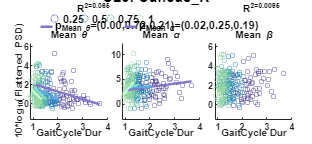



 CL3) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue 
                                              ________    _______    ________    _______

    (Intercept)                                0.82474    0.52297       1.577    0.11606
    cond_char_0.5                             -0.68306    0.88373    -0.77292    0.44031
    cond_char_0.75                              0.0167    0.96741    0.017263    0.98624
    cond_char_1.0                             -0.81691      1.014    -0.80561    0.42124
    mean_PeakUpDownVel_mean                     2.0203      4.542      0.4448    0.65685
    cond_char_0.5:mean_PeakUpDownVel_

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               1.4607         3      0.48691      0.37383    0.77196
    mean_PeakUpDownVel_mean                 2.4085         1       2.4085       1.8491    0.17512
    cond_char:mean_PeakUpDownVel_mean      0.88196         3      0.29399      0.22571    0.87847
    Error                                   323.02       248       1.3025                        
    Total                                   327.15       255                                     





 CL3) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE         tStat       pValue  
                                              _________    _______    _________    _________

    (Intercept)                                  4.1169    0.94474       4.3577    1.926e-05
    cond_char_0.5                              -0.21097     1.5965     -0.13215      0.89497
    cond_char_0.75                            -0.098317     1.7476    -0.056258      0.95518
    cond_char_1.0                               -2.5716     1.8318      -1.4039      0.16161
    mean_PeakUpDownVel_mean                     -4.0806      8.205     -0.49733       0.6194
    cond_

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               9.1181         3       3.0394       0.71505    0.54382
    mean_PeakUpDownVel_mean                0.33414         1      0.33414      0.078611    0.77942
    cond_char:mean_PeakUpDownVel_mean       7.0863         3       2.3621       0.55571    0.64477
    Error                                   1054.1       248       4.2506                         
    Total                                   1066.8       255                                      





 CL3) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE         tStat        pValue  
                                              ________    _______    _________    __________

    (Intercept)                                 2.7961     0.5461       5.1202    6.1294e-07
    cond_char_0.5                              0.68091    0.92281      0.73786        0.4613
    cond_char_0.75                             0.32242     1.0102      0.31917       0.74987
    cond_char_1.0                              -0.8963     1.0589     -0.84648        0.3981
    mean_PeakUpDownVel_mean                    -7.7684     4.7428      -1.6379        0.1027
    cond_c

                                         SumOfSquares    DF     MeanSquares       F        pValue  
                                         ____________    ___    ___________    _______    _________

    cond_char                               2.7175         3      0.90583      0.63781      0.59131
    mean_PeakUpDownVel_mean                  10.71         1        10.71       7.5413    0.0064717
    cond_char:mean_PeakUpDownVel_mean       6.0971         3       2.0324        1.431      0.23425
    Error                                   352.22       248       1.4202                          
    Total                                   365.26       255                                       



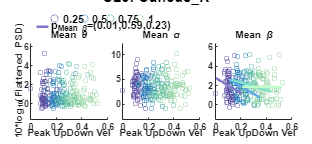



 CL4) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         1.3923     0.38478      3.6184    0.00037902
    cond_char_0.5                      0.31185     0.62224     0.50117       0.61682
    cond_char_0.75                      1.1101     0.63153      1.7577      0.080387
    cond_char_1.0                      0.59316     0.56116       1.057       0.29182
    mean_APexc_COV                   -0.024587    0.016035     -1.5333       0.12686
    cond_char_0.5:mean_APexc_COV     -0.017124     0.02761    -0.

                                SumOfSquares    DF     MeanSquares       F         pValue  
                                ____________    ___    ___________    _______    __________

    cond_char                      2.9628         3       0.9876       1.1023       0.34941
    mean_APexc_COV                 18.052         1       18.052       20.149    1.2333e-05
    cond_char:mean_APexc_COV       2.5849         3      0.86162      0.96171       0.41193
    Error                          172.02       192      0.89593                           
    Total                           192.9       199                                        





 CL4) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue 
                                     __________    ________    _________    ________

    (Intercept)                          1.5388     0.67734       2.2718    0.024205
    cond_char_0.5                     -0.032413      1.0954    -0.029592     0.97642
    cond_char_0.75                      -1.3886      1.1117      -1.2491     0.21315
    cond_char_1.0                       -1.3898     0.98783      -1.4069     0.16108
    mean_APexc_COV                   -0.0016739    0.028228    -0.059299     0.95278
    cond_char_0.5:mean_APexc_COV      -0.002399    0.048602    -0

                                SumOfSquares    DF     MeanSquares      F       pValue 
                                ____________    ___    ___________    ______    _______

    cond_char                      8.8666         3      2.9555       1.0645    0.36534
    mean_APexc_COV                 7.0812         1      7.0812       2.5506     0.1119
    cond_char:mean_APexc_COV       9.1095         3      3.0365       1.0937    0.35299
    Error                          533.05       192      2.7763                        
    Total                          548.34       199                                    





 CL4) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         1.4851     0.51624      2.8768    0.0044719
    cond_char_0.5                      -0.8587     0.83484     -1.0286      0.30497
    cond_char_0.75                    -0.78788     0.84731    -0.92986      0.35361
    cond_char_1.0                     -0.45397     0.75288    -0.60298      0.54723
    mean_APexc_COV                   0.0085316    0.021514     0.39656      0.69213
    cond_char_0.5:mean_APexc_COV       0.03956    0.037043       1.068   

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      2.2591         3      0.75303      0.46692      0.7057
    mean_APexc_COV                 7.9157         1       7.9157       4.9082    0.027904
    cond_char:mean_APexc_COV       2.3798         3      0.79328      0.49188     0.68832
    Error                          309.64       192       1.6127                         
    Total                          319.08       199                                      



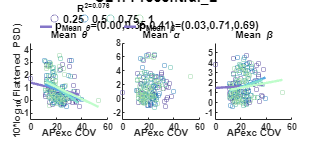



 CL4) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.29214    0.39005     0.74897    0.45479
    cond_char_0.5                     -0.50791    0.63565    -0.79904    0.42526
    cond_char_0.75                    -0.54832    0.73727    -0.74371    0.45796
    cond_char_1.0                     -0.34784    0.80168    -0.43389    0.66485
    mean_APexc_mean                     9.4399     6.3085      1.4964    0.13619
    cond_char_0.5:mean_APexc_mean       11.958     11.716      1.0206    0.30872
    

                                 SumOfSquares    DF     MeanSquares       F         pValue  
                                 ____________    ___    ___________    _______    __________

    cond_char                      0.84563         3      0.28188      0.30466         0.822
    mean_APexc_mean                 11.168         1       11.168        12.07    0.00063314
    cond_char:mean_APexc_mean       2.9105         3      0.97017       1.0486       0.37225
    Error                           177.64       192      0.92522                           
    Total                            192.9       199                                        





 CL4) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                       0.99714     0.68008      1.4662    0.14422
    cond_char_0.5                     -0.2063      1.1083    -0.18614    0.85253
    cond_char_0.75                    0.78435      1.2855     0.61016    0.54248
    cond_char_1.0                     -1.0551      1.3978    -0.75484    0.45127
    mean_APexc_mean                    8.6977      10.999     0.79076    0.43006
    cond_char_0.5:mean_APexc_mean      4.1837      20.428      0.2048    0.83795
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        3.653         3      1.2177       0.43293    0.72966
    mean_APexc_mean                 3.2427         1      3.2427        1.1529    0.28429
    cond_char:mean_APexc_mean        3.947         3      1.3157       0.46777    0.70511
    Error                           540.03       192      2.8127                         
    Total                           548.34       199                                     





 CL4) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                         1.8547    0.52017      3.5656    0.0004582
    cond_char_0.5                     -0.31155     0.8477    -0.36752      0.71364
    cond_char_0.75                      0.3173    0.98323     0.32271      0.74727
    cond_char_1.0                      0.38155     1.0691     0.35688      0.72157
    mean_APexc_mean                    -3.0664      8.413    -0.36448       0.7159
    cond_char_0.5:mean_APexc_mean       4.8977     15.625     0.31345      0.75

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.86148         3      0.28716      0.17451    0.91355
    mean_APexc_mean                 1.7234         1       1.7234       1.0474     0.3074
    cond_char:mean_APexc_mean       1.5354         3      0.51179      0.31102     0.8174
    Error                           315.94       192       1.6455                        
    Total                           319.08       199                                     



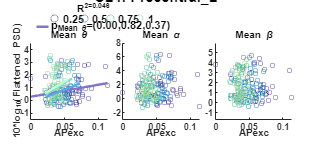



 CL4) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue 
                                     __________    ________    ________    ________

    (Intercept)                         0.90291     0.35973      2.5099    0.012902
    cond_char_0.5                       -1.0605     0.54457     -1.9474    0.052941
    cond_char_0.75                     -0.71852     0.64189     -1.1194     0.26438
    cond_char_1.0                      -0.27416     0.68001    -0.40317     0.68727
    mean_MLexc_COV                   -0.0053887    0.028104    -0.19174     0.84815
    cond_char_0.5:mean_MLexc_COV       0.081437    0.040825      1.9948 

                                SumOfSquares    DF     MeanSquares      F        pValue 
                                ____________    ___    ___________    ______    ________

    cond_char                      3.8934         3       1.2978       1.375      0.2517
    mean_MLexc_COV                 5.6856         1       5.6856       6.024    0.015004
    cond_char:mean_MLexc_COV       4.3158         3       1.4386      1.5242     0.20956
    Error                          181.21       192      0.94383                        
    Total                           192.9       199                                     





 CL4) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.2874     0.62006       3.689    0.00029309
    cond_char_0.5                     -0.51207     0.93866    -0.54553       0.58602
    cond_char_0.75                    -0.26597      1.1064    -0.24039       0.81028
    cond_char_1.0                      -1.6887      1.1721     -1.4407        0.1513
    mean_MLexc_COV                   -0.066464    0.048442      -1.372       0.17165
    cond_char_0.5:mean_MLexc_COV      0.039226    0.070369     0.

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      5.9603         3      1.9868       0.70851    0.54801
    mean_MLexc_COV                 2.1704         1      2.1704       0.77398    0.38009
    cond_char:mean_MLexc_COV       6.7446         3      2.2482       0.80173    0.49429
    Error                           538.4       192      2.8042                         
    Total                          548.34       199                                     





 CL4) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.1704     0.47481      4.5711    8.6738e-06
    cond_char_0.5                     -0.72792     0.71877     -1.0127       0.31246
    cond_char_0.75                    -0.47452     0.84723    -0.56009       0.57607
    cond_char_1.0                     -0.85583     0.89754    -0.95353       0.34152
    mean_MLexc_COV                   -0.041704    0.037094     -1.1243       0.26229
    cond_char_0.5:mean_MLexc_COV      0.056341    0.053885      1.

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      2.3698         3      0.78993       0.48042    0.69628
    mean_MLexc_COV                0.16255         1      0.16255      0.098859    0.75354
    cond_char:mean_MLexc_COV       2.2382         3      0.74606       0.45374    0.71495
    Error                           315.7       192       1.6442                         
    Total                          319.08       199                                      



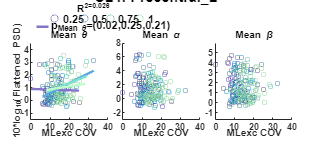



 CL4) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat      pValue 
                                      ________    _______    _________    _______

    (Intercept)                        0.73037    0.45954       1.5894    0.11362
    cond_char_0.5                     -0.06472    0.70936    -0.091238     0.9274
    cond_char_0.75                     0.24493    0.76567      0.31989     0.7494
    cond_char_1.0                      0.34909    0.80263      0.43493     0.6641
    mean_MLexc_mean                    0.93683     3.7668       0.2487    0.80386
    cond_char_0.5:mean_MLexc_mean      0.85749     6.7919      0.12625    0.89966
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.33641        3      0.11214       0.11304     0.9524
    mean_MLexc_mean                 0.03855        1      0.03855      0.038858    0.84394
    cond_char:mean_MLexc_mean      0.035216        3     0.011739      0.011833    0.99823
    Error                            190.47      192      0.99205                         
    Total                             192.9      199                                      





 CL4) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.32037    0.76785     0.41723    0.67698
    cond_char_0.5                     -0.24684     1.1853    -0.20825    0.83525
    cond_char_0.75                     0.18646     1.2794     0.14574    0.88428
    cond_char_1.0                       1.0839     1.3411     0.80819    0.41998
    mean_MLexc_mean                     10.168     6.2941      1.6155    0.10783
    cond_char_0.5:mean_MLexc_mean       4.4307     11.349     0.39041    0.69666
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.6397         3      0.87989      0.31767    0.81259
    mean_MLexc_mean                 5.0564         1       5.0564       1.8255    0.17825
    cond_char:mean_MLexc_mean       1.4386         3      0.47954      0.17313    0.91447
    Error                           531.81       192       2.7698                        
    Total                           548.34       199                                     





 CL4) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE        tStat       pValue 
                                      _________    _______    ________    ________

    (Intercept)                          1.1685    0.58958      1.9819    0.048914
    cond_char_0.5                      -0.19741     0.9101    -0.21691     0.82851
    cond_char_0.75                     -0.33307    0.98235    -0.33905     0.73494
    cond_char_1.0                     0.0060179     1.0298    0.005844     0.99534
    mean_MLexc_mean                      4.3794     4.8328     0.90618     0.36598
    cond_char_0.5:mean_MLexc_mean         2.789      8.714     0.32006     0.74

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.24441         3      0.08147       0.04989    0.98523
    mean_MLexc_mean                 2.9787         1       2.9787        1.8241    0.17842
    cond_char:mean_MLexc_mean      0.48734         3      0.16245      0.099478    0.96022
    Error                           313.53       192        1.633                         
    Total                           319.08       199                                      



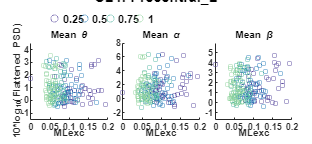



 CL4) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue 
                                   ________    _______    ________    ________

    (Intercept)                    -0.38168    0.51335    -0.74349     0.45809
    cond_char_0.5                   -1.0965     0.9704     -1.1299     0.25991
    cond_char_0.75                  -1.9888     1.2397     -1.6043     0.11028
    cond_char_1.0                   -1.6807     1.4506     -1.1586     0.24804
    mean_StepDur                     1.0761     0.4374      2.4602    0.014772
    cond_char_0.5:mean_StepDur       1.8005      1.103      1.6323     0.10425
    cond_char_0.75:mea

                              SumOfSquares    DF     MeanSquares      F         pValue  
                              ____________    ___    ___________    ______    __________

    cond_char                    3.3482         3       1.1161      1.2921       0.27839
    mean_StepDur                 18.999         1       18.999      21.995    5.1787e-06
    cond_char:mean_StepDur       8.7321         3       2.9107      3.3698      0.019635
    Error                        165.84       192      0.86377                          
    Total                         192.9       199                                       





 CL4) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                     0.94598    0.92841      1.0189    0.30952
    cond_char_0.5                  -0.98437      1.755     -0.5609    0.57552
    cond_char_0.75                    1.593     2.2419     0.71057    0.47822
    cond_char_1.0                     1.469     2.6234     0.55996    0.57616
    mean_StepDur                    0.48935    0.79105     0.61861    0.53691
    cond_char_0.5:mean_StepDur       1.3286     1.9948     0.66604    0.50618
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    ________    _______

    cond_char                    3.9218         3       1.3073       0.46272    0.70864
    mean_StepDur                0.15221         1      0.15221      0.053876     0.8167
    cond_char:mean_StepDur       3.8422         3       1.2807       0.45334    0.71523
    Error                        542.43       192       2.8252                         
    Total                        548.34       199                                      





 CL4) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat        pValue  
                                   ________    _______    ________    __________

    (Intercept)                      2.6684    0.70037        3.81    0.00018698
    cond_char_0.5                  -0.17892     1.3239    -0.13514       0.89264
    cond_char_0.75                  0.90264     1.6913     0.53371       0.59416
    cond_char_1.0                    1.0363      1.979     0.52366       0.60112
    mean_StepDur                   -0.87382    0.59675     -1.4643       0.14474
    cond_char_0.5:mean_StepDur     -0.19325     1.5048    -0.12842       0.89795
    con

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                   0.96446         3      0.32149      0.19996     0.89632
    mean_StepDur                 6.9943         1       6.9943       4.3504    0.038322
    cond_char:mean_StepDur       2.5557         3      0.85189      0.52986     0.66231
    Error                        308.69       192       1.6077                         
    Total                        319.08       199                                      



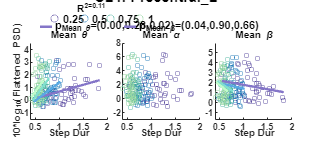



 CL4) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                         1.1618     0.52992      2.1924    0.029553
    cond_char_0.5                      0.18477     0.88322      0.2092     0.83451
    cond_char_0.75                   -0.025104      0.8127    -0.03089     0.97539
    cond_char_1.0                      0.52971      0.7165      0.7393     0.46063
    mean_UDexc_COV                   -0.016398    0.025978    -0.63122     0.52865
    cond_char_0.5:mean_UDexc_COV      -0.02057    0.056071    -0.36686     0.71

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.72707         3      0.24236      0.24776    0.86287
    mean_UDexc_COV                 2.0087         1       2.0087       2.0535    0.15348
    cond_char:mean_UDexc_COV       1.0967         3      0.36556      0.37371    0.77206
    Error                          187.81       192       0.9782                        
    Total                           192.9       199                                     





 CL4) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                          1.712     0.89931      1.9037    0.058443
    cond_char_0.5                       1.4576      1.4989     0.97243     0.33206
    cond_char_0.75                    -0.71512      1.3792     -0.5185     0.60471
    cond_char_1.0                     -0.45463       1.216    -0.37388      0.7089
    mean_UDexc_COV                   -0.010718    0.044087    -0.24311     0.80818
    cond_char_0.5:mean_UDexc_COV      -0.11472    0.095157     -1.2056     0.22

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      6.2833         3       2.0944      0.74343    0.52739
    mean_UDexc_COV                0.79286         1      0.79286      0.28143    0.59638
    cond_char:mean_UDexc_COV       5.8114         3       1.9371      0.68759    0.56064
    Error                          540.92       192       2.8173                        
    Total                          548.34       199                                     





 CL4) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.2805     0.67608      3.3731    0.00089909
    cond_char_0.5                      0.84774      1.1268     0.75233       0.45278
    cond_char_0.75                     0.34565      1.0369     0.33336       0.73922
    cond_char_1.0                     0.088585     0.91412    0.096907        0.9229
    mean_UDexc_COV                   -0.030669    0.033143    -0.92534       0.35595
    cond_char_0.5:mean_UDexc_COV     -0.076617    0.071536      -1

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      1.0495         3      0.34983      0.21971      0.88264
    mean_UDexc_COV                   12.2         1         12.2       7.6625    0.0061901
    cond_char:mean_UDexc_COV       3.2661         3       1.0887      0.68376      0.56298
    Error                          305.71       192       1.5922                          
    Total                          319.08       199                                       



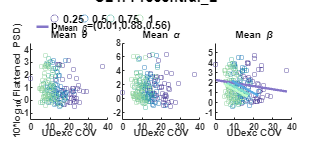



 CL4) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.66606    0.52286      1.2739    0.20425
    cond_char_0.5                     -0.27932    0.85161    -0.32799    0.74328
    cond_char_0.75                     0.75493    0.99182     0.76116     0.4475
    cond_char_1.0                     -0.10873     0.9156    -0.11876    0.90559
    mean_UDexc_mean                     12.519     36.425      0.3437    0.73145
    cond_char_0.5:mean_UDexc_mean       10.188      49.54     0.20565    0.83728
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       0.9757         3      0.32523      0.32963    0.80393
    mean_UDexc_mean                 0.3073         1       0.3073      0.31146    0.57744
    cond_char:mean_UDexc_mean      0.76697         3      0.25566      0.25912    0.85477
    Error                           189.44       192      0.98665                        
    Total                            192.9       199                                     





 CL4) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.20685    0.86901     0.23803    0.81211
    cond_char_0.5                      -1.3792     1.4154    -0.97444    0.33106
    cond_char_0.75                    0.053551     1.6484    0.032486    0.97412
    cond_char_1.0                      0.48455     1.5218     0.31842    0.75052
    mean_UDexc_mean                     93.609     60.539      1.5463    0.12369
    cond_char_0.5:mean_UDexc_mean       38.869     82.337     0.47208    0.63741
    

                                 SumOfSquares    DF     MeanSquares       F        pValue  
                                 ____________    ___    ___________    _______    _________

    cond_char                        4.078         3      1.3593       0.49875      0.68358
    mean_UDexc_mean                 20.869         1      20.869         7.657    0.0062084
    cond_char:mean_UDexc_mean        9.218         3      3.0727        1.1274      0.33918
    Error                           523.29       192      2.7255                           
    Total                           548.34       199                                       





 CL4) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        2.1621     0.67289      3.2131    0.00154
    cond_char_0.5                     -1.3374       1.096     -1.2203    0.22386
    cond_char_0.75                    -1.4548      1.2764     -1.1398     0.2558
    cond_char_1.0                     -1.4008      1.1783     -1.1888    0.23598
    mean_UDexc_mean                   -35.078      46.876    -0.74832    0.45518
    cond_char_0.5:mean_UDexc_mean      76.358      63.756      1.1977    0.23253
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       4.1597         3       1.3866      0.84851    0.46894
    mean_UDexc_mean                0.91286         1      0.91286      0.55863    0.45573
    cond_char:mean_UDexc_mean       2.8013         3      0.93376      0.57142    0.63448
    Error                           313.75       192       1.6341                        
    Total                           319.08       199                                     



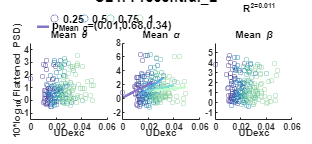



 CL4) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                      -0.35118    0.49061    -0.71581     0.47498
    cond_char_0.5                     -1.1138    0.96126     -1.1587     0.24802
    cond_char_0.75                    -2.0039     1.2763     -1.5701     0.11803
    cond_char_1.0                     -1.5954     1.4956     -1.0667     0.28745
    mean_StanceDur                    0.71183    0.28259       2.519    0.012586
    cond_char_0.5:mean_StanceDur       1.4246    0.81013      1.7585    0.080253
    

                                SumOfSquares    DF     MeanSquares      F         pValue  
                                ____________    ___    ___________    ______    __________

    cond_char                      3.2963         3       1.0988      1.2635       0.28819
    mean_StanceDur                 16.579         1       16.579      19.064    2.0641e-05
    cond_char:mean_StanceDur       9.2574         3       3.0858      3.5484      0.015545
    Error                          166.97       192      0.86964                          
    Total                           192.9       199                                       





 CL4) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                       0.95144    0.88421       1.076    0.28326
    cond_char_0.5                    -0.92025     1.7324    -0.53118    0.59591
    cond_char_0.75                     1.7001     2.3002     0.73912    0.46073
    cond_char_1.0                      1.6451     2.6955      0.6103    0.54239
    mean_StanceDur                    0.32873     0.5093     0.64547    0.51939
    cond_char_0.5:mean_StanceDur       0.9645     1.4601     0.66058    0.50967
    cond_cha

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      4.0048         3       1.3349      0.47258    0.70174
    mean_StanceDur                0.35205         1      0.35205      0.12463    0.72445
    cond_char:mean_StanceDur       3.8808         3       1.2936      0.45796    0.71199
    Error                          542.35       192       2.8247                        
    Total                          548.34       199                                     





 CL4) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE         tStat        pValue  
                                     _________    _______    _________    __________

    (Intercept)                         2.6113    0.66885       3.9041    0.00013084
    cond_char_0.5                     -0.28257     1.3105     -0.21563       0.82951
    cond_char_0.75                      0.7772       1.74      0.44667       0.65561
    cond_char_1.0                       0.8537      2.039      0.41869       0.67591
    mean_StanceDur                    -0.55866    0.38525      -1.4501       0.14865
    cond_char_0.5:mean_StanceDur     -0.088789     1.1045    -0.08

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.75562         3      0.25187      0.15583    0.92583
    mean_StanceDur                 5.0642         1       5.0642       3.1332     0.0783
    cond_char:mean_StanceDur       2.1203         3      0.70678      0.43728    0.72657
    Error                          310.33       192       1.6163                        
    Total                          319.08       199                                     



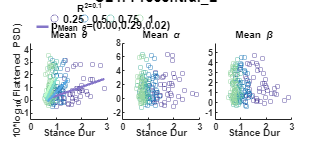



 CL4) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                         -0.38578    0.51336    -0.75148     0.45328
    cond_char_0.5                        -1.0907    0.96956      -1.125     0.26201
    cond_char_0.75                       -1.9945     1.2434      -1.604     0.11035
    cond_char_1.0                        -1.6766     1.4502     -1.1561     0.24908
    mean_GaitCycleDur                    0.53932    0.21849      2.4684    0.014447
    cond_char_0.5:mean_GaitCycleDur      0.89744    0.55069      1.62

                                   SumOfSquares    DF     MeanSquares      F         pValue  
                                   ____________    ___    ___________    ______    __________

    cond_char                         3.3388         3       1.1129      1.2887       0.27955
    mean_GaitCycleDur                 19.003         1       19.003      22.004    5.1575e-06
    cond_char:mean_GaitCycleDur       8.7221         3       2.9074      3.3665      0.019721
    Error                             165.82       192      0.86363                          
    Total                              192.9       199                                       





 CL4) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                         0.93744     0.92841      1.0097     0.3139
    cond_char_0.5                       -0.9868      1.7535    -0.56277    0.57424
    cond_char_0.75                       1.6026      2.2487     0.71267    0.47692
    cond_char_1.0                        1.4978      2.6227     0.57107    0.56862
    mean_GaitCycleDur                    0.2482     0.39514     0.62812    0.53067
    cond_char_0.5:mean_GaitCycleDur     0.66732     0.99592     0.67005    0

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                         3.9777         3      1.3259        0.46941    0.70396
    mean_GaitCycleDur                 0.1558         1      0.1558       0.055158    0.81457
    cond_char:mean_GaitCycleDur       3.8913         3      1.2971        0.45921    0.71111
    Error                             542.33       192      2.8247                          
    Total                             548.34       199                                      





 CL4) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate       SE        tStat        pValue  
                                        _________    _______    ________    __________

    (Intercept)                            2.6647    0.70049       3.804    0.00019125
    cond_char_0.5                        -0.17868      1.323    -0.13506       0.89271
    cond_char_0.75                        0.90418     1.6967     0.53291       0.59471
    cond_char_1.0                          1.0449     1.9789     0.52805       0.59807
    mean_GaitCycleDur                    -0.43483    0.29814     -1.4585       0.14634
    cond_char_0.5:mean_GaitCycleDur     -0.096333

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    _______    ________

    cond_char                         0.9706         3      0.32353       0.2012     0.89546
    mean_GaitCycleDur                 6.9761         1       6.9761       4.3383    0.038588
    cond_char:mean_GaitCycleDur       2.5593         3      0.85309      0.53053     0.66185
    Error                             308.74       192        1.608                         
    Total                             319.08       199                                      



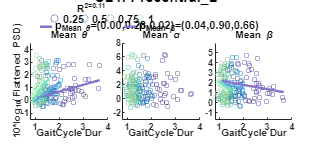



 CL4) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue 
                                              ________    _______    ________    _______

    (Intercept)                                 1.2596    0.51671      2.4377    0.01569
    cond_char_0.5                              0.18632    0.88906     0.20956    0.83423
    cond_char_0.75                              1.0331    0.98649      1.0472    0.29632
    cond_char_1.0                             -0.10132    0.91282      -0.111    0.91173
    mean_PeakUpDownVel_mean                    -3.7901     4.4848     -0.8451     0.3991
    cond_char_0.5:mean_PeakUpDownVel_

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                               1.2577         3      0.41924      0.43048      0.7314
    mean_PeakUpDownVel_mean                 2.8929         1       2.8929       2.9704    0.086412
    cond_char:mean_PeakUpDownVel_mean       1.7523         3      0.58411      0.59976      0.6159
    Error                                   186.99       192      0.97391                         
    Total                                    192.9       199                                      





 CL4) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue 
                                              ________    _______    ________    _______

    (Intercept)                                0.72336    0.87971     0.82227    0.41194
    cond_char_0.5                             -0.31813     1.5137    -0.21018    0.83375
    cond_char_0.75                            -0.23347     1.6795    -0.13901    0.88959
    cond_char_1.0                              0.26109     1.5541       0.168    0.86676
    mean_PeakUpDownVel_mean                     7.0115     7.6355     0.91828    0.35963
    cond_char_0.5:mean_PeakUpDownVel_

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                              0.35562         3      0.11854      0.041991    0.98851
    mean_PeakUpDownVel_mean                 5.6961         1       5.6961        2.0178    0.15709
    cond_char:mean_PeakUpDownVel_mean       2.2292         3      0.74305       0.26321    0.85184
    Error                                   542.01       192        2.823                         
    Total                                   548.34       199                                      





 CL4) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue  
                                              ________    _______    ________    _________

    (Intercept)                                 2.0514    0.66724      3.0744    0.0024164
    cond_char_0.5                             -0.98865     1.1481    -0.86114      0.39024
    cond_char_0.75                             -1.7076     1.2739     -1.3405      0.18167
    cond_char_1.0                              -1.8691     1.1787     -1.5856      0.11447
    mean_PeakUpDownVel_mean                    -3.3743     5.7913    -0.58265      0.56081
    cond_char_0.5:mean_P

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               5.4707         3       1.8236       1.1229      0.341
    mean_PeakUpDownVel_mean                 1.0828         1       1.0828      0.66676     0.4152
    cond_char:mean_PeakUpDownVel_mean       2.1603         3      0.72011      0.44342    0.72223
    Error                                   311.81       192        1.624                        
    Total                                   319.08       199                                     



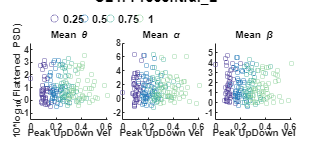



 CL5) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat      pValue 
                                     __________    ________    _________    _______

    (Intercept)                         0.15735     0.29354      0.53605    0.59238
    cond_char_0.5                      0.024674     0.50017     0.049331    0.96069
    cond_char_0.75                      0.63152     0.48444       1.3036    0.19352
    cond_char_1.0                       0.44528     0.42052       1.0589    0.29063
    mean_APexc_COV                    0.0043984    0.012161      0.36167    0.71789
    cond_char_0.5:mean_APexc_COV     -0.0010021    0.022791    -0.043969

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                       1.677         3        0.559      0.80998    0.48931
    mean_APexc_COV                0.53492         1      0.53492       0.7751    0.37946
    cond_char:mean_APexc_COV       1.4432         3      0.48108      0.69708    0.55458
    Error                          179.44       260      0.69014                        
    Total                          181.66       267                                     





 CL5) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                          3.149       1.022      3.0812    0.0022829
    cond_char_0.5                       1.2275      1.7414     0.70488      0.48152
    cond_char_0.75                      1.5326      1.6867     0.90867      0.36437
    cond_char_1.0                       1.1245      1.4641     0.76803      0.44317
    mean_APexc_COV                    0.011014    0.042341     0.26012      0.79497
    cond_char_0.5:mean_APexc_COV     -0.075119    0.079351    -0.94666  

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                       9.125         3      3.0417       0.36358     0.77935
    mean_APexc_COV                 24.756         1      24.756        2.9592    0.086581
    cond_char:mean_APexc_COV       18.118         3      6.0392        0.7219      0.5397
    Error                          2175.1       260      8.3658                          
    Total                          2214.8       267                                      





 CL5) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat        pValue  
                                     ________    ________    ________    __________

    (Intercept)                        2.8493     0.57315      4.9713    1.2082e-06
    cond_char_0.5                    -0.54024     0.97661    -0.55318       0.58062
    cond_char_0.75                   -0.76756      0.9459    -0.81146       0.41784
    cond_char_1.0                    -0.70012     0.82109    -0.85267       0.39463
    mean_APexc_COV                   0.014264    0.023746     0.60071       0.54856
    cond_char_0.5:mean_APexc_COV     0.018473    0.044501     0.41511    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                         2.6         3      0.86666      0.32939    0.80411
    mean_APexc_COV                 10.222         1       10.222        3.885    0.04978
    cond_char:mean_APexc_COV       1.6027         3      0.53424      0.20305    0.89423
    Error                           684.1       260       2.6311                        
    Total                          698.69       267                                     



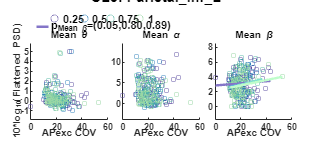



 CL5) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                       -0.027744    0.32517    -0.085321    0.93207
    cond_char_0.5                       0.57895    0.50733       1.1412    0.25485
    cond_char_0.75                      0.31617    0.56893      0.55573    0.57887
    cond_char_1.0                       0.32762    0.58085      0.56403    0.57322
    mean_APexc_mean                       4.568     4.9554      0.92182    0.35748
    cond_char_0.5:mean_APexc_mean       -10.577     9.0121      -1.1737    0.2

                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    cond_char                        0.93057       3       0.31019       0.44762    0.71919
    mean_APexc_mean               0.00058272       1    0.00058272     0.0008409    0.97689
    cond_char:mean_APexc_mean        0.95687       3       0.31896       0.46027    0.71028
    Error                             180.17     260       0.69298                         
    Total                             181.66     267                                       





 CL5) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                         2.0202    1.1307      1.7867    0.075154
    cond_char_0.5                       2.3611    1.7641      1.3384     0.18193
    cond_char_0.75                     0.99552    1.9783     0.50322     0.61524
    cond_char_1.0                     -0.58161    2.0198    -0.28796     0.77361
    mean_APexc_mean                     22.113    17.231      1.2834     0.20051
    cond_char_0.5:mean_APexc_mean      -48.319    31.337     -1.5419     0.12431
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       21.011         3      7.0036       0.83587    0.47522
    mean_APexc_mean                 3.1488         1      3.1488       0.37581    0.54039
    cond_char:mean_APexc_mean       25.699         3      8.5662        1.0224    0.38322
    Error                           2178.5       260      8.3788                         
    Total                           2214.8       267                                     





 CL5) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                         2.7725     0.6366      4.3551    1.915e-05
    cond_char_0.5                      0.65399    0.99322     0.65845      0.51083
    cond_char_0.75                      0.8422     1.1138     0.75613      0.45026
    cond_char_1.0                     -0.43685     1.1372    -0.38416      0.70118
    mean_APexc_mean                     6.4167     9.7014     0.66142      0.50893
    cond_char_0.5:mean_APexc_mean      -15.458     17.643    -0.87613      0.38

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       3.6816         3       1.2272       0.46205    0.70903
    mean_APexc_mean                0.04384         1      0.04384      0.016506    0.89787
    cond_char:mean_APexc_mean        4.428         3        1.476       0.55572    0.64474
    Error                           690.57       260        2.656                         
    Total                           698.69       267                                      



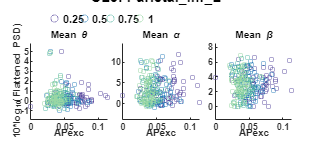



 CL5) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat      pValue 
                                     __________    ________    _________    _______

    (Intercept)                          0.3102     0.25866       1.1993    0.23152
    cond_char_0.5                      -0.22327     0.39578     -0.56411    0.57316
    cond_char_0.75                     0.095903     0.44032       0.2178    0.82775
    cond_char_1.0                     -0.090313     0.46401     -0.19464    0.84583
    mean_MLexc_COV                   -0.0043926    0.019619     -0.22389    0.82302
    cond_char_0.5:mean_MLexc_COV       0.017468    0.029804      0.58608

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.38124        3      0.12708       0.18274    0.90807
    mean_MLexc_COV                0.037405        1     0.037405      0.053786    0.81678
    cond_char:mean_MLexc_COV       0.37044        3      0.12348       0.17756    0.91155
    Error                           180.81      260      0.69544                         
    Total                           181.66      267                                      





 CL5) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         2.8702     0.90191      3.1823    0.0016387
    cond_char_0.5                       1.1084      1.3801     0.80317      0.42261
    cond_char_0.75                     0.26012      1.5353     0.16942       0.8656
    cond_char_1.0                        0.246       1.618     0.15204      0.87927
    mean_MLexc_COV                    0.043596    0.068409     0.63729       0.5245
    cond_char_0.5:mean_MLexc_COV      -0.11575     0.10392     -1.1138  

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      5.7696         3       1.9232       0.22745    0.87725
    mean_MLexc_COV                0.49769         1      0.49769      0.058861     0.8085
    cond_char:mean_MLexc_COV       10.506         3       3.5021       0.41419    0.74296
    Error                          2198.4       260       8.4554                         
    Total                          2214.8       267                                      





 CL5) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.3885     0.50366      4.7423    3.4871e-06
    cond_char_0.5                        0.213     0.77068     0.27638       0.78247
    cond_char_0.75                     0.28947     0.85739     0.33762       0.73592
    cond_char_1.0                      0.25604     0.90353     0.28337       0.77712
    mean_MLexc_COV                    0.064687    0.038202      1.6933      0.091604
    cond_char_0.5:mean_MLexc_COV     -0.034945    0.058035    -0.6

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.4226         3      0.14087      0.053422     0.9837
    mean_MLexc_COV                 5.6619         1       5.6619        2.1472    0.14404
    cond_char:mean_MLexc_COV       2.6852         3      0.89505       0.33944    0.79683
    Error                          685.58       260       2.6369                         
    Total                          698.69       267                                      



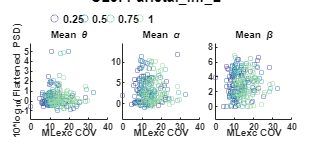



 CL5) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                       -0.22192    0.34484    -0.64355    0.52044
    cond_char_0.5                      0.47993    0.50981      0.9414    0.34738
    cond_char_0.75                     0.16142    0.55187     0.29249    0.77014
    cond_char_1.0                      0.70035    0.57065      1.2273    0.22082
    mean_MLexc_mean                     3.9626     2.7272       1.453    0.14744
    cond_char_0.5:mean_MLexc_mean      -4.0353     4.6821    -0.86184    0.38957
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.2851         3      0.42836      0.62171    0.60153
    mean_MLexc_mean                0.27853         1      0.27853      0.40426    0.52546
    cond_char:mean_MLexc_mean      0.93045         3      0.31015      0.45015    0.71741
    Error                           179.14       260        0.689                        
    Total                           181.66       267                                     





 CL5) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    ______    _________    _________

    (Intercept)                         4.0182    1.2083       3.3254    0.0010101
    cond_char_0.5                      0.13218    1.7863     0.073993      0.94107
    cond_char_0.75                    -0.55961    1.9337     -0.28939      0.77251
    cond_char_1.0                     -0.59298    1.9995     -0.29656      0.76704
    mean_MLexc_mean                    -5.1275    9.5561     -0.53657      0.59202
    cond_char_0.5:mean_MLexc_mean      -6.2173    16.406     -0.37896      0.7

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       1.7646         3       0.5882      0.069533    0.97614
    mean_MLexc_mean                 4.7293         1       4.7293       0.55907    0.45531
    cond_char:mean_MLexc_mean       1.2502         3      0.41675      0.049265    0.98551
    Error                           2199.4       260       8.4593                         
    Total                           2214.8       267                                      





 CL5) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat        pValue  
                                      ________    _______    _________    __________

    (Intercept)                         4.2628    0.67278       6.3361    1.0327e-09
    cond_char_0.5                     -0.35685    0.99462     -0.35878       0.72005
    cond_char_0.75                    -0.87039     1.0767      -0.8084        0.4196
    cond_char_1.0                       -1.123     1.1133      -1.0087       0.31404
    mean_MLexc_mean                    -9.0225     5.3207      -1.6957      0.091135
    cond_char_0.5:mean_MLexc_mean     -0.77838     9.1347    -0.0

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       3.3504         3       1.1168       0.42585    0.73464
    mean_MLexc_mean                 5.2793         1       5.2793        2.0131    0.15714
    cond_char:mean_MLexc_mean      0.31914         3      0.10638      0.040564    0.98909
    Error                           681.85       260       2.6225                         
    Total                           698.69       267                                      



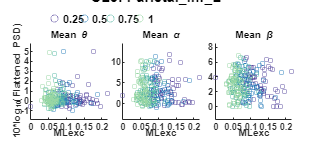



 CL5) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate       SE        tStat      pValue 
                                   _________    _______    ________    _______

    (Intercept)                    -0.087881     0.4549    -0.19319    0.84696
    cond_char_0.5                    0.40635     0.8433     0.48186    0.63031
    cond_char_0.75                  -0.51855     1.0467     -0.4954    0.62074
    cond_char_1.0                   -0.30105     1.2665     -0.2377     0.8123
    mean_StepDur                     0.29868    0.38405     0.77772    0.43744
    cond_char_0.5:mean_StepDur      -0.38238    0.95384    -0.40088    0.68884
    cond_char_0.75:mea

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                   0.48068         3      0.16023      0.23164    0.87431
    mean_StepDur                0.81715         1      0.81715       1.1813    0.27809
    cond_char:mean_StepDur      0.70107         3      0.23369      0.33784    0.79799
    Error                        179.85       260      0.69172                        
    Total                        181.66       267                                     





 CL5) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat      pValue 
                                   ________    ______    ________    _______

    (Intercept)                     2.3251      1.587      1.4651    0.14412
    cond_char_0.5                   1.1967     2.9421     0.40674    0.68453
    cond_char_0.75                 -0.8259     3.6518    -0.22616    0.82125
    cond_char_1.0                  -4.5315     4.4184     -1.0256    0.30603
    mean_StepDur                   0.92969     1.3398     0.69388    0.48838
    cond_char_0.5:mean_StepDur     -1.4876     3.3277    -0.44704    0.65522
    cond_char_0.75:mean_StepDur

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    12.404         3      4.1347       0.49112    0.68875
    mean_StepDur                 13.694         1      13.694        1.6265    0.20332
    cond_char:mean_StepDur       13.866         3      4.6219       0.54898    0.64925
    Error                          2189       260      8.4191                         
    Total                        2214.8       267                                     





 CL5) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat        pValue  
                                   ________    _______    ________    __________

    (Intercept)                      3.5853    0.88481      4.0521    6.7091e-05
    cond_char_0.5                    1.3105     1.6403     0.79894       0.42505
    cond_char_0.75                   2.3547      2.036      1.1565       0.24852
    cond_char_1.0                     1.176     2.4633     0.47742       0.63347
    mean_StepDur                   -0.35761    0.74699    -0.47873       0.63253
    cond_char_0.5:mean_StepDur      -2.0287     1.8553     -1.0935       0.27518
    con

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                    4.3923         3      1.4641       0.55948     0.64223
    mean_StepDur                 10.964         1      10.964        4.1895    0.041681
    cond_char:mean_StepDur       8.8325         3      2.9442         1.125      0.3394
    Error                         680.4       260      2.6169                          
    Total                        698.69       267                                      



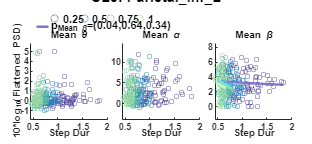



 CL5) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat      pValue 
                                     __________    ________    ________    _______

    (Intercept)                          0.4484     0.40054      1.1195    0.26397
    cond_char_0.5                       -0.4841     0.65268     -0.7417    0.45894
    cond_char_0.75                       0.4009     0.59008      0.6794    0.49749
    cond_char_1.0                        0.4821     0.54942     0.87747    0.38104
    mean_UDexc_COV                   -0.0095987    0.019434    -0.49391    0.62179
    cond_char_0.5:mean_UDexc_COV       0.029772    0.040509     0.73494    0.46

                                SumOfSquares    DF     MeanSquares      F       pValue 
                                ____________    ___    ___________    ______    _______

    cond_char                      1.8916         3      0.63054      0.9212    0.43108
    mean_UDexc_COV                 1.6143         1       1.6143      2.3584    0.12583
    cond_char:mean_UDexc_COV       2.3456         3      0.78187      1.1423    0.33249
    Error                          177.97       260      0.68448                       
    Total                          181.66       267                                    





 CL5) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         4.4874      1.3972      3.2117    0.0014857
    cond_char_0.5                     -0.35185      2.2767    -0.15454       0.8773
    cond_char_0.75                    -0.34053      2.0583    -0.16544      0.86873
    cond_char_1.0                       1.0035      1.9165     0.52362      0.60099
    mean_UDexc_COV                   -0.054601    0.067792    -0.80543      0.42131
    cond_char_0.5:mean_UDexc_COV      -0.02016     0.14131    -0.14267  

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      5.1373         3      1.7124        0.2056     0.89247
    mean_UDexc_COV                  36.77         1       36.77        4.4148    0.036591
    cond_char:mean_UDexc_COV        17.03         3      5.6765       0.68155     0.56403
    Error                          2165.5       260      8.3288                          
    Total                          2214.8       267                                      





 CL5) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat        pValue  
                                     __________    ________    ________    __________

    (Intercept)                          3.3258     0.78855      4.2176    3.4117e-05
    cond_char_0.5                       0.84129      1.2849     0.65473       0.51322
    cond_char_0.75                     -0.68313      1.1617    -0.58805       0.55701
    cond_char_1.0                      -0.04107      1.0816    -0.03797       0.96974
    mean_UDexc_COV                   -0.0076913     0.03826    -0.20103       0.84083
    cond_char_0.5:mean_UDexc_COV      -0.076161     0.07975

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                       3.516         3       1.172       0.44179    0.72332
    mean_UDexc_COV                 1.7534         1      1.7534       0.66092    0.41698
    cond_char:mean_UDexc_COV       3.9013         3      1.3004        0.4902    0.68938
    Error                          689.75       260      2.6529                         
    Total                          698.69       267                                     



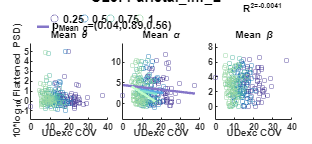



 CL5) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate       SE        tStat      pValue 
                                      _________    _______    ________    _______

    (Intercept)                         0.36788    0.34622      1.0626    0.28897
    cond_char_0.5                       0.54474    0.62377     0.87331     0.3833
    cond_char_0.75                    -0.078278    0.68556    -0.11418    0.90918
    cond_char_1.0                     -0.079863    0.65396    -0.12212     0.9029
    mean_UDexc_mean                     -7.5903      22.65    -0.33512    0.73781
    cond_char_0.5:mean_UDexc_mean       -25.332     33.974    -0.74563    0.45656
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.69894         3      0.23298      0.33661    0.79888
    mean_UDexc_mean                0.52794         1      0.52794      0.76277    0.38327
    cond_char:mean_UDexc_mean        1.028         3      0.34267      0.49509      0.686
    Error                           179.96       260      0.69214                        
    Total                           181.66       267                                     





 CL5) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                         2.0635    1.2076      1.7088    0.088681
    cond_char_0.5                       1.8725    2.1756      0.8607      0.3902
    cond_char_0.75                    -0.51524    2.3911    -0.21548     0.82956
    cond_char_1.0                     0.052009    2.2809    0.022802     0.98183
    mean_UDexc_mean                     91.361    78.998      1.1565     0.24854
    cond_char_0.5:mean_UDexc_mean      -134.33    118.49     -1.1336       0.258
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       8.3278         3      2.7759       0.32969    0.80389
    mean_UDexc_mean                  6.398         1       6.398       0.75988    0.38417
    cond_char:mean_UDexc_mean       11.639         3      3.8798        0.4608    0.70991
    Error                           2189.2       260      8.4198                         
    Total                           2214.8       267                                     





 CL5) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat        pValue  
                                      _________    _______    _________    __________

    (Intercept)                           2.551    0.67888       3.7576    0.00021179
    cond_char_0.5                     -0.054642     1.2231    -0.044674        0.9644
    cond_char_0.75                      0.50441     1.3443      0.37523        0.7078
    cond_char_1.0                       0.41558     1.2823      0.32409       0.74613
    mean_UDexc_mean                      42.526     44.413      0.95751        0.3392
    cond_char_0.5:mean_UDexc_mean       -18.707     66.618

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.64379         3       0.2146      0.080639    0.97049
    mean_UDexc_mean                 1.2934         1       1.2934       0.48602    0.48633
    cond_char:mean_UDexc_mean       2.4247         3      0.80825       0.30371     0.8227
    Error                           691.92       260       2.6612                         
    Total                           698.69       267                                      



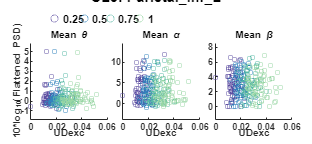



 CL5) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                      -0.03491    0.42808    -0.08155    0.93507
    cond_char_0.5                     0.25679     0.8168     0.31438    0.75348
    cond_char_0.75                   -0.61758     1.0508    -0.58774    0.55721
    cond_char_1.0                    -0.30715     1.2784    -0.24026    0.81032
    mean_StanceDur                    0.17095    0.24356     0.70189    0.48337
    cond_char_0.5:mean_StanceDur      -0.1439    0.68212    -0.21095    0.83309
    cond_cha

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.41672         3      0.13891      0.20072    0.89583
    mean_StanceDur                0.81555         1      0.81555       1.1785    0.27867
    cond_char:mean_StanceDur      0.68959         3      0.22986      0.33216     0.8021
    Error                          179.93       260      0.69203                        
    Total                          181.66       267                                     





 CL5) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                        2.2657      1.492      1.5186    0.13009
    cond_char_0.5                     0.71676     2.8468     0.25178    0.80141
    cond_char_0.75                   -0.74848     3.6622    -0.20438    0.83822
    cond_char_1.0                     -5.0512     4.4556     -1.1337    0.25798
    mean_StanceDur                    0.66346    0.84888     0.78157    0.43518
    cond_char_0.5:mean_StanceDur     -0.57995     2.3774    -0.24394    0.80747
    cond_cha

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      12.735         3      4.2452       0.50499    0.67917
    mean_StanceDur                 17.448         1      17.448        2.0755    0.15088
    cond_char:mean_StanceDur       15.005         3      5.0015       0.59497    0.61881
    Error                          2185.7       260      8.4064                         
    Total                          2214.8       267                                     





 CL5) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat        pValue  
                                     ________    _______    ________    __________

    (Intercept)                       3.5642     0.83108      4.2887    2.5357e-05
    cond_char_0.5                     1.2243      1.5857     0.77204       0.44079
    cond_char_0.75                    2.8363      2.0399      1.3904        0.1656
    cond_char_1.0                     1.5244      2.4819     0.61421       0.53961
    mean_StanceDur                   -0.2295     0.47284    -0.48536       0.62783
    cond_char_0.5:mean_StanceDur     -1.4496      1.3243     -1.0947       0.274

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      5.9957         3      1.9986       0.76624     0.51386
    mean_StanceDur                  12.75         1       12.75        4.8882    0.027912
    cond_char:mean_StanceDur       11.719         3      3.9062        1.4976     0.21561
    Error                          678.15       260      2.6083                          
    Total                          698.69       267                                      



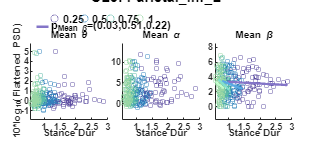



 CL5) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate       SE        tStat      pValue 
                                        _________    _______    ________    _______

    (Intercept)                         -0.083041    0.45493    -0.18254     0.8553
    cond_char_0.5                         0.40157    0.84206     0.47689    0.63384
    cond_char_0.75                       -0.53478     1.0494    -0.50961    0.61076
    cond_char_1.0                        -0.31186      1.264    -0.24672    0.80532
    mean_GaitCycleDur                     0.14707    0.19181     0.76676    0.44392
    cond_char_0.5:mean_GaitCycleDur      -0.18894    0.47586    -0.39

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                        0.49169         3       0.1639      0.23695    0.87056
    mean_GaitCycleDur                0.83135         1      0.83135       1.2019    0.27396
    cond_char:mean_GaitCycleDur      0.71738         3      0.23913      0.34571    0.79228
    Error                             179.84       260      0.69169                        
    Total                             181.66       267                                     





 CL5) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                           2.3389     1.5867       1.474    0.14168
    cond_char_0.5                         1.1625     2.9369     0.39581    0.69257
    cond_char_0.75                      -0.86975       3.66    -0.23764    0.81235
    cond_char_1.0                        -4.7772     4.4086     -1.0836    0.27954
    mean_GaitCycleDur                    0.45832    0.66898      0.6851    0.49389
    cond_char_0.5:mean_GaitCycleDur     -0.72453     1.6597    -0.43654    0

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         13.447         3      4.4825       0.53272    0.66022
    mean_GaitCycleDur                 14.795         1      14.795        1.7584    0.18599
    cond_char:mean_GaitCycleDur        15.02         3      5.0065       0.59501    0.61879
    Error                             2187.7       260      8.4143                         
    Total                             2214.8       267                                     





 CL5) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat        pValue  
                                        ________    _______    ________    __________

    (Intercept)                           3.5829    0.88493      4.0488    6.7988e-05
    cond_char_0.5                         1.3006      1.638     0.79403        0.4279
    cond_char_0.75                        2.3744     2.0412      1.1632       0.24581
    cond_char_1.0                         1.1394     2.4588     0.46342       0.64345
    mean_GaitCycleDur                   -0.17754     0.3731    -0.47585       0.63458
    cond_char_0.5:mean_GaitCycleDur      -1.0077    0.92

                                   SumOfSquares    DF     MeanSquares      F        pValue 
                                   ____________    ___    ___________    ______    ________

    cond_char                         4.3993         3      1.4664       0.5603     0.64168
    mean_GaitCycleDur                 10.856         1      10.856       4.1479    0.042698
    cond_char:mean_GaitCycleDur       8.8072         3      2.9357       1.1217     0.34075
    Error                             680.48       260      2.6172                         
    Total                             698.69       267                                     



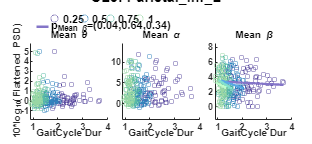



 CL5) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE        tStat      pValue 
                                              _________    _______    ________    _______

    (Intercept)                                 0.52471     0.3851      1.3625    0.17421
    cond_char_0.5                               0.18032    0.69618     0.25902    0.79583
    cond_char_0.75                            0.0099191    0.73131    0.013563    0.98919
    cond_char_1.0                              -0.18755    0.71413    -0.26263    0.79304
    mean_PeakUpDownVel_mean                     -2.3966     3.3246    -0.72087    0.47164
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               0.1346         3     0.044865      0.064687    0.97849
    mean_PeakUpDownVel_mean                0.77947         1      0.77947        1.1238    0.29007
    cond_char:mean_PeakUpDownVel_mean      0.55793         3      0.18598       0.26814    0.84833
    Error                                   180.33       260      0.69357                         
    Total                                   181.66       267                                      





 CL5) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    ______    _________    ________

    (Intercept)                                 3.4545    1.3447       2.5689    0.010761
    cond_char_0.5                               1.7645     2.431      0.72584     0.46859
    cond_char_0.75                            -0.18292    2.5537     -0.07163     0.94295
    cond_char_1.0                             -0.80656    2.4937     -0.32344     0.74662
    mean_PeakUpDownVel_mean                   -0.50168    11.609    -0.043214     0.96556
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                                 7.43         3      2.4767       0.29286    0.83055
    mean_PeakUpDownVel_mean                 3.2732         1      3.2732       0.38704    0.53441
    cond_char:mean_PeakUpDownVel_mean       9.4315         3      3.1438       0.37174    0.77346
    Error                                   2198.8       260      8.4569                         
    Total                                   2214.8       267                                     





 CL5) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat        pValue  
                                              ________    _______    ________    __________

    (Intercept)                                3.2962     0.75095      4.3894    1.6544e-05
    cond_char_0.5                             0.40594      1.3575     0.29902       0.76516
    cond_char_0.75                             1.3251      1.4261     0.92924       0.35363
    cond_char_1.0                              0.7816      1.3926     0.56127        0.5751
    mean_PeakUpDownVel_mean                   -1.1082      6.4829    -0.17094       0.86441
    cond_char_0.5

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               2.5362         3       0.8454      0.32056    0.81051
    mean_PeakUpDownVel_mean                 4.9662         1       4.9662       1.8831    0.17117
    cond_char:mean_PeakUpDownVel_mean       1.2185         3      0.40616      0.15401    0.92705
    Error                                    685.7       260       2.6373                        
    Total                                   698.69       267                                     



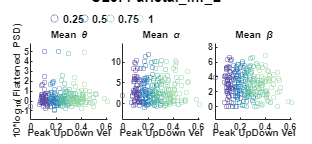



 CL6) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue 
                                     __________    ________    ________    ________

    (Intercept)                          1.2124     0.49243      2.4621    0.014872
    cond_char_0.5                      -0.20258     0.76336    -0.26538     0.79105
    cond_char_0.75                      0.53174      0.7818     0.68015     0.49739
    cond_char_1.0                       0.73888     0.70037       1.055     0.29302
    mean_APexc_COV                   -0.0070419    0.021188    -0.33235     0.74006
    cond_char_0.5:mean_APexc_COV       0.012374    0.034903     0.35451 

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                       1.936         3      0.64534      0.67618    0.56784
    mean_APexc_COV                 1.3539         1       1.3539       1.4187    0.23539
    cond_char:mean_APexc_COV       1.3509         3      0.45029       0.4718    0.70235
    Error                           152.7       160      0.95439                        
    Total                          156.88       167                                     





 CL6) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate         SE         tStat      pValue 
                                     ___________    ________    _________    _______

    (Intercept)                          0.64215     0.51578        1.245    0.21494
    cond_char_0.5                         -0.198     0.79956     -0.24764    0.80473
    cond_char_0.75                       -0.4833     0.81886     -0.59021    0.55588
    cond_char_1.0                        0.33192     0.73357      0.45247    0.65154
    mean_APexc_COV                   -0.00070658    0.022193    -0.031838    0.97464
    cond_char_0.5:mean_APexc_COV        0.005407    0.036558     

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                       1.1172        3      0.37241       0.35568    0.78509
    mean_APexc_COV                0.034157        1     0.034157      0.032623     0.8569
    cond_char:mean_APexc_COV       0.81274        3      0.27091       0.25874    0.85502
    Error                           167.53      160        1.047                         
    Total                           168.94      167                                      





 CL6) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat      pValue 
                                     __________    ________    ________    _______

    (Intercept)                         0.94627      0.5694      1.6619     0.0985
    cond_char_0.5                      0.070477     0.88269    0.079844    0.93646
    cond_char_0.75                      -0.6695     0.90401    -0.74059    0.46003
    cond_char_1.0                       -1.1058     0.80985     -1.3655    0.17403
    mean_APexc_COV                     0.014529    0.024501     0.59301    0.55401
    cond_char_0.5:mean_APexc_COV     -0.0041893    0.040359     -0.1038    0.917

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      3.3351         3      1.1117       0.87117     0.45741
    mean_APexc_COV                 6.9188         1      6.9188        5.4218    0.021138
    cond_char:mean_APexc_COV       3.7251         3      1.2417       0.97305     0.40701
    Error                          204.17       160      1.2761                          
    Total                          214.86       167                                      



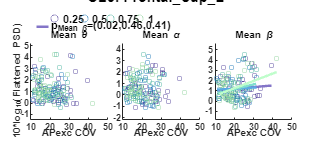



 CL6) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue  
                                      ________    _______    _______    _________

    (Intercept)                       0.26095     0.49105     0.5314      0.59588
    cond_char_0.5                      1.2388     0.83864     1.4771      0.14161
    cond_char_0.75                     1.3474     0.89069     1.5128      0.13231
    cond_char_1.0                      2.5841     0.95506     2.7057    0.0075562
    mean_APexc_mean                    12.777      7.5145     1.7003     0.091023
    cond_char_0.5:mean_APexc_mean     -20.261      15.027    -1.3483      0.17946
   

                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    cond_char                       7.6081         3        2.536      2.7286    0.045845
    mean_APexc_mean                 1.8976         1       1.8976      2.0416     0.15499
    cond_char:mean_APexc_mean       6.5383         3       2.1794      2.3449    0.074958
    Error                           148.71       160      0.92942                        
    Total                           156.88       167                                     





 CL6) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                       -0.11921    0.51668    -0.23072    0.81783
    cond_char_0.5                       1.2018    0.88243       1.362    0.17512
    cond_char_0.75                      1.0086    0.93719      1.0762    0.28346
    cond_char_1.0                       1.4223     1.0049      1.4154    0.15891
    mean_APexc_mean                     11.975     7.9068      1.5145    0.13188
    cond_char_0.5:mean_APexc_mean      -22.626     15.811      -1.431    0.15438
    

                                 SumOfSquares    DF     MeanSquares      F       pValue 
                                 ____________    ___    ___________    ______    _______

    cond_char                       3.2749         3       1.0916      1.0609    0.36744
    mean_APexc_mean                0.48178         1      0.48178      0.4682    0.49481
    cond_char:mean_APexc_mean       3.4602         3       1.1534      1.1209    0.34236
    Error                           164.64       160        1.029                       
    Total                           168.94       167                                    





 CL6) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.71598    0.58323      1.2276     0.2214
    cond_char_0.5                     -0.14421    0.99608    -0.14478    0.88507
    cond_char_0.75                     0.70234     1.0579      0.6639    0.50771
    cond_char_1.0                     -0.84969     1.1344    -0.74905    0.45493
    mean_APexc_mean                     8.8595     8.9252     0.99264    0.32239
    cond_char_0.5:mean_APexc_mean       3.9898     17.848     0.22355    0.82339
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        1.863         3        0.621      0.47363    0.70108
    mean_APexc_mean                 2.4741         1       2.4741        1.887    0.17147
    cond_char:mean_APexc_mean       2.1649         3      0.72165       0.5504    0.64859
    Error                           209.78       160       1.3111                        
    Total                           214.86       167                                     



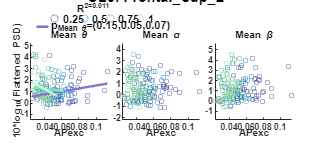



 CL6) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                        0.95385     0.41557      2.2953    0.023015
    cond_char_0.5                     -0.44872     0.60393      -0.743     0.45857
    cond_char_0.75                    -0.44554     0.70692    -0.63026     0.52943
    cond_char_1.0                     -0.24532     0.78062    -0.31426     0.75373
    mean_MLexc_COV                   0.0084763    0.031969     0.26514     0.79124
    cond_char_0.5:mean_MLexc_COV      0.037754     0.04457     0.84706     0.39

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                     0.64345         3      0.21448      0.22755     0.87712
    mean_MLexc_COV                 3.7254         1       3.7254       3.9524    0.048511
    cond_char:mean_MLexc_COV      0.86159         3       0.2872      0.30469     0.82197
    Error                          150.81       160      0.94258                         
    Total                          156.88       167                                      





 CL6) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat      pValue 
                                     __________    ________    ________    _______

    (Intercept)                         0.70305     0.43874      1.6024    0.11103
    cond_char_0.5                      -0.16995      0.6376    -0.26655    0.79016
    cond_char_0.75                     -0.23394     0.74633    -0.31345    0.75434
    cond_char_1.0                      -0.29071     0.82414    -0.35274    0.72474
    mean_MLexc_COV                   -0.0063121    0.033751    -0.18702    0.85188
    cond_char_0.5:mean_MLexc_COV      0.0068056    0.047055     0.14463    0.88

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.18581        3     0.061938      0.058954    0.98117
    mean_MLexc_COV                0.055779        1     0.055779      0.053092    0.81806
    cond_char:mean_MLexc_COV       0.21285        3     0.070949      0.067532    0.97709
    Error                            168.1      160       1.0506                         
    Total                           168.94      167                                      





 CL6) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         1.4177      0.4955      2.8611    0.0047865
    cond_char_0.5                     -0.12511     0.72009    -0.17374      0.86229
    cond_char_0.75                    -0.21386     0.84288    -0.25373      0.80003
    cond_char_1.0                     -0.14654     0.93076    -0.15744      0.87509
    mean_MLexc_COV                   -0.012366    0.038118     -0.3244      0.74606
    cond_char_0.5:mean_MLexc_COV     0.0074084    0.053143     0.13941   

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.099714        3     0.033238      0.024804     0.9947
    mean_MLexc_COV                 0.12584        1      0.12584      0.093908    0.75966
    cond_char:mean_MLexc_COV      0.046396        3     0.015465      0.011541     0.9983
    Error                            214.4      160         1.34                         
    Total                           214.86      167                                      



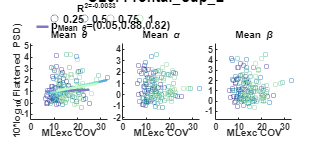



 CL6) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         1.256     0.57774      2.1741    0.031171
    cond_char_0.5                     0.19444     0.83059      0.2341      0.8152
    cond_char_0.75                    0.52417     0.87139     0.60153     0.54834
    cond_char_1.0                     0.54781     0.96891     0.56539      0.5726
    mean_MLexc_mean                   -1.6341      4.5695    -0.35762      0.7211
    cond_char_0.5:mean_MLexc_mean      -1.899      7.6516    -0.24819     0.80431
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.49371         3      0.16457      0.17123     0.9157
    mean_MLexc_mean                 1.4219         1       1.4219       1.4794    0.22566
    cond_char:mean_MLexc_mean      0.54761         3      0.18254      0.18992    0.90314
    Error                           153.78       160       0.9611                        
    Total                           156.88       167                                     





 CL6) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                         0.57424    0.60402       0.9507    0.34319
    cond_char_0.5                       0.12509    0.86837      0.14405    0.88564
    cond_char_0.75                     -0.23295    0.91102      -0.2557    0.79851
    cond_char_1.0                     -0.066828      1.013    -0.065972    0.94748
    mean_MLexc_mean                     0.42847     4.7774     0.089688    0.92865
    cond_char_0.5:mean_MLexc_mean       -2.1262     7.9996     -0.26579    0.7

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.16268        3     0.054226      0.051618    0.98447
    mean_MLexc_mean                0.081069        1     0.081069       0.07717    0.78153
    cond_char:mean_MLexc_mean       0.24689        3     0.082298       0.07834    0.97165
    Error                            168.08      160       1.0505                         
    Total                            168.94      167                                      





 CL6) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         1.2576    0.67993      1.8496    0.066212
    cond_char_0.5                     -0.60776    0.97751    -0.62175     0.53499
    cond_char_0.75                    -0.31122     1.0255    -0.30347     0.76192
    cond_char_1.0                     -0.63783     1.1403    -0.55935      0.5767
    mean_MLexc_mean                   0.082782     5.3778    0.015393     0.98774
    cond_char_0.5:mean_MLexc_mean       6.0514      9.005       0.672     0.50255
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.66671         3      0.22224      0.16695    0.91854
    mean_MLexc_mean                 1.1068         1       1.1068      0.83142    0.36323
    cond_char:mean_MLexc_mean      0.90582         3      0.30194      0.22682    0.87763
    Error                           212.99       160       1.3312                        
    Total                           214.86       167                                     



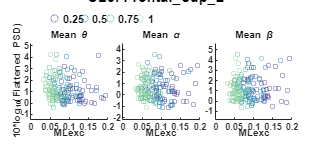



 CL6) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                    0.090655    0.64733     0.14004     0.8888
    cond_char_0.5                   0.82011     1.2473      0.6575    0.51181
    cond_char_0.75                  0.78824     1.5583     0.50584    0.61366
    cond_char_1.0                    1.6378     1.9474     0.84104    0.40158
    mean_StepDur                    0.81912    0.53381      1.5345    0.12688
    cond_char_0.5:mean_StepDur     -0.56572     1.3957    -0.40533    0.68578
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    ________    _______

    cond_char                     1.0193        3      0.33977       0.35539     0.7853
    mean_StepDur                0.044525        1     0.044525      0.046572    0.82941
    cond_char:mean_StepDur       0.36893        3      0.12298       0.12863    0.94299
    Error                         152.97      160      0.95605                         
    Total                         156.88      167                                      





 CL6) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                     0.14962    0.67744     0.22086    0.82548
    cond_char_0.5                   0.72822     1.3053     0.55788    0.57771
    cond_char_0.75                   1.0031     1.6307     0.61512    0.53935
    cond_char_1.0                   0.62981      2.038     0.30904    0.75769
    mean_StepDur                     0.4044    0.55863     0.72391    0.47018
    cond_char_0.5:mean_StepDur     -0.81761     1.4606    -0.55977    0.57642
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    0.62284        3      0.20761      0.19829    0.89744
    mean_StepDur                0.063524        1     0.063524      0.06067    0.80576
    cond_char:mean_StepDur       0.61873        3      0.20624      0.19698    0.89833
    Error                         167.53      160        1.047                        
    Total                         168.94      167                                     





 CL6) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate       SE         tStat      pValue 
                                   _________    _______    _________    _______

    (Intercept)                      0.91661    0.76303       1.2013    0.23142
    cond_char_0.5                    -1.0546     1.4703     -0.71729    0.47424
    cond_char_0.75                   0.77081     1.8368      0.41966     0.6753
    cond_char_1.0                  -0.064582     2.2955    -0.028135    0.97759
    mean_StepDur                     0.29773    0.62921      0.47318    0.63673
    cond_char_0.5:mean_StepDur        1.3698     1.6452      0.83262     0.4063
    cond_char_0

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    1.1446         3      0.38152      0.28722    0.83458
    mean_StepDur                 0.1823         1       0.1823      0.13724    0.71153
    cond_char:mean_StepDur       1.2595         3      0.41984      0.31607    0.81375
    Error                        212.53       160       1.3283                        
    Total                        214.86       167                                     



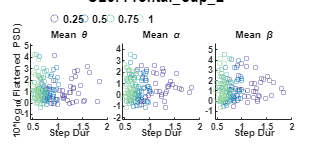



 CL6) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat       pValue  
                                     _________    ________    _________    _________

    (Intercept)                         1.8872     0.65818       2.8673    0.0046985
    cond_char_0.5                     0.021576     0.98374     0.021933      0.98253
    cond_char_0.75                    -0.44725      1.0325     -0.43317      0.66548
    cond_char_1.0                     -0.01074     0.95642    -0.011229      0.99105
    mean_UDexc_COV                   -0.041764    0.032222      -1.2961       0.1968
    cond_char_0.5:mean_UDexc_COV     -0.013963    0.059849      -

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.2436         3     0.081201      0.085554    0.96786
    mean_UDexc_COV                  2.067         1        2.067        2.1778    0.14198
    cond_char:mean_UDexc_COV      0.23867         3     0.079557      0.083821    0.96878
    Error                          151.86       160      0.94913                         
    Total                          156.88       167                                      





 CL6) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                         1.3798      0.6675      2.0672    0.040328
    cond_char_0.5                       1.0132     0.99767      1.0156     0.31135
    cond_char_0.75                     0.17771      1.0471     0.16971     0.86545
    cond_char_1.0                      0.50415     0.96996     0.51976     0.60395
    mean_UDexc_COV                   -0.037882    0.032679     -1.1592      0.2481
    cond_char_0.5:mean_UDexc_COV     -0.092765    0.060697     -1.5283     0.12

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      1.1128         3      0.37094      0.37998      0.76756
    mean_UDexc_COV                 9.8355         1       9.8355       10.075    0.0018026
    cond_char:mean_UDexc_COV       3.2097         3       1.0699        1.096      0.35258
    Error                          156.19       160      0.97621                          
    Total                          168.94       167                                       





 CL6) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue 
                                     __________    ________    ________    ________

    (Intercept)                           1.371     0.77574      1.7674    0.079068
    cond_char_0.5                        1.1647      1.1594      1.0045     0.31664
    cond_char_0.75                     0.091633      1.2169    0.075299     0.94007
    cond_char_1.0                       0.19244      1.1273     0.17072     0.86466
    mean_UDexc_COV                   -0.0051956    0.037978    -0.13681     0.89136
    cond_char_0.5:mean_UDexc_COV       -0.08707     0.07054     -1.2343  

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      1.5959         3      0.53198      0.40348    0.75069
    mean_UDexc_COV                  1.734         1        1.734       1.3151    0.25318
    cond_char:mean_UDexc_COV       2.0426         3      0.68088      0.51641    0.67156
    Error                          210.96       160       1.3185                        
    Total                          214.86       167                                     



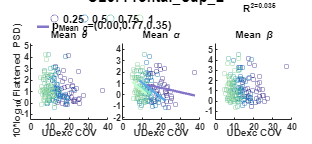



 CL6) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat      pValue 
                                      ________    _______    _________    _______

    (Intercept)                        1.1745     0.69275       1.6955    0.09193
    cond_char_0.5                     0.01539      1.0375     0.014834    0.98818
    cond_char_0.75                    0.71417      1.1572      0.61714    0.53802
    cond_char_1.0                     0.49195      1.1338       0.4339    0.66495
    mean_UDexc_mean                   -7.9769       45.73     -0.17444    0.86174
    cond_char_0.5:mean_UDexc_mean       4.384      59.402     0.073803    0.94126
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.52684         3      0.17561       0.18168    0.90872
    mean_UDexc_mean                0.38821         1      0.38821       0.40163    0.52715
    cond_char:mean_UDexc_mean      0.19002         3     0.063341      0.065529    0.97806
    Error                           154.66       160       0.9666                         
    Total                           156.88       167                                      





 CL6) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                       0.033729    0.71049    0.047472     0.9622
    cond_char_0.5                      -0.8948     1.0641    -0.84093    0.40164
    cond_char_0.75                    -0.60051     1.1869    -0.50597    0.61357
    cond_char_1.0                      0.33015     1.1628     0.28392    0.77684
    mean_UDexc_mean                     40.105     46.901      0.8551    0.39377
    cond_char_0.5:mean_UDexc_mean       30.021     60.923     0.49278    0.62284
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       1.3321         3      0.44402      0.43671     0.72703
    mean_UDexc_mean                 4.7545         1       4.7545       4.6762    0.032068
    cond_char:mean_UDexc_mean       1.9135         3      0.63784      0.62734     0.59836
    Error                           162.68       160       1.0167                         
    Total                           168.94       167                                      





 CL6) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                         0.58345    0.80447      0.72526    0.46935
    cond_char_0.5                      -0.87899     1.2048     -0.72956    0.46672
    cond_char_0.75                     -0.11942     1.3439    -0.088862     0.9293
    cond_char_1.0                     -0.074072     1.3167    -0.056258    0.95521
    mean_UDexc_mean                      46.293     53.105      0.87173    0.38466
    cond_char_0.5:mean_UDexc_mean        29.922     68.982      0.43376    0.66

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                      0.81914         3      0.27305      0.20947     0.88973
    mean_UDexc_mean                 5.1239         1       5.1239       3.9308    0.049121
    cond_char:mean_UDexc_mean       1.6938         3      0.56461      0.43314     0.72956
    Error                           208.56       160       1.3035                         
    Total                           214.86       167                                      



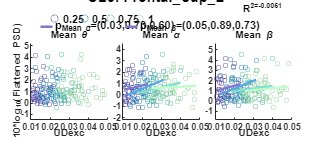



 CL6) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE         tStat      pValue 
                                     ________    _______    _________    _______

    (Intercept)                       0.28263    0.61261      0.46135    0.64517
    cond_char_0.5                     0.52827     1.2143      0.43502    0.66413
    cond_char_0.75                    0.67436     1.5998      0.42153    0.67393
    cond_char_1.0                      1.7248     2.0724      0.83226     0.4065
    mean_StanceDur                    0.44122    0.33843       1.3037    0.19419
    cond_char_0.5:mean_StanceDur     -0.16172     1.0026     -0.16129    0.87207
    

                                SumOfSquares    DF     MeanSquares        F        pValue 
                                ____________    ___    ___________    _________    _______

    cond_char                      0.83324        3       0.27775       0.28952    0.83293
    mean_StanceDur               0.0005428        1     0.0005428     0.0005658    0.98105
    cond_char:mean_StanceDur       0.27876        3      0.092921      0.096859    0.96167
    Error                            153.5      160       0.95935                         
    Total                           156.88      167                                       





 CL6) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                       0.22988    0.64057     0.35887    0.72017
    cond_char_0.5                     0.31588     1.2698     0.24877    0.80386
    cond_char_0.75                    0.65082     1.6728     0.38906    0.69775
    cond_char_1.0                    0.063959      2.167    0.029515    0.97649
    mean_StanceDur                    0.22611    0.35387     0.63894    0.52377
    cond_char_0.5:mean_StanceDur     -0.23167     1.0484    -0.22097     0.8254
    cond_cha

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.19313        3     0.064378      0.061375    0.98004
    mean_StanceDur                0.013491        1     0.013491      0.012861    0.90985
    cond_char:mean_StanceDur       0.17107        3     0.057025      0.054364    0.98325
    Error                           167.83      160       1.0489                         
    Total                           168.94      167                                      





 CL6) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                        1.0082    0.72027      1.3998    0.16351
    cond_char_0.5                     -1.2707     1.4278    -0.88999    0.37481
    cond_char_0.75                    0.33765     1.8809     0.17951    0.85776
    cond_char_1.0                    -0.78818     2.4366    -0.32347    0.74676
    mean_StanceDur                    0.14793     0.3979     0.37177    0.71056
    cond_char_0.5:mean_StanceDur       1.2068     1.1788      1.0237    0.30752
    cond_char

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      1.2877         3      0.42922      0.32365    0.80826
    mean_StanceDur                0.58625         1      0.58625      0.44206    0.50709
    cond_char:mean_StanceDur       1.6123         3      0.53742      0.40524    0.74943
    Error                          212.19       160       1.3262                        
    Total                          214.86       167                                     



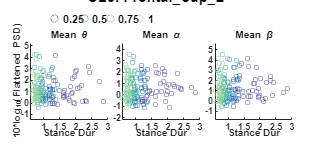



 CL6) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                         0.088275    0.64725     0.13639    0.89169
    cond_char_0.5                        0.82808     1.2464      0.6644    0.50739
    cond_char_0.75                       0.78534     1.5622     0.50272    0.61585
    cond_char_1.0                         1.6683     1.9413     0.85938    0.39142
    mean_GaitCycleDur                     0.4103    0.26669      1.5385     0.1259
    cond_char_0.5:mean_GaitCycleDur     -0.28706    0.69694    -0.41188    0

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         1.0488         3      0.34959      0.36571    0.77785
    mean_GaitCycleDur                0.04013         1      0.04013      0.04198    0.83792
    cond_char:mean_GaitCycleDur      0.38858         3      0.12953       0.1355    0.93874
    Error                             152.95       160      0.95593                        
    Total                             156.88       167                                     





 CL6) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                          0.14741    0.67739     0.21761    0.82801
    cond_char_0.5                        0.72691     1.3044     0.55727    0.57812
    cond_char_0.75                       0.99626     1.6349     0.60935    0.54315
    cond_char_1.0                        0.64212     2.0317     0.31605    0.75237
    mean_GaitCycleDur                      0.203    0.27911     0.72732    0.46809
    cond_char_0.5:mean_GaitCycleDur     -0.40738     0.7294    -0.55852    0

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                          0.6189        3       0.2063       0.19703     0.8983
    mean_GaitCycleDur                0.063426        1     0.063426      0.060576     0.8059
    cond_char:mean_GaitCycleDur       0.61175        3      0.20392       0.19475    0.89985
    Error                              167.53      160        1.047                         
    Total                              168.94      167                                      





 CL6) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE         tStat      pValue 
                                        ________    _______    _________    _______

    (Intercept)                          0.91287    0.76289       1.1966    0.23323
    cond_char_0.5                        -1.0586      1.469     -0.72057    0.47223
    cond_char_0.75                        0.7807     1.8413        0.424    0.67214
    cond_char_1.0                       -0.12787     2.2881    -0.055886     0.9555
    mean_GaitCycleDur                    0.15035    0.31434      0.47831    0.63308
    cond_char_0.5:mean_GaitCycleDur       0.6878    0.82146      0.837

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         1.1565         3       0.3855      0.29028    0.83238
    mean_GaitCycleDur                0.20805         1      0.20805      0.15666    0.69278
    cond_char:mean_GaitCycleDur       1.2788         3      0.42626      0.32097     0.8102
    Error                             212.49       160        1.328                        
    Total                             214.86       167                                     



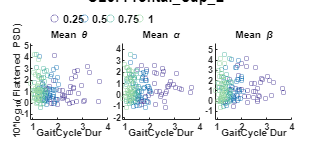



 CL6) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat        pValue  
                                              ________    _______    ________    __________

    (Intercept)                                 2.4571    0.70476      3.4864    0.00063209
    cond_char_0.5                              -1.5116     1.0545     -1.4334       0.15368
    cond_char_0.75                            -0.94506     1.1066    -0.85402       0.39437
    cond_char_1.0                             -0.88161     1.1152    -0.79057       0.43036
    mean_PeakUpDownVel_mean                    -12.006     5.9035     -2.0337      0.043633
    cond_char_0.

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                                2.028         3      0.67599      0.71532     0.5442
    mean_PeakUpDownVel_mean                 2.4831         1       2.4831       2.6275    0.10699
    cond_char:mean_PeakUpDownVel_mean       3.5029         3       1.1676       1.2356    0.29867
    Error                                    151.2       160      0.94502                        
    Total                                   156.88       167                                     





 CL6) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    _______    ________    ________

    (Intercept)                                 1.3251    0.73415       1.805    0.072957
    cond_char_0.5                              -1.9555     1.0985     -1.7802    0.076937
    cond_char_0.75                             -1.6544     1.1527     -1.4352     0.15319
    cond_char_1.0                             -0.81196     1.1617    -0.69897     0.48558
    mean_PeakUpDownVel_mean                    -5.9892     6.1497     -0.9739     0.33158
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               3.9004         3       1.3001       1.2679    0.28731
    mean_PeakUpDownVel_mean                0.17008         1      0.17008      0.16586    0.68436
    cond_char:mean_PeakUpDownVel_mean       3.2414         3       1.0805       1.0536    0.37057
    Error                                   164.08       160       1.0255                        
    Total                                   168.94       167                                     





 CL6) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue 
                                              ________    _______    ________    _______

    (Intercept)                                 1.3409    0.83805         1.6    0.11157
    cond_char_0.5                               -0.682     1.2539    -0.54389    0.58727
    cond_char_0.75                            -0.48277     1.3159    -0.36688    0.71419
    cond_char_1.0                             -0.47904     1.3261    -0.36125    0.71839
    mean_PeakUpDownVel_mean                   -0.62717       7.02    -0.08934    0.92892
    cond_char_0.5:mean_PeakUpDownVel_m

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                              0.44095         3      0.14698       0.10999    0.95416
    mean_PeakUpDownVel_mean                0.24861         1      0.24861       0.18605    0.66681
    cond_char:mean_PeakUpDownVel_mean      0.29365         3     0.097884      0.073251    0.97425
    Error                                   213.81       160       1.3363                         
    Total                                   214.86       167                                      



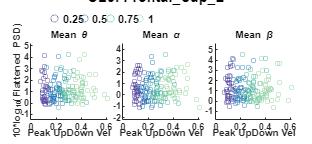



 CL7) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue 
                                     __________    ________    _________    ________

    (Intercept)                         0.70011     0.30388       2.3039    0.022658
    cond_char_0.5                       0.01194      0.5738     0.020809     0.98343
    cond_char_0.75                      -0.1281     0.56481     -0.22681      0.8209
    cond_char_1.0                      -0.17154     0.47554     -0.36072     0.71884
    mean_APexc_COV                   -0.0083027     0.01255     -0.66159     0.50929
    cond_char_0.5:mean_APexc_COV     -0.0012594    0.026359    -0

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.08301         3      0.02767      0.057687    0.98174
    mean_APexc_COV                0.05836         1      0.05836       0.12167    0.72774
    cond_char:mean_APexc_COV      0.15471         3     0.051571       0.10752    0.95559
    Error                          69.071       144      0.47966                         
    Total                           69.64       151                                      





 CL7) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat       pValue  
                                     ________    ________    ________    _________

    (Intercept)                         2.484      0.9499       2.615    0.0098716
    cond_char_0.5                     -1.6548      1.7936    -0.92259      0.35777
    cond_char_0.75                    -1.1818      1.7655    -0.66935      0.50434
    cond_char_1.0                    -0.72939      1.4865    -0.49067       0.6244
    mean_APexc_COV                    0.00901    0.039229     0.22968      0.81867
    cond_char_0.5:mean_APexc_COV     0.069897    0.082397      0.8483      0.39

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      4.8593         3      1.6198        0.3456    0.79238
    mean_APexc_COV                 9.9416         1      9.9416        2.1212    0.14745
    cond_char:mean_APexc_COV       4.2742         3      1.4247       0.30399    0.82248
    Error                          674.91       144      4.6869                         
    Total                          687.25       151                                     





 CL7) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                         1.3574     0.42177      3.2184    0.001593
    cond_char_0.5                      0.32829      0.7964     0.41221      0.6808
    cond_char_0.75                    0.069677     0.78392    0.088883      0.9293
    cond_char_1.0                      0.11336     0.66003     0.17176     0.86387
    mean_APexc_COV                   -0.018069    0.017418     -1.0374      0.3013
    cond_char_0.5:mean_APexc_COV     -0.020471    0.036585    -0.55954     0.576

                                SumOfSquares    DF     MeanSquares       F         pValue 
                                ____________    ___    ___________    ________    ________

    cond_char                     0.15963         3     0.053209      0.057586     0.98179
    mean_APexc_COV                 4.3758         1       4.3758        4.7357    0.031173
    cond_char:mean_APexc_COV      0.44313         3      0.14771       0.15986     0.92317
    Error                          133.06       144        0.924                          
    Total                          138.23       151                                       



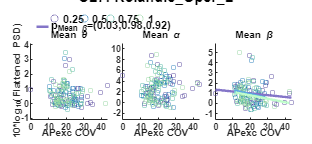



 CL7) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                        0.66857    0.34972      1.9117    0.057897
    cond_char_0.5                     -0.48933    0.67502    -0.72491     0.46968
    cond_char_0.75                    -0.50745    0.78297    -0.64812     0.51794
    cond_char_1.0                      0.11797    0.63323      0.1863     0.85247
    mean_APexc_mean                    -2.5872     5.5201    -0.46868     0.64001
    cond_char_0.5:mean_APexc_mean       9.4841     12.824     0.73954     0.46078
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       0.49482        3      0.16494      0.34528    0.79262
    mean_APexc_mean                0.065303        1     0.065303       0.1367    0.71213
    cond_char:mean_APexc_mean       0.57234        3      0.19078      0.39936    0.75366
    Error                             68.79      144      0.47771                        
    Total                             69.64      151                                     





 CL7) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    ______    _________    ________

    (Intercept)                         2.7029    1.0945       2.4695    0.014698
    cond_char_0.5                       1.1925    2.1126      0.56447     0.57331
    cond_char_0.75                      2.6213    2.4504       1.0697     0.28653
    cond_char_1.0                      0.13627    1.9818     0.068763     0.94527
    mean_APexc_mean                   -0.26875    17.276    -0.015557     0.98761
    cond_char_0.5:mean_APexc_mean      -29.448    40.135     -0.73371     0.46432
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        6.242         3      2.0807       0.44469    0.72143
    mean_APexc_mean                 9.2986         1      9.2986        1.9873    0.16077
    cond_char:mean_APexc_mean       8.8926         3      2.9642       0.63352    0.59455
    Error                           673.76       144      4.6789                         
    Total                           687.25       151                                     





 CL7) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.34726    0.48669     0.71351    0.47668
    cond_char_0.5                     -0.27346    0.93941     -0.2911    0.77139
    cond_char_0.75                    -0.92118     1.0896    -0.84541    0.39929
    cond_char_1.0                      0.56144    0.88125      0.6371    0.52507
    mean_APexc_mean                     10.059     7.6822      1.3093    0.19251
    cond_char_0.5:mean_APexc_mean       6.7923     17.847     0.38058    0.70407
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       1.4603         3      0.48677      0.52613     0.66502
    mean_APexc_mean                 2.6072         1       2.6072        2.818    0.095382
    cond_char:mean_APexc_mean       1.5082         3      0.50273      0.54337     0.65338
    Error                           133.23       144       0.9252                         
    Total                           138.23       151                                      



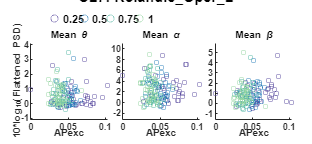



 CL7) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat        pValue  
                                     __________    ________    _________    __________

    (Intercept)                         0.83805     0.24726       3.3894    0.00090385
    cond_char_0.5                      0.075402     0.42727      0.17647       0.86017
    cond_char_0.75                    0.0038887     0.48075    0.0080889       0.99356
    cond_char_1.0                      -0.13447     0.49545     -0.27141       0.78646
    mean_MLexc_COV                    -0.027369    0.018619      -1.4699       0.14376
    cond_char_0.5:mean_MLexc_COV     -0.0055928    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.067849        3     0.022616      0.048269     0.9859
    mean_MLexc_COV                  1.3292        1       1.3292        2.8369    0.09429
    cond_char:mean_MLexc_COV       0.24779        3     0.082597       0.17628    0.91232
    Error                           67.472      144      0.46855                         
    Total                            69.64      151                                      





 CL7) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat         pValue  
                                     __________    ________    __________    __________

    (Intercept)                          3.0165     0.78641        3.8358    0.00018662
    cond_char_0.5                      -0.40857       1.359      -0.30065       0.76412
    cond_char_0.75                     -0.05898      1.5291     -0.038573       0.96928
    cond_char_1.0                     -0.001949      1.5758    -0.0012369       0.99901
    mean_MLexc_COV                    -0.027794    0.059218      -0.46935       0.63953
    cond_char_0.5:mean_MLexc_COV       0.013

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.4729         3      0.15763      0.033257    0.99183
    mean_MLexc_COV                 2.3917         1       2.3917        0.5046    0.47863
    cond_char:mean_MLexc_COV      0.22395         3     0.074649      0.015749    0.99729
    Error                          682.54       144       4.7398                         
    Total                          687.25       151                                      





 CL7) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue  
                                     __________    ________    _________    _________

    (Intercept)                         0.98771     0.35227       2.8039    0.0057463
    cond_char_0.5                     -0.014206     0.60873    -0.023337      0.98141
    cond_char_0.75                      0.12192     0.68493      0.17801      0.85897
    cond_char_1.0                       0.30849     0.70587      0.43703      0.66274
    mean_MLexc_COV                   -0.0031054    0.026526     -0.11707      0.90697
    cond_char_0.5:mean_MLexc_COV     -0.0031433    0.047243

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.21618         3     0.072058      0.075766    0.97296
    mean_MLexc_COV                0.61967         1      0.61967       0.65155    0.42089
    cond_char:mean_MLexc_COV      0.37673         3      0.12558       0.13204    0.94087
    Error                          136.95       144      0.95107                         
    Total                          138.23       151                                      



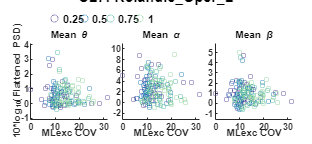



 CL7) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                         0.25324    0.36792      0.68831    0.49237
    cond_char_0.5                      -0.17415    0.56384     -0.30886    0.75787
    cond_char_0.75                    -0.069423     0.6071     -0.11435    0.90912
    cond_char_1.0                        0.2026    0.60034      0.33748    0.73624
    mean_MLexc_mean                      2.1765     2.9339      0.74184     0.4594
    cond_char_0.5:mean_MLexc_mean        2.4325     5.2418      0.46405    0.6

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.17202         3     0.057341      0.12116    0.94752
    mean_MLexc_mean                0.74047         1      0.74047       1.5646    0.21302
    cond_char:mean_MLexc_mean      0.21304         3     0.071014      0.15005    0.92952
    Error                            68.15       144      0.47327                        
    Total                            69.64       151                                     





 CL7) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                         2.113     1.1637      1.8158    0.071478
    cond_char_0.5                     0.74752     1.7833     0.41917     0.67572
    cond_char_0.75                    0.33355     1.9201     0.17371     0.86234
    cond_char_1.0                     -0.6355     1.8988    -0.33469     0.73834
    mean_MLexc_mean                    4.8015     9.2794     0.51743     0.60565
    cond_char_0.5:mean_MLexc_mean     -9.2162     16.579    -0.55589     0.57915
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.3638         3      0.78795      0.16643    0.91886
    mean_MLexc_mean                 1.0012         1       1.0012      0.21147    0.64631
    cond_char:mean_MLexc_mean       2.9266         3      0.97554      0.20606    0.89207
    Error                           681.74       144       4.7343                        
    Total                           687.25       151                                     





 CL7) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                        0.89317    0.52114      1.7139    0.088703
    cond_char_0.5                       0.5866    0.79866     0.73448     0.46385
    cond_char_0.75                     0.17358    0.85993     0.20185     0.84032
    cond_char_1.0                     0.035954    0.85036    0.042281     0.96633
    mean_MLexc_mean                    0.48285     4.1558     0.11619     0.90767
    cond_char_0.5:mean_MLexc_mean      -6.6072     7.4249    -0.88987     0.37502
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.58444         3      0.19481      0.20516    0.89269
    mean_MLexc_mean                 0.4024         1       0.4024      0.42378    0.51609
    cond_char:mean_MLexc_mean      0.77762         3      0.25921      0.27298    0.84481
    Error                           136.73       144      0.94955                        
    Total                           138.23       151                                     



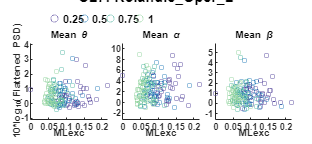



 CL7) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                     0.34772    0.50576     0.68752    0.49286
    cond_char_0.5                  -0.45102    0.97617    -0.46203    0.64476
    cond_char_0.75                 -0.57963     1.3445    -0.43112    0.66702
    cond_char_1.0                   0.37645     1.6756     0.22466    0.82256
    mean_StepDur                    0.14486    0.43143     0.33578    0.73753
    cond_char_0.5:mean_StepDur      0.63214     1.1231     0.56287     0.5744
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                   0.21238         3     0.070792      0.14813    0.93075
    mean_StepDur                 0.1441         1       0.1441      0.30153    0.58378
    cond_char:mean_StepDur      0.31461         3      0.10487      0.21944    0.88278
    Error                        68.818       144       0.4779                        
    Total                         69.64       151                                     





 CL7) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat      pValue 
                                   ________    ______    ________    _______

    (Intercept)                      3.6577    1.5709      2.3284    0.02128
    cond_char_0.5                    2.1982     3.032     0.72502    0.46962
    cond_char_0.75                   4.7365    4.1758      1.1343    0.25857
    cond_char_1.0                   0.57296    5.2044     0.11009    0.91249
    mean_StepDur                   -0.84939      1.34    -0.63387    0.52717
    cond_char_0.5:mean_StepDur      -3.4299    3.4882    -0.98327    0.32712
    cond_char_0.75:mean_StepDur

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    7.1861         3      2.3954       0.51957    0.66948
    mean_StepDur                 11.607         1      11.607        2.5177    0.11477
    cond_char:mean_StepDur       12.118         3      4.0394       0.87616    0.45508
    Error                        663.89       144      4.6103                         
    Total                        687.25       151                                     





 CL7) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate       SE         tStat      pValue 
                                   _________    _______    _________    _______

    (Intercept)                    -0.055113    0.70786    -0.077859    0.93805
    cond_char_0.5                     0.1223     1.3662     0.089515     0.9288
    cond_char_0.75                  -0.10635     1.8817    -0.056517    0.95501
    cond_char_1.0                   -0.26032     2.3452       -0.111    0.91177
    mean_StepDur                     0.88003    0.60382       1.4574    0.14717
    cond_char_0.5:mean_StepDur       0.16154     1.5718      0.10277    0.91829
    cond_char_0

                              SumOfSquares    DF     MeanSquares        F        pValue 
                              ____________    ___    ___________    _________    _______

    cond_char                   0.026426        3     0.0088086     0.0094095    0.99874
    mean_StepDur                  1.1313        1        1.1313        1.2085    0.27346
    cond_char:mean_StepDur       0.12216        3      0.040721      0.043498    0.98789
    Error                          134.8      144       0.93614                         
    Total                         138.23      151                                       



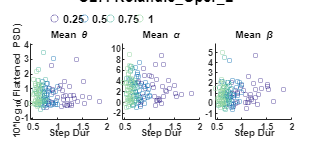



 CL7) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    ________    _______

    (Intercept)                        0.47471     0.43735      1.0854    0.27954
    cond_char_0.5                     -0.27476     0.75155     -0.3656     0.7152
    cond_char_0.75                     0.58659     0.69998     0.83802    0.40341
    cond_char_1.0                      0.49859     0.65335     0.76312    0.44664
    mean_UDexc_COV                   0.0020611    0.022575    0.091298    0.92738
    cond_char_0.5:mean_UDexc_COV      0.021016    0.049255     0.42668    0.67025
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.80308         3      0.26769      0.56248    0.64063
    mean_UDexc_COV                0.28627         1      0.28627       0.6015    0.43928
    cond_char:mean_UDexc_COV      0.80796         3      0.26932      0.56589    0.63836
    Error                          68.533       144      0.47592                        
    Total                           69.64       151                                     





 CL7) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                         4.0293       1.351      2.9826    0.003358
    cond_char_0.5                      -1.0167      2.3215    -0.43793     0.66209
    cond_char_0.75                     0.88959      2.1622     0.41143     0.68137
    cond_char_1.0                       1.1393      2.0182      0.5645     0.57329
    mean_UDexc_COV                   -0.071689    0.069735      -1.028     0.30566
    cond_char_0.5:mean_UDexc_COV      0.030065     0.15215      0.1976     0.84

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      4.4033         3      1.4678       0.32322     0.80857
    mean_UDexc_COV                 27.085         1      27.085        5.9644    0.015809
    cond_char:mean_UDexc_COV       13.451         3      4.4837       0.98737     0.40063
    Error                          653.92       144      4.5411                          
    Total                          687.25       151                                      





 CL7) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                         1.4723      0.6006      2.4514    0.015426
    cond_char_0.5                      0.67982      1.0321     0.65868     0.51115
    cond_char_0.75                      0.7917     0.96127      0.8236     0.41153
    cond_char_1.0                      0.40829     0.89724     0.45505     0.64976
    mean_UDexc_COV                   -0.027845    0.031003    -0.89814     0.37061
    cond_char_0.5:mean_UDexc_COV     -0.063509    0.067642     -0.9389     0.349

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                     0.74247         3      0.24749      0.27574      0.84283
    mean_UDexc_COV                 8.3929         1       8.3929       9.3509    0.0026579
    cond_char:mean_UDexc_COV       3.1237         3       1.0412       1.1601      0.32721
    Error                          129.25       144      0.89755                          
    Total                          138.23       151                                       



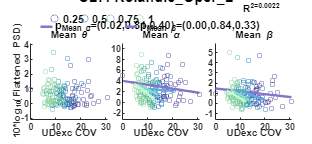



 CL7) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                        0.81865    0.32309      2.5338    0.012353
    cond_char_0.5                      -0.1901    0.61642     -0.3084     0.75822
    cond_char_0.75                    -0.57394    0.71618    -0.80139     0.42422
    cond_char_1.0                     -0.98183    0.75057     -1.3081     0.19292
    mean_UDexc_mean                    -21.068     20.921      -1.007     0.31561
    cond_char_0.5:mean_UDexc_mean       15.511     32.974      0.4704     0.63878
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.96206        3      0.32069       0.67756    0.56714
    mean_UDexc_mean                0.011709        1     0.011709      0.024739    0.87524
    cond_char:mean_UDexc_mean        1.1753        3      0.39176       0.82773    0.48064
    Error                            68.154      144      0.47329                         
    Total                             69.64      151                                      





 CL7) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue  
                                      ________    ______    ________    _________

    (Intercept)                           2.87    1.0089      2.8447    0.0050928
    cond_char_0.5                      0.73215    1.9248     0.38037      0.70423
    cond_char_0.75                    -0.83301    2.2363    -0.37249      0.71007
    cond_char_1.0                      -4.5901    2.3437     -1.9585     0.052107
    mean_UDexc_mean                    -12.645    65.327    -0.19357      0.84679
    cond_char_0.5:mean_UDexc_mean      -45.029    102.96    -0.43734      0.66252
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       21.115         3       7.0382       1.5251    0.21054
    mean_UDexc_mean                0.86503         1      0.86503      0.18744     0.6657
    cond_char:mean_UDexc_mean       17.595         3       5.8651       1.2709    0.28668
    Error                           664.54       144       4.6148                        
    Total                           687.25       151                                     





 CL7) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat       pValue 
                                      _________    _______    _________    ________

    (Intercept)                         0.91559    0.45806       1.9989    0.047507
    cond_char_0.5                       0.53712    0.87392      0.61461     0.53978
    cond_char_0.75                    -0.079749     1.0153    -0.078544      0.9375
    cond_char_1.0                      -0.60896     1.0641     -0.57227     0.56803
    mean_UDexc_mean                      2.4344      29.66     0.082075      0.9347
    cond_char_0.5:mean_UDexc_mean        -29.98     46.748     -0.64132 

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                        0.8804        3      0.29347       0.30849    0.81922
    mean_UDexc_mean                0.028163        1     0.028163      0.029604    0.86363
    cond_char:mean_UDexc_mean       0.83877        3      0.27959        0.2939    0.82975
    Error                            136.99      144       0.9513                         
    Total                            138.23      151                                      



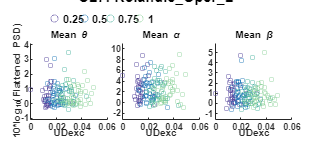



 CL7) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE         tStat      pValue 
                                     _________    _______    _________    _______

    (Intercept)                        0.15606    0.48012      0.32505    0.74562
    cond_char_0.5                     -0.58968    0.94514     -0.62391    0.53367
    cond_char_0.75                     -1.1216     1.4117     -0.79454    0.42819
    cond_char_1.0                      0.29253     1.7848      0.16391    0.87003
    mean_StanceDur                     0.21321    0.27873      0.76492    0.44557
    cond_char_0.5:mean_StanceDur       0.67901    0.80684      0.84157    0.40143
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.45452         3      0.15151      0.32195    0.80949
    mean_StanceDur                0.53435         1      0.53435       1.1355    0.28839
    cond_char:mean_StanceDur      0.80271         3      0.26757      0.56859    0.63658
    Error                          67.765       144      0.47059                        
    Total                           69.64       151                                     





 CL7) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                        3.2352     1.5112      2.1408    0.033975
    cond_char_0.5                      1.9595     2.9749     0.65868     0.51115
    cond_char_0.75                     4.6578     4.4434      1.0482     0.29628
    cond_char_1.0                     -1.0623     5.6176    -0.18911     0.85028
    mean_StanceDur                   -0.32731    0.87733    -0.37307     0.70964
    cond_char_0.5:mean_StanceDur      -2.2577     2.5396    -0.88901     0.37548
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      6.7856         3      2.2619       0.48515    0.69312
    mean_StanceDur                 4.4488         1      4.4488       0.95424    0.33028
    cond_char:mean_StanceDur       10.132         3      3.3773       0.72441    0.53899
    Error                          671.35       144      4.6622                         
    Total                          687.25       151                                     





 CL7) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE        tStat      pValue 
                                     _________    _______    ________    _______

    (Intercept)                      -0.087979     0.6759    -0.13017    0.89662
    cond_char_0.5                     0.014916     1.3305     0.01121    0.99107
    cond_char_0.75                    0.026147     1.9873    0.013157    0.98952
    cond_char_1.0                     -0.46356     2.5125     -0.1845    0.85388
    mean_StanceDur                     0.61999    0.39239        1.58     0.1163
    cond_char_0.5:mean_StanceDur       0.29199     1.1359     0.25707    0.79749
    c

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.033568        3     0.011189      0.011998    0.99819
    mean_StanceDur                  1.0941        1       1.0941        1.1732    0.28056
    cond_char:mean_StanceDur       0.21671        3     0.072236      0.077455     0.9721
    Error                            134.3      144      0.93263                         
    Total                           138.23      151                                      



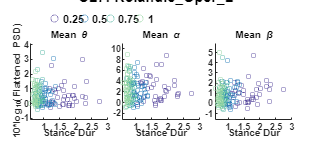



 CL7) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                          0.34945    0.50573     0.69098    0.49069
    cond_char_0.5                       -0.45666    0.97471    -0.46851    0.64013
    cond_char_0.75                      -0.58096      1.348    -0.43097    0.66714
    cond_char_1.0                         0.3222     1.6673     0.19325    0.84704
    mean_GaitCycleDur                    0.07161     0.2155      0.3323    0.74015
    cond_char_0.5:mean_GaitCycleDur      0.31922    0.56032     0.56972    0

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         0.2056         3     0.068534      0.14341    0.93375
    mean_GaitCycleDur                0.15921         1      0.15921      0.33314    0.56471
    cond_char:mean_GaitCycleDur      0.31157         3      0.10386      0.21732    0.88426
    Error                             68.819       144      0.47791                        
    Total                              69.64       151                                     





 CL7) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                           3.6682     1.5707      2.3354    0.020906
    cond_char_0.5                         2.1781     3.0274     0.71949     0.47301
    cond_char_0.75                        4.7308     4.1868      1.1299     0.26039
    cond_char_1.0                        0.61283     5.1784     0.11834     0.90596
    mean_GaitCycleDur                   -0.42891    0.66932    -0.64081     0.52266
    cond_char_0.5:mean_GaitCycleDur      -1.7041     1.7403    -0.979

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         7.1125         3      2.3708       0.51426     0.6731
    mean_GaitCycleDur                 11.794         1      11.794        2.5582    0.11192
    cond_char:mean_GaitCycleDur       12.055         3      4.0185       0.87165    0.45741
    Error                             663.87       144      4.6102                         
    Total                             687.25       151                                     





 CL7) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE         tStat      pValue 
                                        ________    _______    _________    _______

    (Intercept)                         -0.05349    0.70778    -0.075574    0.93986
    cond_char_0.5                        0.12652     1.3641     0.092743    0.92624
    cond_char_0.75                      -0.10182     1.8866    -0.053972    0.95703
    cond_char_1.0                       -0.31537     2.3334     -0.13515    0.89268
    mean_GaitCycleDur                     0.4389     0.3016       1.4552    0.14778
    cond_char_0.5:mean_GaitCycleDur     0.078065    0.78419     0.0995

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                        0.033017        3     0.011006      0.011757    0.99825
    mean_GaitCycleDur                  1.1683        1       1.1683        1.2481    0.26577
    cond_char:mean_GaitCycleDur       0.13375        3     0.044584      0.047629    0.98618
    Error                              134.79      144      0.93608                         
    Total                              138.23      151                                      



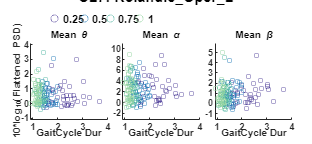



 CL7) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    _______    ________    ________

    (Intercept)                                0.89184    0.34829      2.5606    0.011478
    cond_char_0.5                             -0.10718    0.61616    -0.17394     0.86216
    cond_char_0.75                             -0.3273    0.67375    -0.48579     0.62785
    cond_char_1.0                             -0.79516    0.71093     -1.1185     0.26523
    mean_PeakUpDownVel_mean                    -3.3381     2.9091     -1.1475     0.25309
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                              0.63287         3      0.21096      0.44455    0.72153
    mean_PeakUpDownVel_mean                0.26553         1      0.26553      0.55954    0.45567
    cond_char:mean_PeakUpDownVel_mean        1.034         3      0.34467      0.72632    0.53786
    Error                                   68.334       144      0.47454                        
    Total                                    69.64       151                                     





 CL7) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE       tStat      pValue 
                                              ________    ______    ________    _______

    (Intercept)                                3.2035      1.093      2.9311    0.00393
    cond_char_0.5                             0.77916     1.9336     0.40297    0.68757
    cond_char_0.75                            0.21114     2.1143    0.099866    0.92059
    cond_char_1.0                             -2.8542     2.2309     -1.2793    0.20283
    mean_PeakUpDownVel_mean                   -4.5576      9.129    -0.49925    0.61837
    cond_char_0.5:mean_PeakUpDownVel_mean </

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                                10.86         3        3.62       0.77467    0.50995
    mean_PeakUpDownVel_mean                  2.534         1       2.534       0.54226    0.46269
    cond_char:mean_PeakUpDownVel_mean        12.44         3      4.1466       0.88734    0.44934
    Error                                   672.91       144       4.673                         
    Total                                   687.25       151                                     





 CL7) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    _______    ________    ________

    (Intercept)                                  1.146    0.49252      2.3267    0.021375
    cond_char_0.5                              0.33937    0.87133     0.38948     0.69749
    cond_char_0.75                             0.10179    0.95276     0.10684     0.91507
    cond_char_1.0                             -0.59898     1.0053     -0.5958     0.55224
    mean_PeakUpDownVel_mean                    -1.7205     4.1138    -0.41822     0.67641
    cond_char_0.5:mean_PeakUpDo

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                              0.66948         3      0.22316      0.23516    0.87174
    mean_PeakUpDownVel_mean                0.66916         1      0.66916      0.70515    0.40245
    cond_char:mean_PeakUpDownVel_mean      0.90747         3      0.30249      0.31876     0.8118
    Error                                   136.65       144      0.94896                        
    Total                                   138.23       151                                     



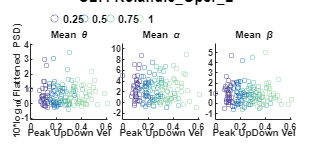



 CL8) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat      pValue 
                                     __________    ________    _________    _______

    (Intercept)                         0.56174     0.55549       1.0113     0.3138
    cond_char_0.5                     0.0058223     0.88226    0.0065994    0.99474
    cond_char_0.75                      0.30981      0.8866      0.34944    0.72733
    cond_char_1.0                       0.08665     0.73712      0.11755    0.90661
    mean_APexc_COV                    0.0039835    0.022313      0.17853    0.85859
    cond_char_0.5:mean_APexc_COV     -0.0014061    0.039787     -0.03534

                                SumOfSquares    DF     MeanSquares        F        pValue 
                                ____________    ___    ___________    _________    _______

    cond_char                      0.17897        3      0.059656      0.047507    0.98622
    mean_APexc_COV               0.0013483        1     0.0013483     0.0010737    0.97391
    cond_char:mean_APexc_COV       0.13696        3      0.045652      0.036355    0.99068
    Error                           160.73      128        1.2557                         
    Total                           160.97      135                                       





 CL8) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue  
                                     __________    ________    ________    _________

    (Intercept)                          3.9028      1.3045      2.9917    0.0033287
    cond_char_0.5                      -0.63925      2.0719    -0.30853      0.75818
    cond_char_0.75                     -0.43348      2.0821    -0.20819      0.83541
    cond_char_1.0                       0.42096      1.7311     0.24318      0.80826
    mean_APexc_COV                   -0.0088821      0.0524     -0.1695      0.86567
    cond_char_0.5:mean_APexc_COV       0.020816    0.093437     0

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                        2.51         3      0.83667      0.12081    0.94771
    mean_APexc_COV                 1.0845         1       1.0845      0.15659    0.69297
    cond_char:mean_APexc_COV       4.7707         3       1.5902      0.22962    0.87563
    Error                          886.48       128       6.9256                        
    Total                          897.85       135                                     





 CL8) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         1.9917     0.56509      3.5246    0.00058905
    cond_char_0.5                     -0.91509     0.89751     -1.0196       0.30985
    cond_char_0.75                     -1.0232     0.90193     -1.1345       0.25871
    cond_char_1.0                     -0.57703     0.74987     -0.7695       0.44301
    mean_APexc_COV                   -0.019161    0.022699    -0.84414       0.40016
    cond_char_0.5:mean_APexc_COV      0.040301    0.040475     0.9

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      2.1791         3      0.72637      0.55894    0.64308
    mean_APexc_COV                0.15652         1      0.15652      0.12044    0.72912
    cond_char:mean_APexc_COV       2.1029         3      0.70096      0.53938    0.65616
    Error                          166.34       128       1.2995                        
    Total                          169.67       135                                     



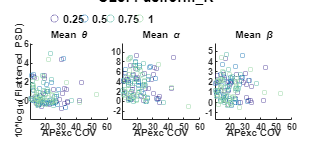



 CL8) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat      pValue 
                                      ________    ______    ________    _______

    (Intercept)                        0.48812    0.6055     0.80614    0.42166
    cond_char_0.5                       0.1599    1.0495     0.15237    0.87914
    cond_char_0.75                     0.49185    1.1357     0.43306     0.6657
    cond_char_1.0                     -0.80188    1.1042    -0.72622    0.46903
    mean_APexc_mean                     2.5589    8.8206      0.2901    0.77221
    cond_char_0.5:mean_APexc_mean      -3.1497     19.18    -0.16421    0.86982
    cond_ch

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.2999         3      0.43331      0.34843    0.79034
    mean_APexc_mean                0.37363         1      0.37363      0.30045    0.58456
    cond_char:mean_APexc_mean       1.4463         3      0.48212      0.38768    0.76206
    Error                           159.18       128       1.2436                        
    Total                           160.97       135                                     





 CL8) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                         2.7953    1.4193      1.9695    0.051054
    cond_char_0.5                     -0.73966    2.4599    -0.30068     0.76414
    cond_char_0.75                     -1.3539    2.6622    -0.50857     0.61193
    cond_char_1.0                      -1.7537    2.5882    -0.67758     0.49926
    mean_APexc_mean                     13.818    20.675     0.66835     0.50511
    cond_char_0.5:mean_APexc_mean       15.662    44.959     0.34836     0.72814
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       3.8586         3      1.2862       0.18824     0.90424
    mean_APexc_mean                 19.084         1      19.084         2.793    0.097121
    cond_char:mean_APexc_mean       5.6551         3       1.885       0.27589     0.84271
    Error                           874.59       128      6.8327                          
    Total                           897.85       135                                      





 CL8) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                         1.2941    0.6182      2.0933    0.038294
    cond_char_0.5                     -0.60833    1.0715    -0.56775      0.5712
    cond_char_0.75                    -0.15334    1.1596    -0.13224       0.895
    cond_char_1.0                     -0.81513    1.1273    -0.72306     0.47096
    mean_APexc_mean                     3.8391    9.0056      0.4263     0.67061
    cond_char_0.5:mean_APexc_mean       12.734    19.583     0.65029     0.51667
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.88179         3      0.29393      0.22674    0.87765
    mean_APexc_mean                  2.048         1        2.048       1.5799    0.21106
    cond_char:mean_APexc_mean      0.99319         3      0.33106      0.25539    0.85738
    Error                           165.93       128       1.2963                        
    Total                           169.67       135                                     



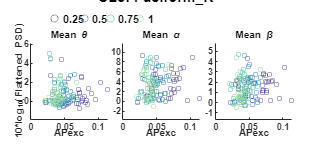



 CL8) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat       pValue 
                                     _________    ________    _________    ________

    (Intercept)                         1.0696     0.45458       2.3529    0.020152
    cond_char_0.5                       -0.466     0.85495     -0.54506     0.58666
    cond_char_0.75                   -0.082854     0.90545    -0.091506     0.92723
    cond_char_1.0                      0.33589      0.9852      0.34093     0.73371
    mean_MLexc_COV                   -0.031099    0.030932      -1.0054     0.31661
    cond_char_0.5:mean_MLexc_COV      0.032341    0.064092       0.5046 

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.66603         3      0.22201      0.17927    0.91029
    mean_MLexc_COV                 1.1521         1       1.1521      0.93031     0.3366
    cond_char:mean_MLexc_COV      0.48355         3      0.16118      0.13015    0.94202
    Error                          158.52       128       1.2384                        
    Total                          160.97       135                                     





 CL8) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat        pValue  
                                     _________    ________    _________    __________

    (Intercept)                         5.2776      1.0544       5.0053    1.8044e-06
    cond_char_0.5                    -0.084423      1.9831    -0.042572       0.96611
    cond_char_0.75                    -0.22117      2.1002     -0.10531        0.9163
    cond_char_1.0                      0.41988      2.2852      0.18374       0.85451
    mean_MLexc_COV                    -0.11863    0.071748      -1.6534        0.1007
    cond_char_0.5:mean_MLexc_COV     -0.017293     0.14866

                                SumOfSquares    DF     MeanSquares       F         pValue 
                                ____________    ___    ___________    ________    ________

    cond_char                     0.40131         3      0.13377      0.020077     0.99612
    mean_MLexc_COV                 34.598         1       34.598        5.1928    0.024336
    cond_char:mean_MLexc_COV      0.34835         3      0.11612      0.017428     0.99685
    Error                          852.83       128       6.6627                          
    Total                          897.85       135                                       





 CL8) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat         pValue  
                                     __________    ________    __________    __________

    (Intercept)                          2.0715     0.46321        4.4721    1.6888e-05
    cond_char_0.5                       -0.4407     0.87119      -0.50586       0.61382
    cond_char_0.75                    -0.035628     0.92265     -0.038615       0.96926
    cond_char_1.0                    -0.0034592      1.0039    -0.0034458       0.99726
    mean_MLexc_COV                    -0.039541     0.03152       -1.2545       0.21195
    cond_char_0.5:mean_MLexc_COV       0.0289

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.35704         3      0.11901      0.092552    0.96403
    mean_MLexc_COV                 2.4989         1       2.4989        1.9433    0.16573
    cond_char:mean_MLexc_COV      0.32452         3      0.10817      0.084123    0.96859
    Error                          164.59       128       1.2859                         
    Total                          169.67       135                                      



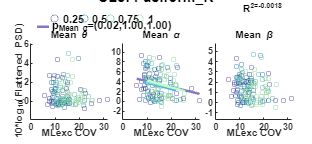



 CL8) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                       -1.1521     0.64853     -1.7765     0.078019
    cond_char_0.5                     0.29017      0.9692     0.29939      0.76512
    cond_char_0.75                     0.4611      1.0666     0.43231      0.66625
    cond_char_1.0                     0.79416      1.0394     0.76406      0.44624
    mean_MLexc_mean                    15.493      5.3412      2.9007    0.0043846
    cond_char_0.5:mean_MLexc_mean     0.46811      9.2196    0.050774      0.9

                                 SumOfSquares    DF     MeanSquares       F         pValue  
                                 ____________    ___    ___________    ________    _________

    cond_char                      0.67758         3      0.22586       0.20414      0.89337
    mean_MLexc_mean                 12.458         1       12.458         11.26    0.0010425
    cond_char:mean_MLexc_mean      0.16079         3     0.053596      0.048441      0.98582
    Error                           141.62       128       1.1064                           
    Total                           160.97       135                                        





 CL8) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE        tStat        pValue  
                                      _________    ______    __________    _________

    (Intercept)                        -0.87258    1.4761      -0.59113      0.55547
    cond_char_0.5                       0.96958     2.206       0.43953      0.66102
    cond_char_0.75                    -0.016419    2.4277    -0.0067633      0.99461
    cond_char_1.0                      -0.91503    2.3658      -0.38678      0.69956
    mean_MLexc_mean                      39.167    12.157        3.2217    0.0016161
    cond_char_0.5:mean_MLexc_mean       -2.4711    20.985      -

                                 SumOfSquares    DF     MeanSquares       F         pValue  
                                 ____________    ___    ___________    _______    __________

    cond_char                       3.3773         3      1.1258       0.19641       0.89868
    mean_MLexc_mean                 133.98         1      133.98        23.375    3.7535e-06
    cond_char:mean_MLexc_mean       16.642         3      5.5475       0.96784       0.41014
    Error                           733.67       128      5.7318                            
    Total                           897.85       135                                        





 CL8) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.92345    0.69431        1.33    0.18588
    cond_char_0.5                     -0.26806     1.0376    -0.25835    0.79656
    cond_char_0.75                    -0.31369     1.1419     -0.2747    0.78399
    cond_char_1.0                     -0.78315     1.1128    -0.70378    0.48285
    mean_MLexc_mean                     5.3221     5.7183     0.93071    0.35376
    cond_char_0.5:mean_MLexc_mean        3.768     9.8704     0.38175    0.70328
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       0.6306         3       0.2102      0.16576     0.91928
    mean_MLexc_mean                 5.6733         1       5.6733       4.4738    0.036357
    cond_char:mean_MLexc_mean       1.3211         3      0.44036      0.34725     0.79119
    Error                           162.32       128       1.2681                         
    Total                           169.67       135                                      



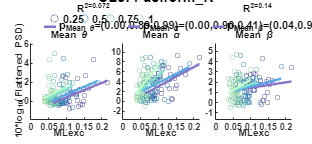



 CL8) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                     0.32053    0.79563     0.40286    0.68772
    cond_char_0.5                  -0.29283     1.5934    -0.18377    0.85448
    cond_char_0.75                 -0.49967     2.0779    -0.24047    0.81035
    cond_char_1.0                    -1.599     2.3352    -0.68473    0.49475
    mean_StepDur                    0.28108    0.64944     0.43281    0.66588
    cond_char_0.5:mean_StepDur      0.44416     1.7982       0.247     0.8053
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                   0.61415         3      0.20472      0.16463    0.92002
    mean_StepDur                 1.5595         1       1.5595       1.2541    0.26486
    cond_char:mean_StepDur      0.96572         3      0.32191      0.25887    0.85489
    Error                        159.17       128       1.2435                        
    Total                        160.97       135                                     





 CL8) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat       pValue 
                                   ________    ______    ________    ________

    (Intercept)                      3.0978    1.8598      1.6656    0.098232
    cond_char_0.5                   0.75302    3.7247     0.20217     0.84011
    cond_char_0.75                  -2.5334    4.8572    -0.52158     0.60286
    cond_char_1.0                   -8.8315    5.4587     -1.6179     0.10815
    mean_StepDur                    0.50248    1.5181     0.33099     0.74119
    cond_char_0.5:mean_StepDur     -0.93039    4.2034    -0.22134     0.82518
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares      F        pValue 
                              ____________    ___    ___________    ______    ________

    cond_char                    20.484         3      6.8279       1.0049     0.39296
    mean_StepDur                 19.016         1      19.016       2.7986    0.096787
    cond_char:mean_StepDur       21.539         3      7.1796       1.0567     0.37002
    Error                        869.71       128      6.7946                         
    Total                        897.85       135                                     





 CL8) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                      1.0118     0.8153       1.241    0.21686
    cond_char_0.5                   0.56988     1.6328     0.34902    0.72765
    cond_char_0.75                   1.1639     2.1293     0.54661     0.5856
    cond_char_1.0                   -1.1772     2.3929    -0.49195     0.6236
    mean_StepDur                    0.44765    0.66549     0.67266    0.50238
    cond_char_0.5:mean_StepDur     -0.54926     1.8427    -0.29808    0.76613
    cond_char_0.75:mean_StepDur

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                   0.96039         3      0.32013      0.24518    0.86464
    mean_StepDur                0.14617         1      0.14617      0.11195    0.73848
    cond_char:mean_StepDur      0.85768         3      0.28589      0.21895     0.8831
    Error                        167.13       128       1.3057                        
    Total                        169.67       135                                     



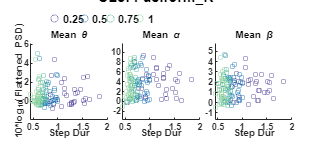



 CL8) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue 
                                     __________    ________    __________    _______

    (Intercept)                          1.0985      0.9694        1.1332    0.25925
    cond_char_0.5                       -1.4549      1.4678      -0.99117    0.32347
    cond_char_0.75                   -0.0060596      1.2365    -0.0049007     0.9961
    cond_char_1.0                     -0.093876      1.1708      -0.08018    0.93622
    mean_UDexc_COV                    -0.023385    0.050088      -0.46689    0.64138
    cond_char_0.5:mean_UDexc_COV       0.092503    0.091789      

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                       1.761         3      0.58701       0.47288    0.70171
    mean_UDexc_COV                0.07499         1      0.07499      0.060411    0.80624
    cond_char:mean_UDexc_COV       1.7932         3      0.59774       0.48153     0.6957
    Error                          158.89       128       1.2413                         
    Total                          160.97       135                                      





 CL8) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                        7.2992     2.2348      3.2662    0.001399
    cond_char_0.5                     -3.2979     3.3838    -0.97461     0.33159
    cond_char_0.75                    -2.9539     2.8504     -1.0363     0.30203
    cond_char_1.0                    -0.97675     2.6991    -0.36188     0.71804
    mean_UDexc_COV                   -0.18993    0.11547     -1.6449     0.10245
    cond_char_0.5:mean_UDexc_COV      0.15454     0.2116     0.73035     0.46651
    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      11.245         3      3.7483       0.56819     0.63696
    mean_UDexc_COV                 30.623         1      30.623        4.6419    0.033073
    cond_char:mean_UDexc_COV       14.764         3      4.9214         0.746     0.52659
    Error                          844.42       128       6.597                          
    Total                          897.85       135                                      





 CL8) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         2.6629      0.9837       2.707    0.0077158
    cond_char_0.5                      -1.3736      1.4895    -0.92222      0.35815
    cond_char_0.75                     -2.0683      1.2547     -1.6484      0.10171
    cond_char_1.0                      -0.6676      1.1881    -0.56191      0.57516
    mean_UDexc_COV                   -0.058961    0.050827       -1.16      0.24819
    cond_char_0.5:mean_UDexc_COV      0.073812    0.093144     0.79245   

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      4.1694         3       1.3898       1.0873    0.35701
    mean_UDexc_COV                0.16138         1      0.16138      0.12625    0.72294
    cond_char:mean_UDexc_COV       4.3414         3       1.4471       1.1321    0.33868
    Error                          163.61       128       1.2782                        
    Total                          169.67       135                                     



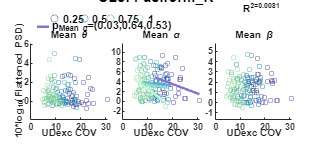



 CL8) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat      pValue 
                                      ________    ______    ________    _______

    (Intercept)                         1.1129    0.6723      1.6554     0.1003
    cond_char_0.5                      0.41414    1.3239     0.31282    0.75492
    cond_char_0.75                    -0.74781    1.4822    -0.50451    0.61477
    cond_char_1.0                      -1.4552    1.4303     -1.0174    0.31088
    mean_UDexc_mean                    -30.305    42.644    -0.71065     0.4786
    cond_char_0.5:mean_UDexc_mean      -16.265    71.723    -0.22678    0.82096
    cond_ch

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        1.896         3      0.63199      0.51021    0.67595
    mean_UDexc_mean                0.17318         1      0.17318      0.13981    0.70909
    cond_char:mean_UDexc_mean       2.3194         3      0.77315      0.62417    0.60064
    Error                           158.55       128       1.2387                        
    Total                           160.97       135                                     





 CL8) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue  
                                      ________    ______    ________    _________

    (Intercept)                        4.1552     1.5846      2.6223    0.0097931
    cond_char_0.5                     0.93244     3.1203     0.29883      0.76555
    cond_char_0.75                    -3.0232     3.4936    -0.86535      0.38847
    cond_char_1.0                     -3.7879     3.3712     -1.1236      0.26328
    mean_UDexc_mean                   -30.422     100.51    -0.30268      0.76263
    cond_char_0.5:mean_UDexc_mean      -50.91     169.05    -0.30116      0.76378
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       15.058         3       5.0194       0.72944    0.53624
    mean_UDexc_mean                0.47065         1      0.47065      0.068397    0.79411
    cond_char:mean_UDexc_mean       11.416         3       3.8053         0.553    0.64704
    Error                           880.79       128       6.8811                         
    Total                           897.85       135                                      





 CL8) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue  
                                      ________    ______    ________    _________

    (Intercept)                         2.071     0.6752      3.0672    0.0026372
    cond_char_0.5                      1.1942     1.3296     0.89819      0.37077
    cond_char_0.75                    0.97144     1.4887     0.65256      0.51521
    cond_char_1.0                      1.0917     1.4365        0.76      0.44865
    mean_UDexc_mean                   -34.851     42.828    -0.81374       0.4173
    cond_char_0.5:mean_UDexc_mean     -55.744     72.033    -0.77387      0.44043
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       1.5726         3      0.52421      0.41956     0.73927
    mean_UDexc_mean                 8.0589         1       8.0589       6.4501    0.012291
    cond_char:mean_UDexc_mean      0.76769         3       0.2559      0.20481     0.89291
    Error                           159.93       128       1.2494                         
    Total                           169.67       135                                      



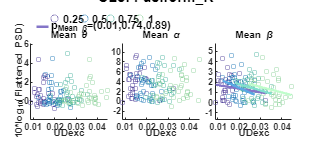



 CL8) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                       0.27102    0.76207     0.35564     0.7227
    cond_char_0.5                    -0.54685     1.5534    -0.35203     0.7254
    cond_char_0.75                   -0.93855     2.1178    -0.44318    0.65838
    cond_char_1.0                     -1.9144     2.3846    -0.80281    0.42357
    mean_StanceDur                    0.22021    0.42339     0.52011    0.60388
    cond_char_0.5:mean_StanceDur      0.60123      1.301     0.46212    0.64478
    cond_cha

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.98763         3      0.32921      0.26654    0.84941
    mean_StanceDur                   2.52         1         2.52       2.0403    0.15562
    cond_char:mean_StanceDur       1.6845         3      0.56151      0.45461    0.71449
    Error                           158.1       128       1.2351                        
    Total                          160.97       135                                     





 CL8) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                        3.3299     1.7913       1.859    0.065327
    cond_char_0.5                     0.46639     3.6513     0.12773     0.89856
    cond_char_0.75                     -2.976     4.9778    -0.59786     0.55099
    cond_char_1.0                     -8.5426      5.605     -1.5241     0.12995
    mean_StanceDur                     0.2097    0.99518     0.21071     0.83345
    cond_char_0.5:mean_StanceDur     -0.47992      3.058    -0.15694     0.87554
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      18.443         3      6.1477       0.90089    0.44279
    mean_StanceDur                 17.098         1      17.098        2.5056    0.11591
    cond_char:mean_StanceDur       19.215         3       6.405        0.9386    0.42414
    Error                          873.47       128       6.824                         
    Total                          897.85       135                                     





 CL8) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                        1.0992    0.78418      1.4017    0.16342
    cond_char_0.5                     0.61361     1.5985     0.38387    0.70171
    cond_char_0.75                     1.6101     2.1792     0.73883    0.46136
    cond_char_1.0                    -0.32001     2.4538    -0.13042    0.89644
    mean_StanceDur                    0.25532    0.43567     0.58604    0.55888
    cond_char_0.5:mean_StanceDur     -0.45172     1.3388    -0.33742    0.73635
    cond_char

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.88583        3      0.29528       0.22578    0.87833
    mean_StanceDur                0.040223        1     0.040223      0.030755    0.86106
    cond_char:mean_StanceDur       0.84844        3      0.28281       0.21625    0.88499
    Error                            167.4      128       1.3078                         
    Total                           169.67      135                                      



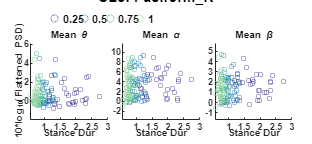



 CL8) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                          0.32261    0.79446     0.40607    0.68537
    cond_char_0.5                       -0.29665     1.5902    -0.18655    0.85231
    cond_char_0.75                      -0.52062      2.083    -0.24993    0.80304
    cond_char_1.0                        -1.6844     2.3253    -0.72437    0.47016
    mean_GaitCycleDur                    0.13953    0.32391     0.43078    0.66736
    cond_char_0.5:mean_GaitCycleDur      0.22401    0.89675     0.24981    0

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                        0.68436         3      0.22812      0.18357     0.9074
    mean_GaitCycleDur                 1.6603         1       1.6603       1.3361    0.24988
    cond_char:mean_GaitCycleDur       1.0569         3       0.3523      0.28351    0.83723
    Error                             159.06       128       1.2427                        
    Total                             160.97       135                                     





 CL8) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                           3.1195     1.8579      1.6791    0.095578
    cond_char_0.5                        0.72816     3.7187     0.19581     0.84507
    cond_char_0.75                       -2.5632     4.8713    -0.52619     0.59967
    cond_char_1.0                        -8.7904     5.4378     -1.6165     0.10844
    mean_GaitCycleDur                    0.24187    0.75748      0.3193     0.75002
    cond_char_0.5:mean_GaitCycleDur     -0.45383     2.0971    -0.216

                                   SumOfSquares    DF     MeanSquares      F       pValue 
                                   ____________    ___    ___________    ______    _______

    cond_char                         20.442         3      6.8139       1.0026    0.39399
    mean_GaitCycleDur                 18.858         1      18.858       2.7749     0.0982
    cond_char:mean_GaitCycleDur       21.468         3      7.1561        1.053    0.37161
    Error                             869.88       128      6.7959                        
    Total                             897.85       135                                    





 CL8) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                            1.016    0.81437      1.2476    0.21447
    cond_char_0.5                        0.55973       1.63     0.34339    0.73187
    cond_char_0.75                        1.1805     2.1352     0.55285    0.58133
    cond_char_1.0                        -1.1757     2.3835    -0.49326    0.62267
    mean_GaitCycleDur                    0.22186    0.33203     0.66821     0.5052
    cond_char_0.5:mean_GaitCycleDur     -0.26898    0.91921    -0.29262    0.

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         0.9672         3       0.3224      0.24692    0.86341
    mean_GaitCycleDur                 0.1403         1       0.1403      0.10745     0.7436
    cond_char:mean_GaitCycleDur      0.86482         3      0.28827      0.22078    0.88182
    Error                             167.13       128       1.3057                        
    Total                             169.67       135                                     



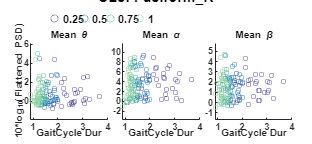



 CL8) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue 
                                              ________    _______    ________    _______

    (Intercept)                                 1.3678    0.96428      1.4184    0.15849
    cond_char_0.5                             -0.67578     1.6052      -0.421    0.67446
    cond_char_0.75                            -0.56812     1.6843    -0.33731    0.73644
    cond_char_1.0                             -0.55567     1.6641    -0.33391    0.73899
    mean_PeakUpDownVel_mean                    -6.5228     8.6455    -0.75447    0.45195
    cond_char_0.5:mean_PeakUpDownVel_

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                              0.30441         3      0.10147      0.081105    0.97019
    mean_PeakUpDownVel_mean                0.47214         1      0.47214       0.37739     0.5401
    cond_char:mean_PeakUpDownVel_mean       0.5805         3       0.1935       0.15467    0.92652
    Error                                   160.14       128       1.2511                         
    Total                                   160.97       135                                      





 CL8) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE       tStat       pValue 
                                              ________    ______    ________    ________

    (Intercept)                                 5.1896    2.2718      2.2843    0.023999
    cond_char_0.5                             -0.69323    3.7817    -0.18331     0.85484
    cond_char_0.75                             -2.0315    3.9682    -0.51196     0.60956
    cond_char_1.0                             -0.50666    3.9207    -0.12923     0.89738
    mean_PeakUpDownVel_mean                    -13.671    20.369    -0.67115     0.50334
    cond_char_0.5:mean_PeakUpDownVel_

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               1.8357         3      0.61191      0.088116    0.96645
    mean_PeakUpDownVel_mean                  3.784         1        3.784        0.5449    0.46176
    cond_char:mean_PeakUpDownVel_mean        2.868         3      0.95599       0.13766    0.93735
    Error                                   888.88       128       6.9444                         
    Total                                   897.85       135                                      





 CL8) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue  
                                              ________    _______    _______    _________

    (Intercept)                                2.8213     0.95474      2.955    0.0037229
    cond_char_0.5                               0.509      1.5893    0.32027      0.74929
    cond_char_0.75                            0.22779      1.6676     0.1366      0.89156
    cond_char_1.0                              1.1145      1.6477    0.67639      0.50001
    mean_PeakUpDownVel_mean                   -11.684        8.56    -1.3649      0.17467
    cond_char_0.5:mean_PeakUpDo

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                              0.58897         3      0.19632      0.16007     0.92301
    mean_PeakUpDownVel_mean                 9.2702         1       9.2702       7.5586    0.006837
    cond_char:mean_PeakUpDownVel_mean      0.62887         3      0.20962      0.17092     0.91587
    Error                                   156.99       128       1.2265                         
    Total                                   169.67       135                                      



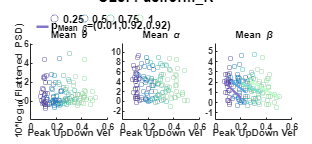



 CL9) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue 
                                     __________    ________    ________    ________

    (Intercept)                         0.33875      0.2899      1.1685     0.24378
    cond_char_0.5                      0.078136     0.46757     0.16711     0.86743
    cond_char_0.75                      0.83206     0.48889       1.702    0.090081
    cond_char_1.0                        0.8035     0.44619      1.8008    0.073011
    mean_APexc_COV                    0.0043375    0.011906      0.3643     0.71596
    cond_char_0.5:mean_APexc_COV     -0.0029149    0.021097    -0.13817 

                                SumOfSquares    DF     MeanSquares      F       pValue 
                                ____________    ___    ___________    ______    _______

    cond_char                        3.36         3         1.12      1.7574    0.15603
    mean_APexc_COV                  1.641         1        1.641      2.5749    0.10991
    cond_char:mean_APexc_COV       2.6893         3      0.89645      1.4066    0.24153
    Error                          150.41       236      0.63731                       
    Total                          155.17       243                                    





 CL9) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    _______    ________

    (Intercept)                        0.68908     0.81269     0.8479     0.39735
    cond_char_0.5                       1.6806      1.3108     1.2822     0.20104
    cond_char_0.75                      1.8111      1.3705     1.3214     0.18763
    cond_char_1.0                       1.3513      1.2508     1.0803      0.2811
    mean_APexc_COV                    0.060341    0.033378     1.8078    0.071907
    cond_char_0.5:mean_APexc_COV     -0.084892    0.059142    -1.4354      0.1525
    

                                SumOfSquares    DF     MeanSquares        F         pValue 
                                ____________    ___    ___________    __________    _______

    cond_char                       13.128        3        4.3759        0.87367    0.45538
    mean_APexc_COV               0.0031143        1     0.0031143     0.00062179    0.98013
    cond_char:mean_APexc_COV        17.222        3        5.7406         1.1461    0.33117
    Error                             1182      236        5.0086                          
    Total                           1202.9      243                                        





 CL9) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    ________    _______

    (Intercept)                         1.8624     0.72858      2.5562    0.01121
    cond_char_0.5                     -0.22779      1.1751    -0.19385    0.84646
    cond_char_0.75                    -0.32087      1.2287    -0.26114    0.79421
    cond_char_1.0                     -0.69676      1.1214    -0.62134    0.53497
    mean_APexc_COV                    0.039769    0.029923       1.329    0.18512
    cond_char_0.5:mean_APexc_COV     0.0099966    0.053022     0.18854    0.85062
    <

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                       1.576         3      0.52534       0.1305     0.94189
    mean_APexc_COV                 26.784         1       26.784       6.6536    0.010502
    cond_char:mean_APexc_COV       1.4906         3      0.49686      0.12343     0.94621
    Error                          950.03       236       4.0255                         
    Total                           980.6       243                                      



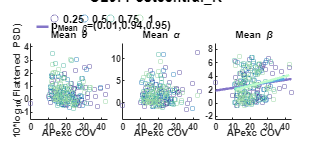



 CL9) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                       -0.017741    0.30527    -0.058117     0.9537
    cond_char_0.5                       0.66917    0.49063       1.3639     0.1739
    cond_char_0.75                      0.24919    0.56195      0.44344    0.65785
    cond_char_1.0                      0.074504    0.55949      0.13316    0.89418
    mean_APexc_mean                      7.4061     4.6779       1.5832    0.11471
    cond_char_0.5:mean_APexc_mean       -11.576     8.8411      -1.3094    0.1

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.2701         3      0.42335      0.66206    0.57614
    mean_APexc_mean                 1.2052         1       1.2052       1.8848     0.1711
    cond_char:mean_APexc_mean       1.5111         3      0.50369       0.7877    0.50182
    Error                           150.91       236      0.63945                        
    Total                           155.17       243                                     





 CL9) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue  
                                      ________    _______    _______    _________

    (Intercept)                       0.10657     0.84124    0.12668       0.8993
    cond_char_0.5                      2.3868       1.352     1.7653     0.078806
    cond_char_0.75                     4.0833      1.5486     2.6368     0.008926
    cond_char_1.0                      3.4239      1.5418     2.2207     0.027324
    mean_APexc_mean                    31.838      12.891     2.4698     0.014228
    cond_char_0.5:mean_APexc_mean     -44.409      24.364    -1.8228     0.069606
   

                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    cond_char                       46.242         3      15.414       3.1742    0.024923
    mean_APexc_mean                 11.443         1      11.443       2.3564     0.12611
    cond_char:mean_APexc_mean        53.52         3       17.84       3.6737    0.012892
    Error                             1146       236      4.8561                         
    Total                           1202.9       243                                     





 CL9) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    ________    _________

    (Intercept)                         2.548     0.76492       3.331    0.0010041
    cond_char_0.5                     0.95703      1.2294     0.77847      0.43707
    cond_char_0.75                     2.4824      1.4081       1.763       0.0792
    cond_char_1.0                      1.7842      1.4019      1.2726       0.2044
    mean_APexc_mean                    3.5871      11.722     0.30603      0.75985
    cond_char_0.5:mean_APexc_mean      -21.09      22.153    -0.95199      0.34

                                 SumOfSquares    DF     MeanSquares      F        pValue 
                                 ____________    ___    ___________    ______    ________

    cond_char                       14.956         3      4.9854       1.2417     0.29527
    mean_APexc_mean                 26.364         1      26.364       6.5665    0.011013
    cond_char:mean_APexc_mean       23.957         3      7.9857        1.989     0.11631
    Error                           947.52       236      4.0149                         
    Total                            980.6       243                                     



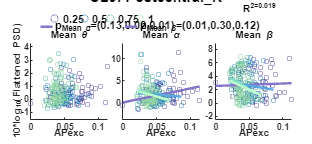



 CL9) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat      pValue 
                                     __________    ________    _________    _______

    (Intercept)                         0.34555     0.24519       1.4093    0.16006
    cond_char_0.5                    -0.0085817     0.37979    -0.022596    0.98199
    cond_char_0.75                     -0.12335     0.41524     -0.29705    0.76669
    cond_char_1.0                       0.18283     0.45233      0.40419    0.68644
    mean_MLexc_COV                    0.0073876    0.017863      0.41358    0.67956
    cond_char_0.5:mean_MLexc_COV      0.0011092    0.027718     0.040018

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.23806         3     0.079353      0.12254    0.94675
    mean_MLexc_COV                0.74085         1      0.74085        1.144     0.2859
    cond_char:mean_MLexc_COV      0.41166         3      0.13722      0.21189    0.88811
    Error                          152.83       236      0.64759                        
    Total                          155.17       243                                     





 CL9) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat      pValue 
                                     ________    ________    _______    ________

    (Intercept)                       0.91215     0.67258     1.3562     0.17633
    cond_char_0.5                      2.1967      1.0418     2.1086    0.036037
    cond_char_0.75                     2.5389       1.139      2.229    0.026755
    cond_char_1.0                      2.0206      1.2408     1.6285     0.10475
    mean_MLexc_COV                   0.092468    0.048998     1.8872    0.060363
    cond_char_0.5:mean_MLexc_COV     -0.18908    0.076033    -2.4868    0.013582
    

                                SumOfSquares    DF     MeanSquares      F        pValue 
                                ____________    ___    ___________    ______    ________

    cond_char                      35.198         3      11.733       2.4079    0.067859
    mean_MLexc_COV                 11.159         1      11.159         2.29     0.13154
    cond_char:mean_MLexc_COV       46.274         3      15.425       3.1656    0.025208
    Error                          1149.9       236      4.8726                         
    Total                          1202.9       243                                     





 CL9) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    _______    __________

    (Intercept)                         2.2865     0.61442     3.7214    0.00024771
    cond_char_0.5                      0.93058      0.9517    0.97781       0.32917
    cond_char_0.75                      1.5489      1.0405     1.4886       0.13793
    cond_char_1.0                       1.1278      1.1335    0.99498       0.32077
    mean_MLexc_COV                    0.038696    0.044761    0.86451       0.38819
    cond_char_0.5:mean_MLexc_COV     -0.083707    0.069459    -1.2051    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      10.625         3      3.5417       0.87095    0.45679
    mean_MLexc_COV                 7.6028         1      7.6028        1.8696    0.17282
    cond_char:mean_MLexc_COV       14.371         3      4.7903         1.178    0.31879
    Error                          959.67       236      4.0664                         
    Total                           980.6       243                                     



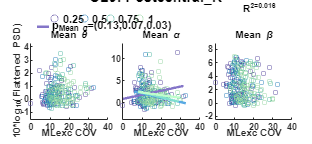



 CL9) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                       Estimate       SE         tStat      pValue 
                                      __________    _______    _________    _______

    (Intercept)                       -0.0075866    0.35021    -0.021663    0.98273
    cond_char_0.5                        0.37997    0.50624      0.75057    0.45366
    cond_char_0.75                       0.64145    0.53657       1.1955     0.2331
    cond_char_1.0                        0.43635    0.56746      0.76895    0.44269
    mean_MLexc_mean                       3.7344     2.8079       1.3299    0.18482
    cond_char_0.5:mean_MLexc_mean        -2.9552     4.6685       -0.63

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.0027         3      0.33423      0.51665    0.67121
    mean_MLexc_mean                0.24837         1      0.24837      0.38392    0.53611
    cond_char:mean_MLexc_mean      0.45445         3      0.15148      0.23416    0.87251
    Error                           152.67       236      0.64692                        
    Total                           155.17       243                                     





 CL9) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat      pValue 
                                      ________    _______    _________    _______

    (Intercept)                       0.91607     0.97827      0.93642    0.35001
    cond_char_0.5                     0.64406      1.4141      0.45545    0.64921
    cond_char_0.75                    0.38491      1.4988       0.2568    0.79755
    cond_char_1.0                     0.57108      1.5851      0.36027    0.71897
    mean_MLexc_mean                    9.6291      7.8436       1.2276    0.22081
    cond_char_0.5:mean_MLexc_mean     -6.3019      13.041     -0.48324    0.62937
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       1.2173         3      0.40578      0.080386    0.97062
    mean_MLexc_mean                 4.8198         1       4.8198       0.95481     0.3295
    cond_char:mean_MLexc_mean       1.1887         3      0.39623      0.078493     0.9716
    Error                           1191.3       236       5.0479                         
    Total                           1202.9       243                                      





 CL9) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                         2.7429    0.88641      3.0944    0.00221
    cond_char_0.5                      0.20958     1.2813     0.16356    0.87022
    cond_char_0.75                    0.085132     1.3581    0.062684    0.95007
    cond_char_1.0                      -0.1591     1.4363    -0.11077     0.9119
    mean_MLexc_mean                    0.21465     7.1072    0.030202    0.97593
    cond_char_0.5:mean_MLexc_mean      -3.5233     11.817    -0.29817    0.76584
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.2831         3     0.094366      0.022769    0.99533
    mean_MLexc_mean                0.28363         1      0.28363      0.068435    0.79386
    cond_char:mean_MLexc_mean      0.42851         3      0.14284      0.034465     0.9914
    Error                           978.09       236       4.1445                         
    Total                            980.6       243                                      



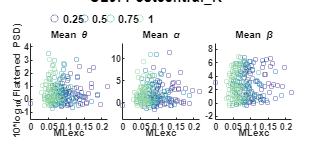



 CL9) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                    -0.14249    0.43064    -0.33088    0.74103
    cond_char_0.5                   0.53494    0.78426     0.68209    0.49585
    cond_char_0.75                 -0.41542     1.0204    -0.40712    0.68429
    cond_char_1.0                   -1.4966     1.2784     -1.1707     0.2429
    mean_StepDur                    0.50368    0.36331      1.3864    0.16694
    cond_char_0.5:mean_StepDur      -0.4372    0.88682      -0.493    0.62247
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                    1.5246         3      0.50821      0.80198     0.49386
    mean_StepDur                  3.401         1        3.401       5.3669    0.021379
    cond_char:mean_StepDur       2.2734         3       0.7578       1.1959     0.31204
    Error                        149.55       236      0.63369                         
    Total                        155.17       243                                      





 CL9) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    ______    _________    _______

    (Intercept)                      1.7261    1.2184       1.4167    0.15789
    cond_char_0.5                   0.10082     2.219     0.045434     0.9638
    cond_char_0.75                   1.9681    2.8871      0.68171    0.49609
    cond_char_1.0                    1.9553    3.6169      0.54061    0.58929
    mean_StepDur                    0.29331    1.0279      0.28534    0.77564
    cond_char_0.5:mean_StepDur     -0.23574    2.5091    -0.093952    0.92523
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    3.5577         3      1.1859       0.23377    0.87279
    mean_StepDur                 2.6735         1      2.6735       0.52702    0.46858
    cond_char:mean_StepDur       4.2526         3      1.4175       0.27943    0.84022
    Error                        1197.2       236      5.0729                         
    Total                        1202.9       243                                     





 CL9) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat        pValue  
                                   ________    ______    ________    __________

    (Intercept)                      3.6266    1.0876      3.3344    0.00099273
    cond_char_0.5                   0.40381    1.9808     0.20386       0.83864
    cond_char_0.75                   2.3863    2.5772     0.92596       0.35541
    cond_char_1.0                     3.808    3.2287      1.1794       0.23942
    mean_StepDur                    -0.7451    0.9176    -0.81201       0.41761
    cond_char_0.5:mean_StepDur     -0.99045    2.2398     -0.4422       0.65875
    cond_char_0

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                    8.1268         3      2.7089       0.67014     0.57113
    mean_StepDur                 23.428         1      23.428        5.7956    0.016835
    cond_char:mean_StepDur       14.035         3      4.6784        1.1574     0.32677
    Error                        953.99       236      4.0423                          
    Total                         980.6       243                                      



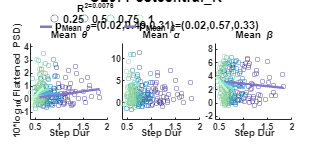



 CL9) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat      pValue 
                                     __________    ________    ________    _______

    (Intercept)                         0.48898     0.38308      1.2764    0.20306
    cond_char_0.5                      -0.66234      0.6603     -1.0031    0.31685
    cond_char_0.75                      0.05233     0.59236    0.088342    0.92968
    cond_char_1.0                       0.62473     0.55184      1.1321    0.25874
    mean_UDexc_COV                   -0.0025781    0.018511    -0.13928    0.88935
    cond_char_0.5:mean_UDexc_COV        0.04598    0.041386       1.111    0.26

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                       2.4637        3      0.82124        1.2771    0.28289
    mean_UDexc_COV                0.046694        1     0.046694      0.072613     0.7878
    cond_char:mean_UDexc_COV        2.1659        3      0.72195        1.1227    0.34056
    Error                           151.76      236      0.64305                         
    Total                           155.17      243                                      





 CL9) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue 
                                     __________    ________    ________    ________

    (Intercept)                          2.2632      1.0545      2.1463    0.032872
    cond_char_0.5                        3.0268      1.8176      1.6653    0.097181
    cond_char_0.75                       1.0932      1.6306     0.67042     0.50324
    cond_char_1.0                        1.6415       1.519      1.0806     0.28097
    mean_UDexc_COV                   -0.0099967    0.050954    -0.19619     0.84463
    cond_char_0.5:mean_UDexc_COV       -0.22959     0.11392     -2.0153 

                                SumOfSquares    DF     MeanSquares      F        pValue  
                                ____________    ___    ___________    ______    _________

    cond_char                      14.555         3      4.8516       0.9957      0.39556
    mean_UDexc_COV                 45.435         1      45.435       9.3246    0.0025202
    cond_char:mean_UDexc_COV       30.144         3      10.048       2.0622      0.10593
    Error                          1149.9       236      4.8726                          
    Total                          1202.9       243                                      





 CL9) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat       pValue  
                                     _________    ________    _________    _________

    (Intercept)                         2.5601     0.96991       2.6396    0.0088547
    cond_char_0.5                       1.4795      1.6718      0.88498      0.37707
    cond_char_0.75                     0.67293      1.4998      0.44869      0.65407
    cond_char_1.0                    0.0029305      1.3972    0.0020974      0.99833
    mean_UDexc_COV                    0.010451    0.046867      0.22299      0.82373
    cond_char_0.5:mean_UDexc_COV      -0.10849     0.10478      -1

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      4.1682         3      1.3894       0.33706    0.79856
    mean_UDexc_COV                 2.5481         1      2.5481       0.61814    0.43253
    cond_char:mean_UDexc_COV       5.1542         3      1.7181       0.41679    0.74111
    Error                          972.84       236      4.1222                         
    Total                           980.6       243                                     



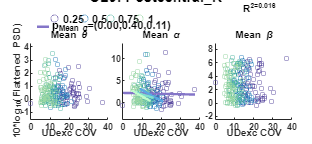



 CL9) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.41974    0.33603      1.2491    0.21286
    cond_char_0.5                      0.36888    0.58541     0.63012    0.52922
    cond_char_0.75                      0.4632    0.66064     0.70114    0.48391
    cond_char_1.0                     0.029302     0.6636    0.044156    0.96482
    mean_UDexc_mean                     1.2046     21.605    0.055754    0.95559
    cond_char_0.5:mean_UDexc_mean      -18.335     31.835    -0.57594    0.56521
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.48925         3      0.16308      0.25095    0.86061
    mean_UDexc_mean                0.20519         1      0.20519      0.31574    0.57471
    cond_char:mean_UDexc_mean       0.4607         3      0.15357      0.23631      0.871
    Error                           153.37       236      0.64986                        
    Total                           155.17       243                                     





 CL9) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    _______    ________

    (Intercept)                        0.5157     0.93373     0.5523     0.58127
    cond_char_0.5                      1.0363      1.6267    0.63706      0.5247
    cond_char_0.75                     1.0666      1.8357    0.58102     0.56178
    cond_char_1.0                     0.53166       1.844    0.28832     0.77335
    mean_UDexc_mean                     104.6      60.034     1.7423    0.082754
    cond_char_0.5:mean_UDexc_mean     -88.563       88.46    -1.0012     0.31777
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        2.897         3      0.96565      0.19245    0.90148
    mean_UDexc_mean                 9.3547         1       9.3547       1.8643    0.17342
    cond_char:mean_UDexc_mean       8.2968         3       2.7656      0.55117    0.64783
    Error                           1184.2       236       5.0177                        
    Total                           1202.9       243                                     





 CL9) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat        pValue  
                                      ________    _______    _________    __________

    (Intercept)                         3.1477    0.84781       3.7128    0.00025583
    cond_char_0.5                     -0.40404      1.477     -0.27356       0.78466
    cond_char_0.75                      0.3455     1.6668      0.20728       0.83597
    cond_char_1.0                     -0.54828     1.6743     -0.32747        0.7436
    mean_UDexc_mean                    -25.621      54.51     -0.47003       0.63877
    cond_char_0.5:mean_UDexc_mean       20.508      80.32      0.

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       1.1103         3      0.37009      0.089464    0.96578
    mean_UDexc_mean                 1.6208         1       1.6208       0.39181    0.53195
    cond_char:mean_UDexc_mean       1.1506         3      0.38355      0.092718    0.96401
    Error                           976.27       236       4.1367                         
    Total                            980.6       243                                      



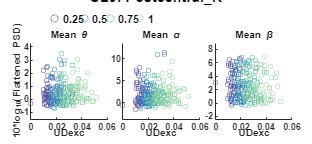



 CL9) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE        tStat      pValue 
                                     _________    _______    ________    _______

    (Intercept)                      -0.051452    0.40631    -0.12663    0.89934
    cond_char_0.5                      0.49591    0.76935     0.64459    0.51982
    cond_char_0.75                    -0.30826     1.0505    -0.29343    0.76945
    cond_char_1.0                      -1.4503      1.317     -1.1012    0.27192
    mean_StanceDur                     0.28932    0.23265      1.2436    0.21488
    cond_char_0.5:mean_StanceDur       -0.2882    0.64802    -0.44474    0.65692
    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      1.2866         3      0.42887      0.67229     0.56981
    mean_StanceDur                  2.495         1        2.495       3.9111    0.049131
    cond_char:mean_StanceDur       1.8985         3      0.63284      0.99203     0.39725
    Error                          150.55       236      0.63793                         
    Total                          155.17       243                                      





 CL9) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                        1.4786     1.1465      1.2897     0.1984
    cond_char_0.5                    -0.32674     2.1708    -0.15052    0.88049
    cond_char_0.75                    0.97418     2.9643     0.32864    0.74272
    cond_char_1.0                    -0.54366     3.7162     -0.1463    0.88381
    mean_StanceDur                    0.34627    0.65645     0.52749    0.59835
    cond_char_0.5:mean_StanceDur      0.32967     1.8285      0.1803    0.85707
    cond_cha

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.92439         3      0.30813      0.060669    0.98039
    mean_StanceDur                0.39335         1      0.39335      0.077448    0.78103
    cond_char:mean_StanceDur      0.92362         3      0.30787      0.060618    0.98042
    Error                          1198.6       236       5.0789                         
    Total                          1202.9       243                                      





 CL9) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue  
                                     ________    _______    ________    _________

    (Intercept)                        3.3404     1.0311      3.2395    0.0013697
    cond_char_0.5                    0.068341     1.9525    0.035002      0.97211
    cond_char_0.75                     1.6776     2.6661     0.62922      0.52981
    cond_char_1.0                      1.8943     3.3423     0.56675      0.57142
    mean_StanceDur                   -0.33832    0.59041    -0.57303      0.56717
    cond_char_0.5:mean_StanceDur     -0.38094     1.6445    -0.23164      0.81702
    <

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      2.7499         3      0.91664      0.22311    0.88028
    mean_StanceDur                 7.9405         1       7.9405       1.9327    0.16577
    cond_char:mean_StanceDur       5.3023         3       1.7674      0.43019    0.73156
    Error                           969.6       236       4.1085                        
    Total                           980.6       243                                     



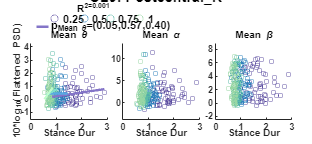



 CL9) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                         -0.14255    0.42992    -0.33157    0.74051
    cond_char_0.5                         0.5434    0.78281     0.69416    0.48826
    cond_char_0.75                      -0.43066     1.0224    -0.42121    0.67399
    cond_char_1.0                        -1.4955     1.2762     -1.1719    0.24244
    mean_GaitCycleDur                    0.25157    0.18112       1.389    0.16615
    cond_char_0.5:mean_GaitCycleDur     -0.22359    0.44237    -0.50542    0

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    _______    ________

    cond_char                         1.5504         3      0.51681      0.81571     0.48629
    mean_GaitCycleDur                 3.4154         1       3.4154       5.3906    0.021097
    cond_char:mean_GaitCycleDur       2.3039         3      0.76797       1.2121     0.30599
    Error                             149.52       236      0.63357                         
    Total                             155.17       243                                      





 CL9) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE         tStat      pValue 
                                        ________    _______    _________    _______

    (Intercept)                           1.7316     1.2166       1.4233    0.15598
    cond_char_0.5                       0.085399     2.2153      0.03855    0.96928
    cond_char_0.75                        1.9484     2.8934       0.6734    0.50135
    cond_char_1.0                         1.8389     3.6115      0.50918     0.6111
    mean_GaitCycleDur                    0.14412    0.51256      0.28117    0.77882
    cond_char_0.5:mean_GaitCycleDur     -0.10912     1.2519    -0.087

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                          3.368         3      1.1227       0.22126    0.88158
    mean_GaitCycleDur                 2.4636         1      2.4636       0.48554    0.48661
    cond_char:mean_GaitCycleDur       4.0253         3      1.3418       0.26444    0.85098
    Error                             1197.4       236      5.0739                         
    Total                             1202.9       243                                     





 CL9) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat        pValue  
                                        ________    _______    ________    __________

    (Intercept)                           3.6273      1.086      3.3399    0.00097399
    cond_char_0.5                        0.39068     1.9775     0.19756       0.84356
    cond_char_0.75                        2.3965     2.5828     0.92788       0.35442
    cond_char_1.0                          3.762     3.2238      1.1669       0.24441
    mean_GaitCycleDur                    -0.3724    0.45754    -0.81392       0.41651
    cond_char_0.5:mean_GaitCycleDur     -0.48737     1.1

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    _______    ________

    cond_char                         8.0433         3      2.6811       0.66313     0.57548
    mean_GaitCycleDur                 23.222         1      23.222        5.7436    0.017328
    cond_char:mean_GaitCycleDur       13.905         3       4.635        1.1464     0.33107
    Error                             954.17       236      4.0431                          
    Total                              980.6       243                                      



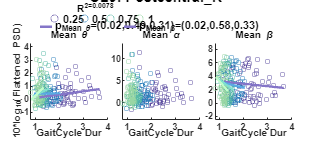



 CL9) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue 
                                              ________    _______    ________    _______

    (Intercept)                                0.61994    0.38458       1.612     0.1083
    cond_char_0.5                             -0.28788    0.65532     -0.4393    0.66085
    cond_char_0.75                              0.3099    0.72712     0.42621    0.67034
    cond_char_1.0                             0.069556    0.76467    0.090961     0.9276
    mean_PeakUpDownVel_mean                    -1.6134     3.2774    -0.49228    0.62298
    cond_char_0.5:mean_PeakUpDownVel_

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                              0.36264         3      0.12088      0.18583    0.90597
    mean_PeakUpDownVel_mean                0.16462         1      0.16462      0.25307    0.61539
    cond_char:mean_PeakUpDownVel_mean      0.26082         3      0.08694      0.13365    0.93994
    Error                                   153.52       236       0.6505                        
    Total                                   155.17       243                                     





 CL9) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE       tStat      pValue 
                                              ________    ______    ________    _______

    (Intercept)                                1.0184      1.069     0.95264    0.34175
    cond_char_0.5                              1.4372     1.8216       0.789    0.43091
    cond_char_0.75                             1.3097     2.0211     0.64801    0.51761
    cond_char_1.0                             -1.5143     2.1256    -0.71244    0.47689
    mean_PeakUpDownVel_mean                    9.2497     9.1102      1.0153      0.311
    cond_char_0.5:mean_PeakUpDownVel_mean </

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               10.017         3      3.3389        0.6643    0.57475
    mean_PeakUpDownVel_mean                 3.1183         1      3.1183       0.62041    0.43168
    cond_char:mean_PeakUpDownVel_mean       11.069         3      3.6898       0.73412    0.53259
    Error                                   1186.2       236      5.0262                         
    Total                                   1202.9       243                                     





 CL9) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE         tStat        pValue  
                                              _________    _______    __________    _________

    (Intercept)                                  3.0689    0.96608        3.1767    0.0016887
    cond_char_0.5                               0.11221     1.6462      0.068163      0.94571
    cond_char_0.75                               1.8094     1.8265       0.99062      0.32289
    cond_char_1.0                              -0.49067     1.9209      -0.25544      0.79861
    mean_PeakUpDownVel_mean                     -2.6576      8.233       -0.3228      0.74713
    

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               5.2876         3      1.7625       0.42939    0.73213
    mean_PeakUpDownVel_mean                  4.656         1       4.656        1.1343    0.28795
    cond_char:mean_PeakUpDownVel_mean       5.3609         3       1.787       0.43534    0.72791
    Error                                   968.73       236      4.1048                         
    Total                                    980.6       243                                     



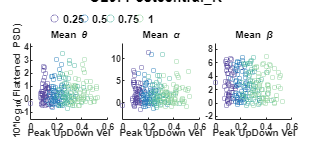



 CL10) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                        0.73092     0.31411      2.3269    0.020878
    cond_char_0.5                     -0.29102     0.52086    -0.55873     0.57691
    cond_char_0.75                    -0.16036     0.51998    -0.30839     0.75808
    cond_char_1.0                      0.11245     0.48799     0.23043     0.81797
    mean_APexc_COV                   -0.007353    0.012835    -0.57289     0.56731
    cond_char_0.5:mean_APexc_COV      0.012016    0.023889       0.503     0.61

                                SumOfSquares    DF     MeanSquares        F        pValue 
                                ____________    ___    ___________    _________    _______

    cond_char                      0.36823        3       0.12274       0.20577    0.89233
    mean_APexc_COV               0.0029338        1     0.0029338     0.0049182    0.94415
    cond_char:mean_APexc_COV       0.26053        3      0.086843       0.14559    0.93243
    Error                           131.23      220        0.5965                         
    Total                           133.22      227                                       





 CL10) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue  
                                     __________    ________    _________    _________

    (Intercept)                           2.867      1.0613       2.7014    0.0074434
    cond_char_0.5                      -0.17996      1.7599     -0.10226      0.91864
    cond_char_0.75                     -0.15712      1.7569    -0.089431      0.92882
    cond_char_1.0                      -0.14174      1.6488    -0.085967      0.93157
    mean_APexc_COV                    -0.010702    0.043367     -0.24679       0.8053
    cond_char_0.5:mean_APexc_COV     -0.0090347    0.08071

                                SumOfSquares    DF     MeanSquares        F        pValue 
                                ____________    ___    ___________    _________    _______

    cond_char                      0.1012         3     0.033733      0.0049536    0.99952
    mean_APexc_COV                 2.2615         1       2.2615        0.33209    0.56502
    cond_char:mean_APexc_COV      0.18827         3     0.062758      0.0092158    0.99878
    Error                          1498.2       220       6.8098                          
    Total                          1504.6       227                                       





 CL10) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate         SE         tStat       pValue  
                                     ___________    ________    _________    _________

    (Intercept)                            1.468     0.56169       2.6136    0.0095787
    cond_char_0.5                        0.29738     0.93138      0.31928      0.74981
    cond_char_0.75                       -0.1134     0.92981     -0.12196      0.90304
    cond_char_1.0                        0.11434     0.87261      0.13103      0.89587
    mean_APexc_COV                      0.011691    0.022951      0.50937        0.611
    cond_char_0.5:mean_APexc_COV       -0.019223    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                       0.3331        3      0.11103      0.058213    0.98153
    mean_APexc_COV                0.088466        1     0.088466      0.046381    0.82968
    cond_char:mean_APexc_COV       0.49279        3      0.16426      0.086121    0.96758
    Error                           419.62      220       1.9074                         
    Total                           421.49      227                                      



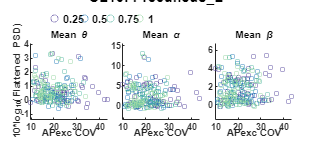



 CL10) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat       pValue 
                                      _________    _______    _________    ________

    (Intercept)                         0.74058    0.33011       2.2434    0.025864
    cond_char_0.5                      -0.41846    0.53778     -0.77812     0.43733
    cond_char_0.75                    -0.068237    0.59839     -0.11403     0.90931
    cond_char_1.0                       0.14499    0.61457      0.23593     0.81371
    mean_APexc_mean                     -2.8653     5.0017     -0.57286     0.56732
    cond_char_0.5:mean_APexc_mean        7.1464     9.7429       0.7335

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       0.52474        3       0.17491     0.29342    0.83013
    mean_APexc_mean               0.0075589        1     0.0075589     0.01268    0.91045
    cond_char:mean_APexc_mean       0.35031        3       0.11677     0.19588    0.89913
    Error                            131.15      220       0.59612                       
    Total                            133.22      227                                     





 CL10) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                        2.4996     1.1144       2.243    0.025895
    cond_char_0.5                     0.65691     1.8155     0.36185     0.71781
    cond_char_0.75                    0.88916     2.0201     0.44016     0.66025
    cond_char_1.0                     -0.4189     2.0747    -0.20191     0.84017
    mean_APexc_mean                    1.9093     16.885     0.11308     0.91007
    cond_char_0.5:mean_APexc_mean     -19.439      32.89    -0.59104      0.5551
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.8597         3      0.95323      0.14031    0.93577
    mean_APexc_mean                 1.7126         1       1.7126      0.25209    0.61611
    cond_char:mean_APexc_mean       4.9142         3       1.6381      0.24112    0.86759
    Error                           1494.6       220       6.7935                        
    Total                           1504.6       227                                     





 CL10) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat        pValue  
                                      ________    _______    _________    __________

    (Intercept)                         2.0875    0.58942       3.5417    0.00048533
    cond_char_0.5                     -0.11925    0.96023     -0.12419       0.90128
    cond_char_0.75                    -0.14262     1.0684     -0.13349       0.89393
    cond_char_1.0                      -1.0771     1.0973     -0.98156       0.32739
    mean_APexc_mean                    -5.5616     8.9307     -0.62275       0.53409
    cond_char_0.5:mean_APexc_mean      -1.6103     17.396    -0.0

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       1.9399         3      0.64664       0.34024    0.79625
    mean_APexc_mean                0.06649         1      0.06649      0.034985     0.8518
    cond_char:mean_APexc_mean       1.3896         3      0.46319       0.24372    0.86575
    Error                           418.11       220       1.9005                         
    Total                           421.49       227                                      



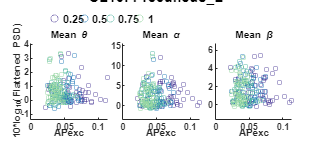



 CL10) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                        0.70152     0.25376      2.7645    0.0061853
    cond_char_0.5                     -0.52064     0.38896     -1.3385       0.1821
    cond_char_0.75                    -0.06426     0.43717    -0.14699      0.88327
    cond_char_1.0                      0.11955     0.46905     0.25488      0.79905
    mean_MLexc_COV                   -0.011238    0.018555    -0.60563      0.54538
    cond_char_0.5:mean_MLexc_COV      0.038888    0.028561      1.3616  

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                       1.4514        3      0.48379      0.81661     0.4859
    mean_MLexc_COV                0.068212        1     0.068212      0.11514    0.73469
    cond_char:mean_MLexc_COV         1.178        3      0.39267       0.6628    0.57574
    Error                           130.34      220      0.59243                        
    Total                           133.22      227                                     





 CL10) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat        pValue  
                                     _________    ________    _________    __________

    (Intercept)                         3.1493     0.85802       3.6704    0.00030395
    cond_char_0.5                     -0.13317      1.3152     -0.10126       0.91944
    cond_char_0.75                     -0.1543      1.4782     -0.10439       0.91696
    cond_char_1.0                      -0.3702      1.5859     -0.23343       0.81565
    mean_MLexc_COV                   -0.042311    0.062738     -0.67441       0.50076
    cond_char_0.5:mean_MLexc_COV     -0.014486     0.09657

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.3771         3       0.1257      0.018559    0.99655
    mean_MLexc_COV                 9.4828         1       9.4828        1.4001    0.23798
    cond_char:mean_MLexc_COV      0.65499         3      0.21833      0.032235    0.99221
    Error                            1490       220        6.773                         
    Total                          1504.6       227                                      





 CL10) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat        pValue  
                                     __________    ________    ________    __________

    (Intercept)                          1.8609     0.45329      4.1053    5.6923e-05
    cond_char_0.5                       0.34657      0.6948     0.49881       0.61841
    cond_char_0.75                      0.13985     0.78092     0.17908       0.85804
    cond_char_1.0                      -0.69138     0.83786    -0.82517       0.41017
    mean_MLexc_COV                   -0.0097708    0.033145    -0.29479       0.76843
    cond_char_0.5:mean_MLexc_COV       -0.03675    0.051018

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      2.7241         3      0.90803      0.48035    0.69628
    mean_MLexc_COV                 1.2646         1       1.2646      0.66898    0.41429
    cond_char:mean_MLexc_COV       3.2862         3       1.0954      0.57948    0.62907
    Error                          415.87       220       1.8903                        
    Total                          421.49       227                                     



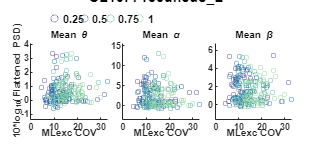



 CL10) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                        0.51493    0.36576      1.4078    0.16059
    cond_char_0.5                      0.38338    0.52396     0.73169    0.46513
    cond_char_0.75                    0.061731    0.55509     0.11121    0.91155
    cond_char_1.0                      0.68143     0.5708      1.1938    0.23383
    mean_MLexc_mean                    0.37202     2.8501     0.13053    0.89627
    cond_char_0.5:mean_MLexc_mean      -4.1678     4.7124    -0.88443    0.37743
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.0441         3      0.34803      0.58794    0.62351
    mean_MLexc_mean                0.53596         1      0.53596      0.90542    0.34238
    cond_char:mean_MLexc_mean       1.0643         3      0.35478      0.59934    0.61607
    Error                           130.23       220      0.59195                        
    Total                           133.22       227                                     





 CL10) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE        tStat        pValue 
                                      _________    ______    __________    ________

    (Intercept)                          2.9162    1.2372        2.3572    0.019293
    cond_char_0.5                       0.56315    1.7723       0.31775     0.75098
    cond_char_0.75                     -0.44427    1.8776      -0.23662     0.81317
    cond_char_1.0                       0.47509    1.9307       0.24607     0.80586
    mean_MLexc_mean                     -2.4083    9.6403      -0.24981     0.80296
    cond_char_0.5:mean_MLexc_mean       -9.9265     15.94      -0.62275

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        2.342         3      0.78065      0.11527     0.9511
    mean_MLexc_mean                 6.7815         1       6.7815       1.0013    0.31809
    cond_char:mean_MLexc_mean       4.4319         3       1.4773      0.21813    0.88376
    Error                             1490       220       6.7726                        
    Total                           1504.6       227                                     





 CL10) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat       pValue  
                                      _________    _______    _________    _________

    (Intercept)                          2.1485     0.6556       3.2771    0.0012185
    cond_char_0.5                      -0.24766    0.93918      -0.2637      0.79226
    cond_char_0.75                     -0.50001    0.99498     -0.50254      0.61579
    cond_char_1.0                     -0.099709     1.0231    -0.097456      0.92245
    mean_MLexc_mean                     -3.3264     5.1086     -0.65114      0.51564
    cond_char_0.5:mean_MLexc_mean        0.3538     8.4468     0.

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.5231         3      0.17437      0.091682    0.96457
    mean_MLexc_mean                 1.3579         1       1.3579       0.71398    0.39904
    cond_char:mean_MLexc_mean      0.37172         3      0.12391       0.06515    0.97826
    Error                           418.41       220       1.9019                         
    Total                           421.49       227                                      



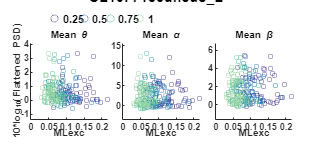



 CL10) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate       SE         tStat      pValue 
                                   _________    _______    _________    _______

    (Intercept)                       0.4265    0.43692      0.97615    0.33006
    cond_char_0.5                   -0.26927    0.84843     -0.31737    0.75126
    cond_char_0.75                  -0.07948     1.0926    -0.072742    0.94208
    cond_char_1.0                  -0.062945     1.3485     -0.04668    0.96281
    mean_StepDur                     0.11647    0.36844      0.31612    0.75221
    cond_char_0.5:mean_StepDur       0.34757    0.96227       0.3612     0.7183
    cond_char_

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    ________    _______

    cond_char                   0.060136        3     0.020045      0.033611    0.99171
    mean_StepDur                 0.22497        1      0.22497       0.37722    0.53973
    cond_char:mean_StepDur       0.13174        3     0.043915      0.073635    0.97408
    Error                          131.2      220      0.59638                         
    Total                         133.22      227                                      





 CL10) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat      pValue 
                                   ________    ______    ________    _______

    (Intercept)                     2.0395     1.4746       1.383    0.16805
    cond_char_0.5                   1.4065     2.8635     0.49117    0.62379
    cond_char_0.75                  1.2967     3.6877     0.35163    0.72546
    cond_char_1.0                  -2.3569     4.5511    -0.51787    0.60507
    mean_StepDur                   0.50297     1.2435     0.40449    0.68625
    cond_char_0.5:mean_StepDur     -1.9269     3.2477     -0.5933    0.55359
    cond_char_0.75:mean_StepDur

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    ________    _______

    cond_char                    4.8381         3       1.6127        0.2374    0.87022
    mean_StepDur                0.32217         1      0.32217      0.047425    0.82781
    cond_char:mean_StepDur       5.6121         3       1.8707       0.27537    0.84313
    Error                        1494.5       220       6.7933                         
    Total                        1504.6       227                                      





 CL10) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue  
                                   ________    _______    ________    _________

    (Intercept)                      2.1531    0.78005      2.7601    0.0062648
    cond_char_0.5                   0.22789     1.5147     0.15045      0.88055
    cond_char_0.75                  0.60139     1.9507     0.30829      0.75815
    cond_char_1.0                   -1.0081     2.4074    -0.41874      0.67582
    mean_StepDur                   -0.35956    0.65778    -0.54662      0.58519
    cond_char_0.5:mean_StepDur     -0.58626      1.718    -0.34125      0.73324
    cond_char_0

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    0.6345         3       0.2115      0.11126    0.95346
    mean_StepDur                0.42516         1      0.42516      0.22366    0.63674
    cond_char:mean_StepDur      0.86437         3      0.28812      0.15157     0.9286
    Error                        418.21       220       1.9009                        
    Total                        421.49       227                                     



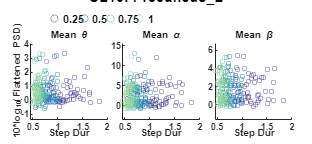



 CL10) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    ________    _______

    (Intercept)                         1.0658     0.46666      2.2839    0.02333
    cond_char_0.5                     -0.79485     0.70976     -1.1199    0.26398
    cond_char_0.75                    -0.51775     0.66868    -0.77429    0.43959
    cond_char_1.0                     -0.68684     0.67499     -1.0176       0.31
    mean_UDexc_COV                   -0.024359    0.021964      -1.109    0.26863
    cond_char_0.5:mean_UDexc_COV      0.042842    0.043041     0.99536    0.32066
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      0.9418         3      0.31393      0.53014    0.66205
    mean_UDexc_COV                0.21347         1      0.21347      0.36049    0.54885
    cond_char:mean_UDexc_COV       1.2148         3      0.40493      0.68381     0.5628
    Error                          130.28       220      0.59217                        
    Total                          133.22       227                                     





 CL10) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat        pValue  
                                     ________    ________    ________    __________

    (Intercept)                        5.7015      1.5384       3.706    0.00026641
    cond_char_0.5                     -1.7167      2.3398    -0.73366       0.46394
    cond_char_0.75                    -1.6116      2.2044    -0.73106       0.46552
    cond_char_1.0                     0.69136      2.2252     0.31069       0.75633
    mean_UDexc_COV                   -0.14866    0.072409      -2.053      0.041257
    cond_char_0.5:mean_UDexc_COV     0.029335     0.14189     0.20674   

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      10.354         3      3.4514       0.53628      0.65789
    mean_UDexc_COV                 71.241         1      71.241         11.07    0.0010284
    cond_char:mean_UDexc_COV       20.117         3      6.7057         1.042      0.37484
    Error                          1415.9       220      6.4357                           
    Total                          1504.6       227                                       





 CL10) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         2.5523     0.81964      3.1139    0.0020918
    cond_char_0.5                     0.079838      1.2466    0.064045      0.94899
    cond_char_0.75                     0.14243      1.1745     0.12127      0.90359
    cond_char_1.0                       1.0633      1.1855     0.89686      0.37078
    mean_UDexc_COV                   -0.039248    0.038578     -1.0174       0.3101
    cond_char_0.5:mean_UDexc_COV     -0.032478    0.075597    -0.42962   

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      1.8547         3      0.61822      0.33843      0.79756
    mean_UDexc_COV                 17.986         1       17.986       9.8461    0.0019348
    cond_char:mean_UDexc_COV         7.28         3       2.4267       1.3284      0.26598
    Error                          401.89       220       1.8268                          
    Total                          421.49       227                                       



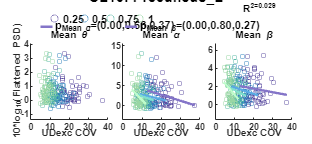



 CL10) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         0.6184     0.3409       1.814    0.071039
    cond_char_0.5                     0.055318    0.56984    0.097076     0.92275
    cond_char_0.75                    -0.13416    0.61924    -0.21665     0.82868
    cond_char_1.0                      0.01603    0.65913     0.02432     0.98062
    mean_UDexc_mean                    -3.8236     21.576    -0.17721      0.8595
    cond_char_0.5:mean_UDexc_mean      -3.1917     30.958     -0.1031     0.91798
   

                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    cond_char                       0.048437       3      0.016146      0.027041    0.99398
    mean_UDexc_mean               0.00022474       1    0.00022474     0.0003764    0.98454
    cond_char:mean_UDexc_mean        0.18081       3       0.06027       0.10094    0.95941
    Error                             131.36     220       0.59708                         
    Total                             133.22     227                                       





 CL10) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat       pValue 
                                      ________    ______    ________    ________

    (Intercept)                         2.2726    1.1433      1.9877    0.048083
    cond_char_0.5                      0.56582    1.9112     0.29606     0.76746
    cond_char_0.75                    -0.94412    2.0768     -0.4546     0.64985
    cond_char_1.0                      -3.0654    2.2106     -1.3867     0.16695
    mean_UDexc_mean                     23.006    72.363     0.31792     0.75084
    cond_char_0.5:mean_UDexc_mean      -50.239    103.83    -0.48387     0.62896
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       17.323         3      5.7744       0.85977    0.46275
    mean_UDexc_mean                 5.4455         1      5.4455       0.81081    0.36886
    cond_char:mean_UDexc_mean       11.503         3      3.8342        0.5709    0.63473
    Error                           1477.6       220      6.7161                         
    Total                           1504.6       227                                     





 CL10) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat        pValue  
                                      ________    ______    ________    __________

    (Intercept)                         2.4223    0.6043      4.0085    8.3691e-05
    cond_char_0.5                     -0.13859    1.0101     -0.1372         0.891
    cond_char_0.75                    -0.82989    1.0977    -0.75603       0.45044
    cond_char_1.0                      -2.2188    1.1684      -1.899      0.058871
    mean_UDexc_mean                    -45.372    38.247     -1.1863       0.23679
    cond_char_0.5:mean_UDexc_mean       12.001    54.877     0.21869       0.82

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       7.4341         3        2.478       1.3208    0.26847
    mean_UDexc_mean                0.67515         1      0.67515      0.35985    0.54921
    cond_char:mean_UDexc_mean        7.597         3       2.5323       1.3497    0.25916
    Error                           412.76       220       1.8762                        
    Total                           421.49       227                                     



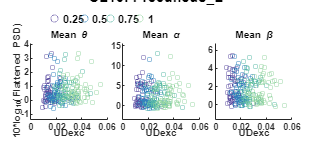



 CL10) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE         tStat      pValue 
                                     _________    _______    _________    _______

    (Intercept)                        0.45506    0.42063       1.0819    0.28049
    cond_char_0.5                     -0.36287    0.83887     -0.43257    0.66575
    cond_char_0.75                    -0.32943     1.1272     -0.29224    0.77038
    cond_char_1.0                    -0.032597     1.4144    -0.023047    0.98163
    mean_StanceDur                    0.062216    0.24013       0.2591     0.7958
    cond_char_0.5:mean_StanceDur       0.34438     0.7048      0.48862     0.6256
    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.14124         3      0.04708      0.079018    0.97133
    mean_StanceDur                0.26853         1      0.26853       0.45069    0.50271
    cond_char:mean_StanceDur      0.27374         3     0.091248       0.15315    0.92759
    Error                          131.08       220      0.59582                         
    Total                          133.22       227                                      





 CL10) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                        2.287      1.4202      1.6104    0.10874
    cond_char_0.5                     1.1636      2.8323     0.41082    0.68161
    cond_char_0.75                    1.2011      3.8059     0.31558    0.75262
    cond_char_1.0                    -3.1907      4.7754    -0.66815    0.50474
    mean_StanceDur                   0.19558     0.81074     0.24124     0.8096
    cond_char_0.5:mean_StanceDur     -1.2635      2.3796    -0.53096    0.59598
    cond_cha

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      5.4832         3       1.8277        0.2691    0.84764
    mean_StanceDur                0.51665         1      0.51665      0.076067    0.78296
    cond_char:mean_StanceDur       6.1499         3         2.05       0.30182    0.82406
    Error                          1494.2       220        6.792                         
    Total                          1504.6       227                                      





 CL10) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue  
                                     ________    _______    ________    _________

    (Intercept)                        2.2857    0.74953      3.0496    0.0025729
    cond_char_0.5                     0.31216     1.4948     0.20883      0.83478
    cond_char_0.75                     1.1643     2.0087     0.57964      0.56275
    cond_char_1.0                    -0.66279     2.5204    -0.26297      0.79282
    mean_StanceDur                   -0.32206    0.42789    -0.75267      0.45246
    cond_char_0.5:mean_StanceDur     -0.58451     1.2559     -0.4654      0.64211
    <

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      0.8816         3      0.29387      0.15533    0.92618
    mean_StanceDur                 1.3766         1       1.3766       0.7276    0.39459
    cond_char:mean_StanceDur       1.7142         3       0.5714      0.30202    0.82392
    Error                          416.22       220       1.8919                        
    Total                          421.49       227                                     



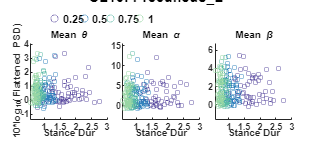



 CL10) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate       SE         tStat      pValue 
                                        _________    _______    _________    _______

    (Intercept)                           0.42285    0.43698      0.96766    0.33428
    cond_char_0.5                        -0.26152    0.84789     -0.30843    0.75804
    cond_char_0.75                      -0.084881     1.0957    -0.077469    0.93832
    cond_char_1.0                       -0.054362     1.3438    -0.040454    0.96777
    mean_GaitCycleDur                     0.05978    0.18413      0.32466    0.74575
    cond_char_0.5:mean_GaitCycleDur       0.16962    0.48056  

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                        0.056956        3     0.018985      0.031835    0.99235
    mean_GaitCycleDur                 0.22647        1      0.22647       0.37974    0.53838
    cond_char:mean_GaitCycleDur       0.12897        3      0.04299      0.072087    0.97486
    Error                               131.2      220      0.59637                         
    Total                              133.22      227                                      





 CL10) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                           2.0353     1.4749        1.38    0.16899
    cond_char_0.5                         1.3976     2.8618     0.48838    0.62577
    cond_char_0.75                         1.249     3.6982     0.33774    0.73588
    cond_char_1.0                        -2.3188     4.5356    -0.51125    0.60969
    mean_GaitCycleDur                    0.25312    0.62148     0.40728     0.6842
    cond_char_0.5:mean_GaitCycleDur     -0.95681      1.622    -0.58989    0

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                         4.7048         3       1.5683       0.23084    0.87485
    mean_GaitCycleDur                0.33558         1      0.33558      0.049395    0.82433
    cond_char:mean_GaitCycleDur        5.461         3       1.8203       0.26794    0.84847
    Error                             1494.7       220       6.7939                         
    Total                             1504.6       227                                      





 CL10) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                           2.1566    0.78021      2.7641    0.006191
    cond_char_0.5                         0.2178     1.5139     0.14387     0.88573
    cond_char_0.75                       0.58254     1.9563     0.29778     0.76615
    cond_char_1.0                       -0.95962     2.3993    -0.39996     0.68957
    mean_GaitCycleDur                   -0.18121    0.32876     -0.5512     0.58206
    cond_char_0.5:mean_GaitCycleDur     -0.28749    0.85802    -0.3350

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                        0.58348         3      0.19449       0.1023    0.95863
    mean_GaitCycleDur                0.44851         1      0.44851      0.23592    0.62765
    cond_char:mean_GaitCycleDur      0.81238         3      0.27079      0.14244    0.93443
    Error                             418.25       220       1.9011                        
    Total                             421.49       227                                     



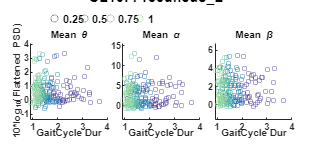



 CL10) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE         tStat       pValue 
                                              _________    _______    _________    ________

    (Intercept)                                 0.71639    0.36354       1.9706    0.050022
    cond_char_0.5                             -0.045002    0.61978    -0.072609     0.94218
    cond_char_0.75                             -0.38803    0.66391     -0.58446     0.55951
    cond_char_1.0                             -0.014282    0.66713    -0.021408     0.98294
    mean_PeakUpDownVel_mean                     -1.3195      2.958     -0.44607     0.65598
    cond_char_0.

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               0.22318        3     0.074394       0.12481    0.94537
    mean_PeakUpDownVel_mean                0.015279        1     0.015279      0.025633    0.87295
    cond_char:mean_PeakUpDownVel_mean       0.40091        3      0.13364        0.2242    0.87952
    Error                                    131.13      220      0.59607                         
    Total                                    133.22      227                                      





 CL10) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    ______    _________    ________

    (Intercept)                                3.1315     1.2232         2.56    0.011138
    cond_char_0.5                              0.2303     2.0855      0.11043     0.91217
    cond_char_0.75                            -1.2184     2.2339     -0.54541     0.58603
    cond_char_1.0                             -3.1794     2.2448      -1.4163     0.15809
    mean_PeakUpDownVel_mean                   -4.3426     9.9534     -0.43629     0.66305
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               16.474         3       5.4914       0.81369     0.4875
    mean_PeakUpDownVel_mean                0.18739         1      0.18739      0.027767    0.86781
    cond_char:mean_PeakUpDownVel_mean       13.068         3       4.3559       0.64544    0.58659
    Error                                   1484.7       220       6.7488                         
    Total                                   1504.6       227                                      





 CL10) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat        pValue  
                                              ________    _______    ________    __________

    (Intercept)                                 2.2128    0.64668      3.4217    0.00074176
    cond_char_0.5                             0.083184     1.1025     0.07545       0.93993
    cond_char_0.75                            -0.38014      1.181    -0.32188       0.74785
    cond_char_1.0                              -1.8846     1.1867      -1.588       0.11371
    mean_PeakUpDownVel_mean                    -4.0212     5.2619    -0.76422       0.44556
    cond_char_0.5

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               5.4707         3       1.8236      0.96683    0.40921
    mean_PeakUpDownVel_mean                0.83411         1      0.83411      0.44224    0.50674
    cond_char:mean_PeakUpDownVel_mean       5.3354         3       1.7785      0.94292    0.42069
    Error                                   414.95       220       1.8861                        
    Total                                   421.49       227                                     



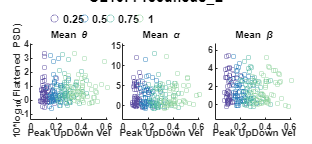



 CL11) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate         SE          tStat        pValue 
                                     ___________    _________    __________    ________

    (Intercept)                          0.34344      0.20453        1.6792    0.094402
    cond_char_0.5                        0.21457      0.32523       0.65973     0.51005
    cond_char_0.75                      -0.11921       0.3419      -0.34867     0.72764
    cond_char_1.0                      -0.046921      0.30839      -0.15215      0.8792
    mean_APexc_COV                   -5.7576e-05    0.0087321    -0.0065936     0.99474
    cond_char_0.5:mean_APexc_COV       -0.01

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      0.28785        3     0.095952      0.31323    0.81582
    mean_APexc_COV                0.083743        1     0.083743      0.27337    0.60155
    cond_char:mean_APexc_COV       0.65612        3      0.21871      0.71395    0.54449
    Error                           74.745      244      0.30633                        
    Total                           76.488      251                                     





 CL11) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         4.0576     0.87747      4.6242    6.1024e-06
    cond_char_0.5                      0.30444      1.3953     0.21819       0.82746
    cond_char_0.75                     0.09287      1.4668    0.063315       0.94957
    cond_char_1.0                     -0.74469       1.323    -0.56287       0.57404
    mean_APexc_COV                   -0.050159    0.037462     -1.3389       0.18184
    cond_char_0.5:mean_APexc_COV     -0.037388    0.064784    -0.

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                       3.396         3       1.132       0.20077     0.89579
    mean_APexc_COV                 34.319         1      34.319         6.087    0.014305
    cond_char:mean_APexc_COV       3.8171         3      1.2724       0.22567     0.87849
    Error                          1375.7       244      5.6381                          
    Total                          1418.1       251                                      





 CL11) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate         SE         tStat       pValue  
                                     ___________    ________    _________    _________

    (Intercept)                           2.1061     0.45852       4.5932    6.998e-06
    cond_char_0.5                       -0.09067     0.72911     -0.12436      0.90113
    cond_char_0.75                     -0.032872     0.76646    -0.042888      0.96583
    cond_char_1.0                       -0.15833     0.69134     -0.22902      0.81904
    mean_APexc_COV                     -0.025156    0.019576       -1.285      0.19999
    cond_char_0.5:mean_APexc_COV      0.00059513    

                                SumOfSquares    DF     MeanSquares        F         pValue 
                                ____________    ___    ___________    _________    ________

    cond_char                     0.088277        3      0.029426      0.019114      0.9964
    mean_APexc_COV                  6.0371        1        6.0371        3.9214    0.048797
    cond_char:mean_APexc_COV      0.028931        3     0.0096437     0.0062641     0.99932
    Error                           375.64      244        1.5395                          
    Total                            382.5      251                                        



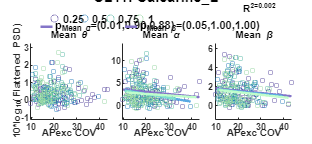



 CL11) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                        0.40052    0.22267      1.7987    0.073299
    cond_char_0.5                     -0.19151    0.34651    -0.55268     0.58099
    cond_char_0.75                     0.19217    0.39178     0.49051     0.62421
    cond_char_1.0                      0.31012    0.41561     0.74617     0.45628
    mean_APexc_mean                   -0.92224     3.3418    -0.27597     0.78281
    cond_char_0.5:mean_APexc_mean       3.7631     6.0872      0.6182     0.53702
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       0.49403        3      0.16468      0.53477    0.65886
    mean_APexc_mean                0.088497        1     0.088497      0.28739    0.59239
    cond_char:mean_APexc_mean       0.28907        3     0.096358      0.31291    0.81604
    Error                            75.136      244      0.30794                        
    Total                            76.488      251                                     





 CL11) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                         3.6124    0.96468      3.7446    0.00022541
    cond_char_0.5                      -0.8744     1.5012    -0.58245        0.5608
    cond_char_0.75                    -0.82409     1.6973    -0.48552       0.62774
    cond_char_1.0                      -1.3033     1.8006    -0.72383       0.46986
    mean_APexc_mean                    -10.422     14.478    -0.71984       0.47231
    cond_char_0.5:mean_APexc_mean       8.3713     26.372     0.31743  

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       3.9498         3       1.3166       0.22779      0.877
    mean_APexc_mean                0.06599         1      0.06599      0.011417    0.91499
    cond_char:mean_APexc_mean       1.6596         3      0.55319       0.09571    0.96235
    Error                           1410.3       244       5.7799                         
    Total                           1418.1       251                                      





 CL11) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                         1.9066    0.50122      3.8039    0.00018011
    cond_char_0.5                     -0.55418       0.78    -0.71048       0.47808
    cond_char_0.75                    -0.76819    0.88189    -0.87108       0.38457
    cond_char_1.0                     -0.63212    0.93555    -0.67566       0.49989
    mean_APexc_mean                    -5.6027     7.5225    -0.74479       0.45711
    cond_char_0.5:mean_APexc_mean       9.1471     13.702     0.66756   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.6328         3      0.54428      0.34883    0.79003
    mean_APexc_mean                0.24364         1      0.24364      0.15615    0.69307
    cond_char:mean_APexc_mean        1.495         3      0.49835      0.31939    0.81135
    Error                           380.72       244       1.5603                        
    Total                            382.5       251                                     



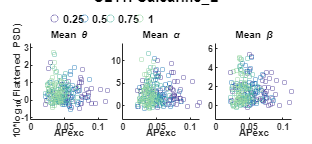



 CL11) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                        0.37446     0.18734      1.9989    0.046732
    cond_char_0.5                     -0.13079     0.28409    -0.46039     0.64564
    cond_char_0.75                    0.090628     0.30371      0.2984     0.76565
    cond_char_1.0                    -0.085354     0.32175    -0.26528     0.79101
    mean_MLexc_COV                    -0.00259    0.013941    -0.18579     0.85276
    cond_char_0.5:mean_MLexc_COV      0.010846    0.020755     0.52257     0.60

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.16877         3     0.056258      0.18259    0.90817
    mean_MLexc_COV                0.10378         1      0.10378      0.33682    0.56221
    cond_char:mean_MLexc_COV      0.16842         3     0.056141      0.18221    0.90842
    Error                           75.18       244      0.30811                        
    Total                          76.488       251                                     





 CL11) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat        pValue  
                                     ________    ________    ________    __________

    (Intercept)                        4.4302       0.797      5.5586    7.1134e-08
    cond_char_0.5                    -0.35962      1.2086    -0.29755        0.7663
    cond_char_0.75                   -0.35572      1.2921    -0.27531       0.78331
    cond_char_1.0                    -0.95102      1.3688    -0.69477       0.48786
    mean_MLexc_COV                   -0.11848    0.059308     -1.9977      0.046854
    cond_char_0.5:mean_MLexc_COV      0.00908    0.088298     0.10283   

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                         2.7         3      0.89999      0.16138      0.92225
    mean_MLexc_COV                  48.13         1        48.13       8.6304    0.0036225
    cond_char:mean_MLexc_COV       4.5003         3       1.5001      0.26899      0.84772
    Error                          1360.7       244       5.5767                          
    Total                          1418.1       251                                       





 CL11) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat        pValue  
                                     _________    ________    _________    __________

    (Intercept)                         2.1356     0.41822       5.1064    6.6169e-07
    cond_char_0.5                    -0.060937     0.63422    -0.096081       0.92354
    cond_char_0.75                    -0.14146     0.67802     -0.20864       0.83491
    cond_char_1.0                      -0.3596     0.71828     -0.50064       0.61708
    mean_MLexc_COV                     -0.0468    0.031122      -1.5038       0.13393
    cond_char_0.5:mean_MLexc_COV     0.0053627    0.046334 

                                SumOfSquares    DF     MeanSquares       F         pValue 
                                ____________    ___    ___________    ________    ________

    cond_char                     0.40836         3      0.13612      0.088643     0.96623
    mean_MLexc_COV                 6.7533         1       6.7533        4.3978    0.037014
    cond_char:mean_MLexc_COV      0.71744         3      0.23915       0.15573     0.92593
    Error                          374.69       244       1.5356                          
    Total                           382.5       251                                       



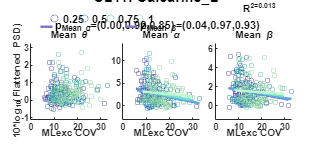



 CL11) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                        0.079776    0.25377      0.31437    0.75351
    cond_char_0.5                     -0.012404    0.37326    -0.033232    0.97352
    cond_char_0.75                      0.13387    0.39674      0.33741     0.7361
    cond_char_1.0                       0.64077    0.40044       1.6002    0.11085
    mean_MLexc_mean                      2.2433     2.0865       1.0752    0.28337
    cond_char_0.5:mean_MLexc_mean       0.86217     3.5633      0.24196    0.8

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.97749         3      0.32583       1.0701    0.36238
    mean_MLexc_mean                 0.1083         1       0.1083      0.35568    0.55147
    cond_char:mean_MLexc_mean      0.52867         3      0.17622      0.57878    0.62946
    Error                           74.292       244      0.30448                        
    Total                           76.488       251                                     





 CL11) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    ______    _________    __________

    (Intercept)                         3.7619    1.1037       3.4086    0.00076386
    cond_char_0.5                     -0.66867    1.6234     -0.41191       0.68077
    cond_char_0.75                     -0.4993    1.7255     -0.28937       0.77254
    cond_char_1.0                     -0.15018    1.7415    -0.086234       0.93135
    mean_MLexc_mean                    -6.9145    9.0746     -0.76196       0.44682
    cond_char_0.5:mean_MLexc_mean        1.913    15.497      0.12344  

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       1.1748         3      0.39159      0.067996    0.97689
    mean_MLexc_mean                 7.1382         1       7.1382        1.2395    0.26667
    cond_char:mean_MLexc_mean       1.2237         3      0.40791      0.070829    0.97549
    Error                           1405.2       244       5.7591                         
    Total                           1418.1       251                                      





 CL11) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                         2.3171    0.57215      4.0499    6.8867e-05
    cond_char_0.5                     -0.57303    0.84156    -0.68091       0.49658
    cond_char_0.75                    -0.44632    0.89451    -0.49895       0.61826
    cond_char_1.0                     -0.31338    0.90284    -0.34711       0.72881
    mean_MLexc_mean                    -6.5401     4.7044     -1.3902       0.16573
    cond_char_0.5:mean_MLexc_mean       4.2133     8.0338     0.52445   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.79614         3      0.26538      0.17146    0.91561
    mean_MLexc_mean                 2.8253         1       2.8253       1.8255    0.17792
    cond_char:mean_MLexc_mean      0.62556         3      0.20852      0.13473    0.93928
    Error                           377.65       244       1.5477                        
    Total                            382.5       251                                     



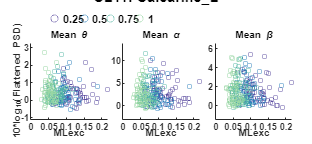



 CL11) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat      pValue 
                                   ________    _______    ________    _______

    (Intercept)                     0.38347    0.30035      1.2767    0.20291
    cond_char_0.5                   -0.4182    0.55832    -0.74903    0.45456
    cond_char_0.75                    0.213    0.72861     0.29233    0.77028
    cond_char_1.0                   0.56734    0.87567     0.64789    0.51766
    mean_StepDur                   -0.03498    0.24745    -0.14136     0.8877
    cond_char_0.5:mean_StepDur      0.51192    0.62503     0.81903    0.41357
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    ________    _______

    cond_char                    0.41608        3      0.13869       0.45055    0.71713
    mean_StepDur                0.028232        1     0.028232      0.091714    0.76227
    cond_char:mean_StepDur       0.33217        3      0.11072       0.35969    0.78217
    Error                          75.11      244      0.30783                         
    Total                         76.488      251                                      





 CL11) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat       pValue 
                                   ________    ______    ________    ________

    (Intercept)                     2.3908     1.2914      1.8514    0.065324
    cond_char_0.5                  -1.8044     2.4005    -0.75166     0.45298
    cond_char_0.75                 -3.4329     3.1327     -1.0958     0.27423
    cond_char_1.0                  -4.0273      3.765     -1.0697     0.28583
    mean_StepDur                   0.47634     1.0639     0.44771     0.65476
    cond_char_0.5:mean_StepDur      2.0497     2.6874      0.7627     0.44638
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                    12.513         3      4.1711       0.73297     0.53322
    mean_StepDur                  23.34         1       23.34        4.1016    0.043932
    cond_char:mean_StepDur       16.142         3      5.3806       0.94552     0.41925
    Error                        1388.5       244      5.6906                          
    Total                        1418.1       251                                      





 CL11) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue 
                                   ________    _______    ________    ________

    (Intercept)                      1.2975    0.67592      1.9196    0.056075
    cond_char_0.5                  -0.43143     1.2564    -0.34337     0.73161
    cond_char_0.75                 -0.82205     1.6397    -0.50135     0.61658
    cond_char_1.0                  -0.56853     1.9706     -0.2885     0.77321
    mean_StepDur                    0.21575    0.55688     0.38743     0.69877
    cond_char_0.5:mean_StepDur      0.60407     1.4066     0.42946     0.66797
    cond_char_0.75:mean

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                   0.53324         3      0.17775      0.11402    0.95185
    mean_StepDur                 1.3665         1       1.3665      0.87651    0.35008
    cond_char:mean_StepDur      0.86632         3      0.28877      0.18523    0.90638
    Error                        380.39       244        1.559                        
    Total                         382.5       251                                     



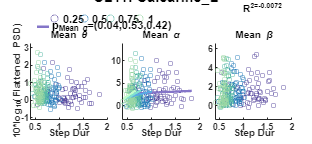



 CL11) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                        0.60846     0.31474      1.9332    0.054365
    cond_char_0.5                      -0.3682     0.47742    -0.77123     0.44131
    cond_char_0.75                    -0.35112     0.45444    -0.77265     0.44048
    cond_char_1.0                     -0.21393     0.44089    -0.48522     0.62795
    mean_UDexc_COV                   -0.013105    0.015103     -0.8677     0.38641
    cond_char_0.5:mean_UDexc_COV      0.020791    0.028539     0.72852       0.

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      0.25186        3     0.083952      0.27307    0.84479
    mean_UDexc_COV                0.061597        1     0.061597      0.20036    0.65483
    cond_char:mean_UDexc_COV       0.42212        3      0.14071      0.45768    0.71211
    Error                           75.014      244      0.30743                        
    Total                           76.488      251                                     





 CL11) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         6.4235      1.3188      4.8707    2.0006e-06
    cond_char_0.5                      -2.3251      2.0005     -1.1623       0.24627
    cond_char_0.75                     -1.8112      1.9042    -0.95117       0.34246
    cond_char_1.0                     -0.30247      1.8474    -0.16373       0.87008
    mean_UDexc_COV                     -0.1708    0.063286     -2.6988     0.0074448
    cond_char_0.5:mean_UDexc_COV      0.070143     0.11958     0.

                                SumOfSquares    DF     MeanSquares       F         pValue  
                                ____________    ___    ___________    _______    __________

    cond_char                      10.742         3      3.5808       0.66339       0.57529
    mean_UDexc_COV                 77.227         1      77.227        14.307    0.00019537
    cond_char:mean_UDexc_COV       16.743         3      5.5811         1.034       0.37816
    Error                          1317.1       244      5.3978                            
    Total                          1418.1       251                                        





 CL11) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat        pValue  
                                     __________    ________    _________    __________

    (Intercept)                          3.0328     0.69534       4.3616    1.9056e-05
    cond_char_0.5                      -0.81944      1.0548     -0.77691       0.43797
    cond_char_0.75                     -0.69852       1.004     -0.69576       0.48724
    cond_char_1.0                      -0.26262     0.97404     -0.26962       0.78768
    mean_UDexc_COV                     -0.07287    0.033368      -2.1839      0.029925
    cond_char_0.5:mean_UDexc_COV       0.025935     

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      1.2296         3      0.40987      0.27315      0.84474
    mean_UDexc_COV                 12.745         1       12.745       8.4933    0.0038958
    cond_char:mean_UDexc_COV       2.0294         3      0.67645       0.4508      0.71696
    Error                          366.13       244       1.5005                          
    Total                           382.5       251                                       



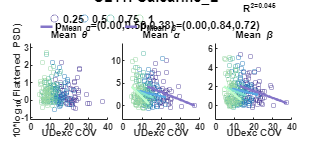



 CL11) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                       0.24557      0.2312      1.0622    0.28921
    cond_char_0.5                     0.24425      0.3993     0.61168    0.54132
    cond_char_0.75                    0.82834     0.43725      1.8944    0.05935
    cond_char_1.0                     0.61925     0.46382      1.3351    0.18309
    mean_UDexc_mean                    6.4322      14.682     0.43811    0.66169
    cond_char_0.5:mean_UDexc_mean     -13.475      21.906    -0.61516    0.53902
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.3285         3      0.44283       1.4558    0.22723
    mean_UDexc_mean                0.44978         1      0.44978       1.4787    0.22516
    cond_char:mean_UDexc_mean      0.64299         3      0.21433      0.70463    0.55008
    Error                           74.219       244      0.30418                        
    Total                           76.488       251                                     





 CL11) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                          4.618    0.99616      4.6358    5.7963e-06
    cond_char_0.5                     -0.40673     1.7205    -0.23641       0.81332
    cond_char_0.75                     0.20404      1.884      0.1083       0.91385
    cond_char_1.0                      -1.5925     1.9985    -0.79687        0.4263
    mean_UDexc_mean                    -110.85      63.26     -1.7523      0.080979
    cond_char_0.5:mean_UDexc_mean       30.272     94.385     0.32072  

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       4.2484         3      1.4161       0.25078     0.86074
    mean_UDexc_mean                  30.63         1       30.63        5.4241    0.020678
    cond_char:mean_UDexc_mean       10.679         3      3.5595       0.63034     0.59607
    Error                           1377.9       244       5.647                          
    Total                           1418.1       251                                      





 CL11) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                         2.4072    0.51852      4.6425    5.6251e-06
    cond_char_0.5                     -0.14573    0.89555    -0.16272       0.87087
    cond_char_0.75                      0.1633    0.98065     0.16652       0.86789
    cond_char_1.0                     -0.65197     1.0403    -0.62674       0.53142
    mean_UDexc_mean                    -56.933     32.928      -1.729      0.085071
    cond_char_0.5:mean_UDexc_mean       19.586     49.129     0.39866   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                      0.78916         3      0.26305      0.17193      0.9153
    mean_UDexc_mean                 7.7477         1       7.7477       5.0638    0.025323
    cond_char:mean_UDexc_mean       2.3371         3      0.77904      0.50917     0.67632
    Error                           373.33       244         1.53                         
    Total                            382.5       251                                      



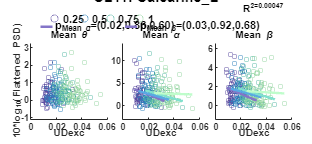



 CL11) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE         tStat      pValue 
                                     _________    _______    _________    _______

    (Intercept)                        0.35882    0.28727       1.2491    0.21284
    cond_char_0.5                        -0.52    0.54681     -0.95098    0.34256
    cond_char_0.75                   -0.039477    0.73688    -0.053574    0.95732
    cond_char_1.0                      0.49734    0.89971      0.55278    0.58092
    mean_StanceDur                   -0.009575    0.16032    -0.059725    0.95242
    cond_char_0.5:mean_StanceDur       0.48299    0.45361       1.0648    0.28803
    

                                SumOfSquares    DF     MeanSquares        F        pValue 
                                ____________    ___    ___________    _________    _______

    cond_char                      0.44016        3       0.14672       0.47746    0.69826
    mean_StanceDur               0.0022551        1     0.0022551     0.0073386     0.9318
    cond_char:mean_StanceDur       0.43252        3       0.14417       0.46916    0.70406
    Error                            74.98      244        0.3073                         
    Total                           76.488      251                                       





 CL11) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                       2.3236      1.2362      1.8796    0.061349
    cond_char_0.5                    -1.8074      2.3531    -0.76808     0.44318
    cond_char_0.75                   -3.2247       3.171     -1.0169     0.31019
    cond_char_1.0                    -4.1615      3.8717     -1.0749      0.2835
    mean_StanceDur                   0.36218     0.68989     0.52498     0.60007
    cond_char_0.5:mean_StanceDur      1.5921       1.952     0.81561     0.41552
    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      12.168         3      4.0559       0.71274     0.54522
    mean_StanceDur                 22.514         1      22.514        3.9564    0.047809
    cond_char:mean_StanceDur       16.651         3      5.5502       0.97533     0.40499
    Error                          1388.5       244      5.6906                          
    Total                          1418.1       251                                      





 CL11) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE         tStat       pValue 
                                     ________    _______    _________    ________

    (Intercept)                        1.2883    0.64793       1.9883    0.047899
    cond_char_0.5                    -0.28228     1.2333     -0.22888     0.81915
    cond_char_0.75                   -0.23269      1.662        -0.14     0.88877
    cond_char_1.0                     0.14428     2.0293     0.071102     0.94338
    mean_StanceDur                    0.15183    0.36159       0.4199     0.67493
    cond_char_0.5:mean_StanceDur      0.33234     1.0231      0.32483     0.74559
    <

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.11874         3     0.039579      0.025318    0.99454
    mean_StanceDur                0.20802         1      0.20802       0.13307    0.71559
    cond_char:mean_StanceDur      0.22389         3     0.074631       0.04774    0.98615
    Error                          381.44       244       1.5633                         
    Total                           382.5       251                                      



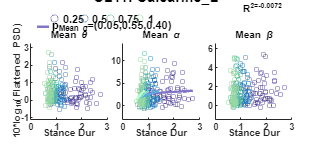



 CL11) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate       SE        tStat      pValue 
                                        _________    _______    ________    _______

    (Intercept)                           0.37743    0.30023      1.2571     0.2099
    cond_char_0.5                         -0.4113    0.55768    -0.73751    0.46152
    cond_char_0.75                        0.22384     0.7305     0.30642    0.75954
    cond_char_1.0                         0.54546    0.87386      0.6242    0.53308
    mean_GaitCycleDur                    -0.01492    0.12355    -0.12076    0.90398
    cond_char_0.5:mean_GaitCycleDur       0.25277    0.31197     0.81

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                         0.40184        3      0.13395       0.43505     0.7281
    mean_GaitCycleDur                0.023905        1     0.023905      0.077644    0.78075
    cond_char:mean_GaitCycleDur       0.31857        3      0.10619        0.3449    0.79287
    Error                              75.123      244      0.30788                         
    Total                              76.488      251                                      





 CL11) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat      pValue 
                                        ________    _______    ________    _______

    (Intercept)                          2.4075      1.2906      1.8654    0.06332
    cond_char_0.5                       -1.8317      2.3973    -0.76407    0.44556
    cond_char_0.75                      -3.4669      3.1402      -1.104    0.27067
    cond_char_1.0                       -4.1001      3.7565     -1.0915    0.27614
    mean_GaitCycleDur                   0.23085     0.53111     0.43466    0.66419
    cond_char_0.5:mean_GaitCycleDur      1.0383      1.3411      0.7742    0

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    _______    ________

    cond_char                          12.87         3        4.29       0.75405     0.52094
    mean_GaitCycleDur                 23.726         1      23.726        4.1703    0.042214
    cond_char:mean_GaitCycleDur       16.541         3      5.5138       0.96915     0.40791
    Error                             1388.2       244      5.6893                          
    Total                             1418.1       251                                      





 CL11) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                            1.303    0.67559      1.9288    0.054922
    cond_char_0.5                       -0.44314     1.2549    -0.35312      0.7243
    cond_char_0.75                      -0.82605     1.6438    -0.50253     0.61575
    cond_char_1.0                       -0.57719     1.9664    -0.29353     0.76937
    mean_GaitCycleDur                    0.10542    0.27802     0.37917     0.70489
    cond_char_0.5:mean_GaitCycleDur      0.30815      0.702     0.4389

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                        0.54458         3      0.18153      0.11644    0.95041
    mean_GaitCycleDur                 1.3723         1       1.3723      0.88026    0.34906
    cond_char:mean_GaitCycleDur      0.87992         3      0.29331      0.18814    0.90441
    Error                             380.39       244        1.559                        
    Total                              382.5       251                                     



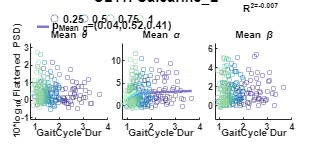



 CL11) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE         tStat      pValue 
                                              ________    _______    _________    _______

    (Intercept)                                0.38292    0.26304       1.4558    0.14674
    cond_char_0.5                              0.07814    0.46278      0.16885    0.86606
    cond_char_0.75                              0.3448    0.51469      0.66991    0.50355
    cond_char_1.0                              0.41019    0.53172      0.77144     0.4412
    mean_PeakUpDownVel_mean                   -0.35124     2.1857      -0.1607    0.87246
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               0.26651        3      0.088837      0.28841    0.83375
    mean_PeakUpDownVel_mean                 0.17132        1       0.17132       0.5562    0.45651
    cond_char:mean_PeakUpDownVel_mean      0.016166        3     0.0053887     0.017494    0.99684
    Error                                    75.158      244       0.30802                        
    Total                                    76.488      251                                      





 CL11) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE       tStat        pValue  
                                              ________    ______    ________    __________

    (Intercept)                                4.9773     1.1203      4.4428    1.3473e-05
    cond_char_0.5                             0.42247      1.971     0.21434       0.83046
    cond_char_0.75                            0.40728     2.1921     0.18579       0.85276
    cond_char_1.0                             -1.1816     2.2646    -0.52175       0.60232
    mean_PeakUpDownVel_mean                   -17.447     9.3089     -1.8743      0.062088
    cond_char_0.5:mean_

                                         SumOfSquares    DF     MeanSquares       F        pValue  
                                         ____________    ___    ___________    _______    _________

    cond_char                               2.6513         3      0.88376      0.15817      0.92435
    mean_PeakUpDownVel_mean                 49.254         1       49.254        8.815    0.0032853
    cond_char:mean_PeakUpDownVel_mean       15.296         3       5.0987      0.91252      0.43551
    Error                                   1363.3       244       5.5875                          
    Total                                   1418.1       251                                       





 CL11) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat        pValue  
                                              ________    _______    ________    __________

    (Intercept)                                 2.4324    0.58607      4.1504    4.5878e-05
    cond_char_0.5                              0.33839     1.0311     0.32818       0.74306
    cond_char_0.75                             0.20116     1.1468     0.17541        0.8609
    cond_char_1.0                             -0.91126     1.1847    -0.76918       0.44253
    mean_PeakUpDownVel_mean                    -7.5874     4.8698      -1.558       0.12052
    cond_char_0.5

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                               1.4967         3      0.49889      0.32626     0.80638
    mean_PeakUpDownVel_mean                 8.2411         1       8.2411       5.3894    0.021084
    cond_char:mean_PeakUpDownVel_mean          4.3         3       1.4333      0.93735     0.42322
    Error                                   373.11       244       1.5291                         
    Total                                    382.5       251                                      



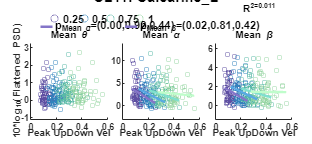



 CL12) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat      pValue 
                                     __________    ________    _________    _______

    (Intercept)                         0.46198     0.30448       1.5173     0.1306
    cond_char_0.5                     -0.091848     0.48417      -0.1897    0.84971
    cond_char_0.75                      0.16728     0.49787      0.33599     0.7372
    cond_char_1.0                     -0.018851     0.44532    -0.042332    0.96627
    mean_APexc_COV                   -0.0066681    0.012977     -0.51386    0.60786
    cond_char_0.5:mean_APexc_COV      0.0031188    0.021896      0.14243

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.15997         3     0.053322      0.080452    0.97058
    mean_APexc_COV                0.75912         1      0.75912        1.1453    0.28568
    cond_char:mean_APexc_COV      0.21117         3     0.070391        0.1062     0.9564
    Error                          148.46       224      0.66278                         
    Total                           149.4       231                                      





 CL12) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue  
                                     __________    ________    _________    _________

    (Intercept)                          4.4731     0.91599       4.8834    1.983e-06
    cond_char_0.5                       0.51051      1.4566      0.35049       0.7263
    cond_char_0.75                     -0.49086      1.4978     -0.32773      0.74342
    cond_char_1.0                      -0.90102      1.3397     -0.67257      0.50192
    mean_APexc_COV                    -0.050307    0.039038      -1.2887      0.19885
    cond_char_0.5:mean_APexc_COV      -0.040841    0.06587

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      6.0575         3      2.0192       0.33662     0.79887
    mean_APexc_COV                 31.424         1      31.424        5.2387    0.023022
    cond_char:mean_APexc_COV       3.6811         3       1.227       0.20456     0.89317
    Error                          1343.6       224      5.9984                          
    Total                          1387.8       231                                      





 CL12) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate         SE        tStat        pValue  
                                     ___________    ________    ________    __________

    (Intercept)                           2.5164     0.52874      4.7593    3.4845e-06
    cond_char_0.5                        -0.2351     0.84078    -0.27962       0.78003
    cond_char_0.75                       -1.1064     0.86457     -1.2798       0.20195
    cond_char_1.0                       -0.29749     0.77331    -0.38469       0.70083
    mean_APexc_COV                      0.012757    0.022534     0.56611       0.57189
    cond_char_0.5:mean_APexc_COV        0.010875    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      3.3981         3      1.1327       0.56673     0.63748
    mean_APexc_COV                 7.5272         1      7.5272        3.7661    0.053556
    cond_char:mean_APexc_COV       3.7227         3      1.2409       0.62087     0.60218
    Error                           447.7       224      1.9987                          
    Total                           461.5       231                                      



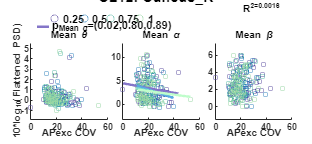



 CL12) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                       -0.022515    0.29814    -0.075518    0.93987
    cond_char_0.5                       0.43973    0.49076      0.89602    0.37121
    cond_char_0.75                      0.47061    0.59389      0.79242    0.42896
    cond_char_1.0                       0.20552    0.61395      0.33476    0.73812
    mean_APexc_mean                      5.5985     4.6105       1.2143    0.22591
    cond_char_0.5:mean_APexc_mean       -7.9791     8.7653     -0.91031    0.3

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.72814        3       0.24271      0.36679    0.77705
    mean_APexc_mean               0.0076305        1     0.0076305     0.011531    0.91458
    cond_char:mean_APexc_mean       0.76461        3       0.25487      0.38516     0.7638
    Error                            148.23      224       0.66173                        
    Total                             149.4      231                                      





 CL12) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         2.1935    0.89691      2.4456    0.015231
    cond_char_0.5                      0.42989     1.4764     0.29118     0.77118
    cond_char_0.75                    -0.57292     1.7866    -0.32066     0.74876
    cond_char_1.0                      -2.2418      1.847     -1.2138     0.22612
    mean_APexc_mean                     19.452      13.87      1.4024     0.16217
    cond_char_0.5:mean_APexc_mean      -9.6121     26.369    -0.36452     0.71582
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       11.835         3      3.9449       0.65871     0.57827
    mean_APexc_mean                 30.639         1      30.639         5.116    0.024666
    cond_char:mean_APexc_mean       12.806         3      4.2686       0.71275      0.5453
    Error                           1341.5       224      5.9889                          
    Total                           1387.8       231                                      





 CL12) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat         pValue  
                                      _________    _______    __________    __________

    (Intercept)                           2.799    0.52141        5.3682    1.9834e-07
    cond_char_0.5                       0.36837    0.85829       0.42919       0.66819
    cond_char_0.75                      0.78041     1.0387       0.75137       0.45322
    cond_char_1.0                       0.21184     1.0737       0.19729       0.84378
    mean_APexc_mean                   -0.038799     8.0632    -0.0048119       0.99616
    cond_char_0.5:mean_APexc_mean       -7.9637    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       1.2347         3      0.41156      0.20334    0.89401
    mean_APexc_mean                 3.2337         1       3.2337       1.5977    0.20754
    cond_char:mean_APexc_mean       2.5398         3      0.84661      0.41829    0.74005
    Error                           453.37       224        2.024                        
    Total                            461.5       231                                     



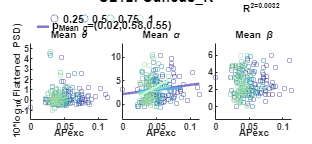



 CL12) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat      pValue 
                                     __________    ________    ________    _______

    (Intercept)                         0.37722     0.26574      1.4195    0.15714
    cond_char_0.5                      -0.39234     0.39629    -0.99003    0.32323
    cond_char_0.75                     -0.25644     0.44227    -0.57984    0.56261
    cond_char_1.0                      -0.13834     0.49478     -0.2796    0.78004
    mean_MLexc_COV                   -0.0052728    0.020782    -0.25372    0.79994
    cond_char_0.5:mean_MLexc_COV       0.029868    0.029937      0.9977     0.3

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.68534         3      0.22845      0.34508    0.79275
    mean_MLexc_COV                0.37395         1      0.37395      0.56487     0.4531
    cond_char:mean_MLexc_COV      0.70124         3      0.23375      0.35309    0.78695
    Error                          148.29       224      0.66201                        
    Total                           149.4       231                                     





 CL12) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat       pValue  
                                     ________    ________    ________    _________

    (Intercept)                        4.7795     0.80242      5.9563    9.898e-09
    cond_char_0.5                     -1.0824      1.1966    -0.90451       0.3667
    cond_char_0.75                     -1.419      1.3355     -1.0626      0.28912
    cond_char_1.0                     -1.3571       1.494    -0.90832      0.36468
    mean_MLexc_COV                   -0.12057    0.062753     -1.9213     0.055962
    cond_char_0.5:mean_MLexc_COV     0.075027    0.090398     0.82996      0.40

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      9.8197         3      3.2732       0.54226     0.65385
    mean_MLexc_COV                 16.506         1      16.506        2.7344    0.099608
    cond_char:mean_MLexc_COV        7.911         3       2.637       0.43686     0.72684
    Error                          1352.1       224      6.0363                          
    Total                          1387.8       231                                      





 CL12) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.6348     0.46622      5.6514    4.8117e-08
    cond_char_0.5                      0.18531     0.69527     0.26652       0.79008
    cond_char_0.75                     0.20143     0.77593      0.2596       0.79541
    cond_char_1.0                     0.011666     0.86806    0.013439       0.98929
    mean_MLexc_COV                    0.013829     0.03646      0.3793       0.70483
    cond_char_0.5:mean_MLexc_COV     -0.018166    0.052523    -0.3

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.23337        3     0.077791      0.038176    0.99001
    mean_MLexc_COV                0.073851        1     0.073851      0.036242    0.84919
    cond_char:mean_MLexc_COV       0.63196        3      0.21065       0.10338    0.95802
    Error                           456.45      224       2.0377                         
    Total                            461.5      231                                      



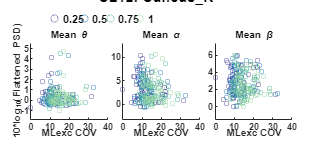



 CL12) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                       -0.35979    0.36018    -0.99891     0.31891
    cond_char_0.5                      0.51239    0.53313     0.96111     0.33753
    cond_char_0.75                     0.55708    0.59187     0.94122     0.34761
    cond_char_1.0                      0.90498    0.61335      1.4755     0.14149
    mean_MLexc_mean                     5.6964     2.9033      1.9621    0.050995
    cond_char_0.5:mean_MLexc_mean      -4.1714     4.9289    -0.84632     0.39828
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                        1.6057        3      0.53525      0.81812    0.48505
    mean_MLexc_mean                0.079679        1     0.079679      0.12179    0.72743
    cond_char:mean_MLexc_mean        1.1896        3      0.39654      0.60611    0.61167
    Error                            146.55      224      0.65424                        
    Total                             149.4      231                                     





 CL12) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    ______    _________    ________

    (Intercept)                         1.9639    1.0979       1.7887    0.075018
    cond_char_0.5                      0.11771    1.6251     0.072433     0.94232
    cond_char_0.75                     0.24548    1.8042      0.13606      0.8919
    cond_char_1.0                       1.0558    1.8697      0.56471     0.57283
    mean_MLexc_mean                     11.844    8.8501       1.3383     0.18217
    cond_char_0.5:mean_MLexc_mean     -0.93282    15.025    -0.062086     0.95055
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.1068         3      0.70228      0.11552    0.95095
    mean_MLexc_mean                 4.5444         1       4.5444      0.74752    0.38819
    cond_char:mean_MLexc_mean       1.7847         3      0.59492      0.09786    0.96115
    Error                           1361.8       224       6.0793                        
    Total                           1387.8       231                                     





 CL12) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                          2.923    0.63539      4.6003    7.0603e-06
    cond_char_0.5                     0.076413    0.94049    0.081248       0.93532
    cond_char_0.75                     0.14832     1.0441     0.14205       0.88717
    cond_char_1.0                     -0.22327      1.082    -0.20635       0.83671
    mean_MLexc_mean                    -1.0653     5.1217      -0.208       0.83542
    cond_char_0.5:mean_MLexc_mean       -1.402      8.695    -0.16125   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.22034         3     0.073446      0.036074    0.99081
    mean_MLexc_mean                 0.9002         1       0.9002       0.44214    0.50678
    cond_char:mean_MLexc_mean      0.34786         3      0.11595      0.056952     0.9821
    Error                           456.07       224        2.036                         
    Total                            461.5       231                                      



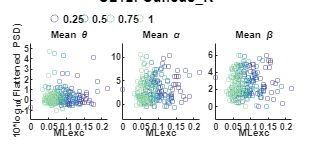



 CL12) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate       SE         tStat      pValue 
                                   _________    _______    _________    _______

    (Intercept)                     -0.23907    0.41285     -0.57906    0.56313
    cond_char_0.5                    0.16419    0.79083      0.20761    0.83572
    cond_char_0.75                  -0.31494      1.034     -0.30458    0.76097
    cond_char_1.0                   -0.29939     1.1972     -0.25006    0.80277
    mean_StepDur                      0.4804    0.34557       1.3901    0.16586
    cond_char_0.5:mean_StepDur     -0.017401    0.89737    -0.019392    0.98455
    cond_char_

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    ________    _______

    cond_char                   0.15452         3     0.051506      0.078479    0.97161
    mean_StepDur                 1.3324         1       1.3324        2.0302    0.15559
    cond_char:mean_StepDur      0.33893         3      0.11298       0.17214    0.91514
    Error                        147.01       224       0.6563                         
    Total                         149.4       231                                      





 CL12) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat       pValue 
                                   ________    ______    ________    ________

    (Intercept)                     1.5412     1.2326      1.2504     0.21245
    cond_char_0.5                  -1.2282      2.361    -0.52023     0.60342
    cond_char_0.75                 -2.9538      3.087    -0.95686     0.33967
    cond_char_1.0                  -6.1869     3.5743     -1.7309     0.08484
    mean_StepDur                    1.5824     1.0317      1.5338     0.12649
    cond_char_0.5:mean_StepDur      1.9056      2.679     0.71129     0.47765
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares      F        pValue  
                              ____________    ___    ___________    ______    _________

    cond_char                    20.639         3      6.8796       1.1761      0.31965
    mean_StepDur                 60.841         1      60.841       10.401    0.0014476
    cond_char:mean_StepDur        30.22         3      10.073       1.7221      0.16329
    Error                        1310.3       224      5.8495                          
    Total                        1387.8       231                                      





 CL12) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue  
                                   ________    _______    ________    _________

    (Intercept)                      3.4508    0.71827      4.8043    2.843e-06
    cond_char_0.5                   0.62875     1.3759     0.45699      0.64812
    cond_char_0.75                   2.2644     1.7989      1.2587      0.20944
    cond_char_1.0                    0.3206     2.0829     0.15392      0.87781
    mean_StepDur                   -0.56665    0.60122     -0.9425      0.34695
    cond_char_0.5:mean_StepDur      -1.0679     1.5612      -0.684      0.49468
    cond_char_0

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                    3.2312         3      1.0771       0.54221     0.65388
    mean_StepDur                 8.3271         1      8.3271        4.1919    0.041785
    cond_char:mean_StepDur       5.9311         3       1.977       0.99525     0.39587
    Error                        444.97       224      1.9865                          
    Total                         461.5       231                                      



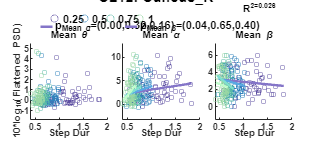



 CL12) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    ________    _______

    (Intercept)                        0.55462      0.3942       1.407    0.16083
    cond_char_0.5                     -0.63328     0.68054    -0.93056    0.35308
    cond_char_0.75                    0.068101     0.58728     0.11596    0.90779
    cond_char_1.0                      0.13798     0.54311     0.25405    0.79969
    mean_UDexc_COV                   -0.012168    0.019311    -0.63011    0.52927
    cond_char_0.5:mean_UDexc_COV       0.03845     0.04266     0.90132    0.36838
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.94939         3      0.31646      0.48043    0.69621
    mean_UDexc_COV                0.54168         1      0.54168      0.82235    0.36547
    cond_char:mean_UDexc_COV       1.2885         3       0.4295      0.65204    0.58243
    Error                          147.55       224       0.6587                        
    Total                           149.4       231                                     





 CL12) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate       SE         tStat        pValue  
                                     ________    ________    _________    __________

    (Intercept)                        5.5263       1.165       4.7435    3.7399e-06
    cond_char_0.5                     -1.3292      2.0113     -0.66086       0.50938
    cond_char_0.75                    -0.1008      1.7356    -0.058074       0.95374
    cond_char_1.0                     0.28318      1.6051      0.17642       0.86012
    mean_UDexc_COV                   -0.10983    0.057072      -1.9244      0.055576
    cond_char_0.5:mean_UDexc_COV     0.034441     0.12608      0.

                                SumOfSquares    DF     MeanSquares       F         pValue  
                                ____________    ___    ___________    _______    __________

    cond_char                      3.9583         3      1.3194       0.22933       0.87591
    mean_UDexc_COV                 74.386         1      74.386        12.929    0.00039796
    cond_char:mean_UDexc_COV       22.981         3      7.6604        1.3315       0.26494
    Error                          1288.8       224      5.7534                            
    Total                          1387.8       231                                        





 CL12) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         2.2625     0.68834      3.2869    0.0011759
    cond_char_0.5                      0.44558      1.1883     0.37496      0.70804
    cond_char_0.75                     0.31301      1.0255     0.30523      0.76047
    cond_char_1.0                       1.2531     0.94836      1.3213      0.18773
    mean_UDexc_COV                    0.027181     0.03372     0.80607      0.42106
    cond_char_0.5:mean_UDexc_COV     -0.023206     0.07449    -0.31153   

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      3.8337         3      1.2779       0.63626    0.59237
    mean_UDexc_COV                 1.0041         1      1.0041       0.49995    0.48026
    cond_char:mean_UDexc_COV        7.207         3      2.4023        1.1961    0.31207
    Error                          449.89       224      2.0084                         
    Total                           461.5       231                                     



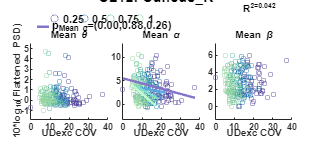



 CL12) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat      pValue 
                                      ________    _______    ________    _______

    (Intercept)                       0.13538     0.38616     0.35057    0.72624
    cond_char_0.5                     0.70667     0.63849      1.1068    0.26957
    cond_char_0.75                    0.36806     0.72062     0.51076    0.61002
    cond_char_1.0                      0.1393     0.71642     0.19444    0.84601
    mean_UDexc_mean                    12.538      25.832     0.48536     0.6279
    cond_char_0.5:mean_UDexc_mean     -39.955      35.969     -1.1108    0.26783
    

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                      0.85844         3      0.28615      0.43213     0.7302
    mean_UDexc_mean                0.16132         1      0.16132      0.24361    0.62209
    cond_char:mean_UDexc_mean      0.91811         3      0.30604      0.46216    0.70899
    Error                           148.33       224      0.66219                        
    Total                            149.4       231                                     





 CL12) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    ______    _________    ________

    (Intercept)                         3.9107    1.1753       3.3273    0.001025
    cond_char_0.5                     0.036032    1.9433     0.018541     0.98522
    cond_char_0.75                     -1.0185    2.1933     -0.46435     0.64285
    cond_char_1.0                      -2.1093    2.1806     -0.96735     0.33441
    mean_UDexc_mean                    -37.788    78.623     -0.48062     0.63126
    cond_char_0.5:mean_UDexc_mean      -3.9266    109.48    -0.035866     0.97142
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       7.0305         3       2.3435      0.38202    0.76606
    mean_UDexc_mean                0.66759         1      0.66759      0.10882    0.74179
    cond_char:mean_UDexc_mean       5.3549         3        1.785      0.29097     0.8319
    Error                           1374.1       224       6.1345                        
    Total                           1387.8       231                                     





 CL12) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat        pValue  
                                      ________    _______    _________    __________

    (Intercept)                         3.0826    0.67452       4.5701    8.0556e-06
    cond_char_0.5                     0.066614     1.1153     0.059729       0.95242
    cond_char_0.75                     0.99703     1.2587      0.79209       0.42915
    cond_char_1.0                     -0.48387     1.2514     -0.38667       0.69937
    mean_UDexc_mean                    -19.904     45.121     -0.44112       0.65955
    cond_char_0.5:mean_UDexc_mean      0.55604     62.828    0.00

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.1066         3       0.7022      0.34756    0.79095
    mean_UDexc_mean                 2.9899         1       2.9899       1.4799    0.22507
    cond_char:mean_UDexc_mean        2.013         3      0.67099      0.33211    0.80214
    Error                           452.57       224       2.0204                        
    Total                            461.5       231                                     



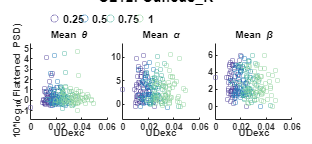



 CL12) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    ________    _______

    (Intercept)                      -0.24269    0.39237    -0.61852    0.53686
    cond_char_0.5                    0.080299    0.77337     0.10383     0.9174
    cond_char_0.75                   -0.50861     1.0597    -0.47996    0.63172
    cond_char_1.0                    -0.44175     1.2326    -0.35838     0.7204
    mean_StanceDur                    0.32817    0.22209      1.4777     0.1409
    cond_char_0.5:mean_StanceDur     0.098505    0.64957     0.15165     0.8796
    cond_cha

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      0.2497         3     0.083235      0.12733    0.94383
    mean_StanceDur                 1.6739         1       1.6739       2.5607    0.11096
    cond_char:mean_StanceDur      0.62577         3      0.20859       0.3191    0.81156
    Error                          146.43       224      0.65369                        
    Total                           149.4       231                                     





 CL12) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                       1.5514      1.1704      1.3256     0.18633
    cond_char_0.5                    -1.5737      2.3068    -0.68219     0.49582
    cond_char_0.75                   -3.4581      3.1609      -1.094     0.27512
    cond_char_1.0                    -6.6284      3.6767     -1.8028    0.072761
    mean_StanceDur                     1.068     0.66244      1.6122     0.10833
    cond_char_0.5:mean_StanceDur      1.8458      1.9375     0.95264      0.3418
    

                                SumOfSquares    DF     MeanSquares      F        pValue  
                                ____________    ___    ___________    ______    _________

    cond_char                      23.841         3       7.947       1.3664      0.25388
    mean_StanceDur                 64.671         1      64.671        11.12    0.0009996
    cond_char:mean_StanceDur       37.418         3      12.473       2.1446      0.09547
    Error                          1302.8       224       5.816                          
    Total                          1387.8       231                                      





 CL12) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat        pValue  
                                     ________    _______    ________    __________

    (Intercept)                        3.3271    0.68537      4.8544    2.2644e-06
    cond_char_0.5                     0.53135     1.3509     0.39333       0.69445
    cond_char_0.75                     2.4303      1.851      1.3129       0.19055
    cond_char_1.0                     0.32892     2.1531     0.15277       0.87872
    mean_StanceDur                   -0.31182    0.38793    -0.80381       0.42236
    cond_char_0.5:mean_StanceDur     -0.70266     1.1346    -0.61928       0.536

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      3.4837         3      1.1612       0.58223     0.62725
    mean_StanceDur                 6.7103         1      6.7103        3.3644    0.067947
    cond_char:mean_StanceDur       6.1543         3      2.0514        1.0285     0.38075
    Error                          446.77       224      1.9945                          
    Total                           461.5       231                                      



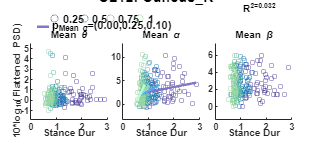



 CL12) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                         Estimate       SE         tStat      pValue 
                                        __________    _______    _________    _______

    (Intercept)                           -0.23612     0.4125     -0.57241    0.56762
    cond_char_0.5                          0.16165    0.78971       0.2047    0.83799
    cond_char_0.75                        -0.33219     1.0361     -0.32062    0.74879
    cond_char_1.0                         -0.31269     1.1941     -0.26187    0.79366
    mean_GaitCycleDur                      0.23862    0.17241        1.384    0.16773
    cond_char_0.5:mean_GaitCycleDur     -0.0074802    0

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    ________    _______

    cond_char                        0.16463         3     0.054876      0.083623    0.96891
    mean_GaitCycleDur                 1.3615         1       1.3615        2.0748    0.15115
    cond_char:mean_GaitCycleDur      0.35713         3      0.11904        0.1814    0.90895
    Error                                147       224      0.65623                         
    Total                              149.4       231                                      





 CL12) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                          1.5465      1.2313      1.2559     0.21046
    cond_char_0.5                       -1.2281      2.3573    -0.52097      0.6029
    cond_char_0.75                      -2.9989      3.0927    -0.96965     0.33326
    cond_char_1.0                       -6.2149      3.5644     -1.7436    0.082605
    mean_GaitCycleDur                   0.78795     0.51466       1.531     0.12718
    cond_char_0.5:mean_GaitCycleDur     0.95194      1.3365     0.712

                                   SumOfSquares    DF     MeanSquares      F        pValue  
                                   ____________    ___    ___________    ______    _________

    cond_char                         20.982         3       6.994       1.1961      0.31208
    mean_GaitCycleDur                  61.39         1       61.39       10.499    0.0013763
    cond_char:mean_GaitCycleDur       30.672         3      10.224       1.7485      0.15796
    Error                             1309.8       224      5.8474                          
    Total                             1387.8       231                                      





 CL12) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat        pValue  
                                        ________    _______    ________    __________

    (Intercept)                           3.4379    0.71771      4.7901    3.0315e-06
    cond_char_0.5                        0.63703      1.374     0.46363       0.64337
    cond_char_0.75                        2.2878     1.8027      1.2691       0.20571
    cond_char_1.0                         0.3582     2.0776     0.17241       0.86327
    mean_GaitCycleDur                    -0.2774    0.29998    -0.92472       0.35611
    cond_char_0.5:mean_GaitCycleDur     -0.53665    0.77

                                   SumOfSquares    DF     MeanSquares      F        pValue 
                                   ____________    ___    ___________    ______    ________

    cond_char                          3.285         3       1.095       0.5512     0.64784
    mean_GaitCycleDur                 8.4194         1      8.4194       4.2381    0.040683
    cond_char:mean_GaitCycleDur       6.0148         3      2.0049       1.0092     0.38945
    Error                             444.99       224      1.9866                         
    Total                              461.5       231                                     



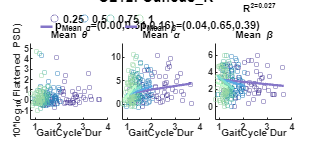



 CL12) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE         tStat       pValue 
                                              _________    _______    __________    _______

    (Intercept)                                 0.39637    0.40306       0.98339    0.32647
    cond_char_0.5                               0.15089     0.6736       0.22401    0.82296
    cond_char_0.75                              0.19249    0.74036          0.26    0.79511
    cond_char_1.0                               0.18417     0.7396       0.24901    0.80358
    mean_PeakUpDownVel_mean                    -0.71696     3.4445      -0.20815     0.8353
    cond_char_0.

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                              0.073794        3      0.024598     0.037009    0.99045
    mean_PeakUpDownVel_mean                 0.36419        1       0.36419      0.54795    0.45993
    cond_char:mean_PeakUpDownVel_mean      0.026641        3     0.0088805     0.013361    0.99788
    Error                                    148.88      224       0.66464                        
    Total                                     149.4      231                                      





 CL12) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE        tStat         pValue  
                                              _________    ______    __________    __________

    (Intercept)                                  5.4904    1.2104         4.536    9.3429e-06
    cond_char_0.5                             -0.019171    2.0228    -0.0094772       0.99245
    cond_char_0.75                              -1.4715    2.2233      -0.66186       0.50874
    cond_char_1.0                               -1.5715     2.221      -0.70754       0.47997
    mean_PeakUpDownVel_mean                     -18.814    10.344       -1.8189      0.070263
    

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                               5.1461         3      1.7154       0.28619     0.83535
    mean_PeakUpDownVel_mean                 35.037         1      35.037        5.8456    0.016416
    cond_char:mean_PeakUpDownVel_mean       16.328         3      5.4427       0.90806     0.43789
    Error                                   1342.6       224      5.9938                          
    Total                                   1387.8       231                                      





 CL12) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat        pValue  
                                              ________    _______    ________    __________

    (Intercept)                                 3.5874    0.70001      5.1247    6.4292e-07
    cond_char_0.5                              0.13752     1.1699     0.11755       0.90653
    cond_char_0.75                             0.37288     1.2858        0.29       0.77209
    cond_char_1.0                             -0.89343     1.2845    -0.69555       0.48743
    mean_PeakUpDownVel_mean                    -7.0087     5.9822     -1.1716       0.24261
    cond_char_0.5

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                               1.6272         3      0.5424       0.27056     0.84659
    mean_PeakUpDownVel_mean                 7.4363         1      7.4363        3.7093    0.055375
    cond_char:mean_PeakUpDownVel_mean       3.1486         3      1.0495       0.52352     0.66654
    Error                                   449.06       224      2.0048                          
    Total                                    461.5       231                                      



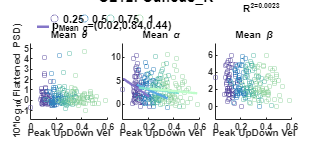



 CL13) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    _______    ________

    (Intercept)                        0.30232     0.39161    0.77201     0.44112
    cond_char_0.5                      0.83439     0.64257     1.2985     0.19577
    cond_char_0.75                      1.5571     0.65724     2.3692    0.018885
    cond_char_1.0                       1.2367     0.63965     1.9334    0.054752
    mean_APexc_COV                    0.012141    0.016943    0.71662     0.47454
    cond_char_0.5:mean_APexc_COV     -0.035033    0.030259    -1.1578      0.2485
    

                                SumOfSquares    DF     MeanSquares      F        pValue 
                                ____________    ___    ___________    ______    ________

    cond_char                      5.6974         3       1.8991      2.3189    0.077021
    mean_APexc_COV                 4.2138         1       4.2138      5.1452    0.024499
    cond_char:mean_APexc_COV       5.0217         3       1.6739      2.0439     0.10939
    Error                          147.42       180      0.81898                        
    Total                          155.59       187                                     





 CL13) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         1.6924     0.55923      3.0262    0.0028391
    cond_char_0.5                     -0.34959     0.91762    -0.38097      0.70367
    cond_char_0.75                     0.40605     0.93856     0.43263       0.6658
    cond_char_1.0                     0.042919     0.91345    0.046986      0.96258
    mean_APexc_COV                   -0.027097    0.024195       -1.12      0.26422
    cond_char_0.5:mean_APexc_COV      0.011452    0.043212     0.26501  

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                     0.87263         3      0.29088      0.17416     0.91377
    mean_APexc_COV                 6.4854         1       6.4854       3.8832    0.050306
    cond_char:mean_APexc_COV        1.125         3        0.375      0.22453     0.87926
    Error                          300.63       180       1.6701                         
    Total                          308.32       187                                      





 CL13) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue  
                                     __________    ________    ________    _________

    (Intercept)                          1.0817     0.40914      2.6439    0.0089197
    cond_char_0.5                      -0.34549     0.67135    -0.51463      0.60745
    cond_char_0.75                     -0.21033     0.68667    -0.30631      0.75972
    cond_char_1.0                      -0.31623     0.66829    -0.47319      0.63665
    mean_APexc_COV                   -0.0053797    0.017701    -0.30391      0.76154
    cond_char_0.5:mean_APexc_COV       0.016843    0.031615     0.

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                      0.32106        3      0.10702       0.11972    0.94842
    mean_APexc_COV                0.048895        1     0.048895      0.054695    0.81535
    cond_char:mean_APexc_COV       0.26745        3     0.089149      0.099723    0.96008
    Error                           160.91      180      0.89397                         
    Total                           161.78      187                                      



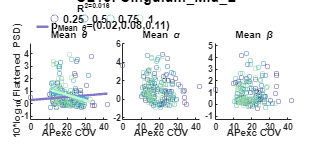



 CL13) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat       pValue 
                                      ________    _______    _________    ________

    (Intercept)                       -0.19177    0.38391     -0.49952     0.61803
    cond_char_0.5                      0.46284    0.65952      0.70179     0.48372
    cond_char_0.75                     0.48571    0.79668      0.60967     0.54285
    cond_char_1.0                      0.60693    0.72345      0.83895     0.40261
    mean_APexc_mean                      12.95     6.1514       2.1052    0.036659
    cond_char_0.5:mean_APexc_mean      -4.4567     12.254     -0.36368     0.7

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.84523         3      0.28174       0.33975    0.79661
    mean_APexc_mean                 2.2332         1       2.2332         2.693    0.10253
    cond_char:mean_APexc_mean      0.12401         3     0.041336      0.049846    0.98524
    Error                           149.27       180      0.82927                         
    Total                           155.59       187                                      





 CL13) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         1.0912    0.54927      1.9866    0.048487
    cond_char_0.5                     -0.12788    0.94359    -0.13553     0.89234
    cond_char_0.75                     0.55317     1.1398      0.4853     0.62805
    cond_char_1.0                     -0.97387     1.0351    -0.94088     0.34803
    mean_APexc_mean                    0.19693      8.801    0.022376     0.98217
    cond_char_0.5:mean_APexc_mean       1.2806     17.533    0.073042     0.94185
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       2.4598         3      0.81994       0.48302    0.69449
    mean_APexc_mean                0.16107         1      0.16107      0.094889    0.75841
    cond_char:mean_APexc_mean       2.5482         3      0.84942       0.50039    0.68248
    Error                           305.55       180       1.6975                         
    Total                           308.32       187                                      





 CL13) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE        tStat      pValue 
                                      _________    _______    ________    _______

    (Intercept)                          1.2193    0.39374      3.0967    0.00227
    cond_char_0.5                     -0.060376     0.6764    -0.08926    0.92897
    cond_char_0.75                      0.25383    0.81708     0.31066    0.75642
    cond_char_1.0                       0.76401    0.74197      1.0297    0.30453
    mean_APexc_mean                     -4.3488     6.3089    -0.68932    0.49151
    cond_char_0.5:mean_APexc_mean       0.31564     12.568    0.025115    0.97999
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       1.1036         3      0.36785      0.42172     0.73765
    mean_APexc_mean                 3.3631         1       3.3631       3.8556    0.051122
    cond_char:mean_APexc_mean       2.1831         3       0.7277      0.83426     0.47666
    Error                           157.01       180      0.87227                         
    Total                           161.78       187                                      



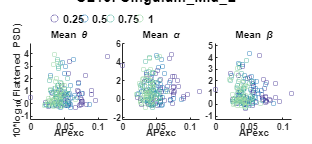



 CL13) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue 
                                     _________    ________    _______    ________

    (Intercept)                        0.41114      0.3226     1.2745     0.20415
    cond_char_0.5                      0.75684     0.52691     1.4364     0.15263
    cond_char_0.75                      1.3405     0.56323     2.3801    0.018355
    cond_char_1.0                      0.80891     0.58767     1.3765     0.17038
    mean_MLexc_COV                    0.013225    0.025043     0.5281     0.59808
    cond_char_0.5:mean_MLexc_COV     -0.051495    0.040211    -1.2806     0.20198
    

                                SumOfSquares    DF     MeanSquares      F        pValue 
                                ____________    ___    ___________    ______    ________

    cond_char                      5.2162         3       1.7387      2.1144     0.10001
    mean_MLexc_COV                 3.4947         1       3.4947      4.2497    0.040695
    cond_char:mean_MLexc_COV        3.675         3        1.225      1.4897     0.21893
    Error                          148.02       180      0.82234                        
    Total                          155.59       187                                     





 CL13) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat        pValue  
                                     __________    ________    _________    __________

    (Intercept)                          1.7796     0.45986       3.8698    0.00015217
    cond_char_0.5                      -0.79534      0.7511      -1.0589       0.29106
    cond_char_0.75                      0.11422     0.80287      0.14226       0.88703
    cond_char_1.0                      -0.68783      0.8377      -0.8211       0.41268
    mean_MLexc_COV                    -0.057609    0.035698      -1.6138       0.10832
    cond_char_0.5:mean_MLexc_COV       0.061709    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      3.0437         3      1.0146       0.60718    0.61116
    mean_MLexc_COV                 3.2959         1      3.2959        1.9724    0.16191
    cond_char:mean_MLexc_COV       3.4749         3      1.1583       0.69319    0.55732
    Error                          300.77       180       1.671                         
    Total                          308.32       187                                     





 CL13) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE         tStat        pValue  
                                     _________    ________    _________    __________

    (Intercept)                         1.2578     0.33534       3.7508    0.00023752
    cond_char_0.5                    -0.021506     0.54771    -0.039266       0.96872
    cond_char_0.75                    -0.24794     0.58547     -0.42349       0.67245
    cond_char_1.0                     -0.42299     0.61086     -0.69244       0.48955
    mean_MLexc_COV                   -0.024948    0.026032     -0.95838       0.33916
    cond_char_0.5:mean_MLexc_COV     0.0030433    0.041798 

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                     0.53515         3      0.17838      0.20076    0.89576
    mean_MLexc_COV                0.70889         1      0.70889      0.79781    0.37294
    cond_char:mean_MLexc_COV      0.45114         3      0.15038      0.16924    0.91704
    Error                          159.94       180      0.88854                        
    Total                          161.78       187                                     



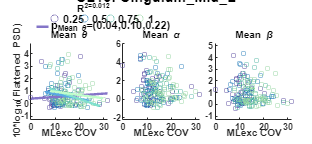



 CL13) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                        -0.15428    0.47576     -0.32429     0.7461
    cond_char_0.5                      -0.16985    0.72763     -0.23343    0.81569
    cond_char_0.75                    -0.010368    0.76001    -0.013642    0.98913
    cond_char_1.0                       0.60903    0.82248      0.74047    0.45998
    mean_MLexc_mean                      6.2759     3.9802       1.5768    0.11661
    cond_char_0.5:mean_MLexc_mean        4.7123     7.0397       0.6694     0.

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                      0.71317         3      0.23772      0.29132     0.83163
    mean_MLexc_mean                 4.1606         1       4.1606       5.0987    0.025145
    cond_char:mean_MLexc_mean      0.72353         3      0.24118      0.29555     0.82858
    Error                           146.88       180      0.81602                         
    Total                           155.59       187                                      





 CL13) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat      pValue 
                                      ________    _______    _________    _______

    (Intercept)                         1.5188    0.68727         2.21    0.02837
    cond_char_0.5                      0.07136     1.0511      0.06789    0.94595
    cond_char_0.75                    -0.53048     1.0979     -0.48318    0.62955
    cond_char_1.0                     -0.25285     1.1881     -0.21281    0.83172
    mean_MLexc_mean                    -3.6232     5.7498     -0.63015     0.5294
    cond_char_0.5:mean_MLexc_mean      -2.3999     10.169       -0.236     0.8137
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                       0.5681         3      0.18937        0.1112    0.95347
    mean_MLexc_mean                0.52407         1      0.52407       0.30775    0.57975
    cond_char:mean_MLexc_mean      0.37787         3      0.12596      0.073966     0.9739
    Error                           306.52       180       1.7029                         
    Total                           308.32       187                                      





 CL13) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat       pValue  
                                      _________    _______    _________    _________

    (Intercept)                          1.6194    0.48752       3.3218    0.0010832
    cond_char_0.5                      0.049931    0.74562     0.066967      0.94668
    cond_char_0.75                    0.0074053     0.7788    0.0095086      0.99242
    cond_char_1.0                       0.38484    0.84282      0.45661       0.6485
    mean_MLexc_mean                      -5.701     4.0786      -1.3978       0.1639
    cond_char_0.5:mean_MLexc_mean       -1.9914     7.2138     -0

                                 SumOfSquares    DF     MeanSquares       F         pValue  
                                 ____________    ___    ___________    ________    _________

    cond_char                       0.2062         3     0.068732      0.080213      0.97069
    mean_MLexc_mean                 6.3158         1       6.3158        7.3708    0.0072746
    cond_char:mean_MLexc_mean        1.356         3        0.452        0.5275      0.66395
    Error                           154.24       180      0.85687                           
    Total                           161.78       187                                        



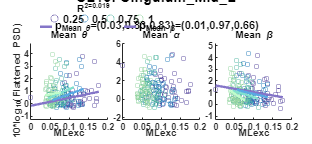



 CL13) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue 
                                   ________    _______    ________    ________

    (Intercept)                    -0.29768    0.52457    -0.56747      0.5711
    cond_char_0.5                  -0.54031     1.0257     -0.5268     0.59898
    cond_char_0.75                  -2.1449     1.4399     -1.4896     0.13808
    cond_char_1.0                   -1.4504     1.6151    -0.89803     0.37037
    mean_StepDur                    0.75689    0.44513      1.7004    0.090784
    cond_char_0.5:mean_StepDur       1.1431     1.1735      0.9741     0.33131
    cond_char_0.75:mea

                              SumOfSquares    DF     MeanSquares       F         pValue  
                              ____________    ___    ___________    _______    __________

    cond_char                     2.195         3      0.73167      0.92305       0.43085
    mean_StepDur                 9.0918         1       9.0918        11.47    0.00086858
    cond_char:mean_StepDur       4.8496         3       1.6165       2.0394       0.11001
    Error                        142.68       180      0.79266                           
    Total                        155.59       187                                        





 CL13) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE         tStat      pValue 
                                   ________    _______    _________    _______

    (Intercept)                     0.42378    0.76424      0.55452    0.57991
    cond_char_0.5                  -0.20615     1.4943     -0.13796    0.89043
    cond_char_0.75                 -0.16942     2.0978    -0.080761    0.93572
    cond_char_1.0                    -2.318      2.353     -0.98515    0.32587
    mean_StepDur                    0.59461     0.6485       0.9169    0.36042
    cond_char_0.5:mean_StepDur      0.42435     1.7096      0.24821    0.80425
    cond_char_0.75:mea

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    1.6357         3      0.54524      0.32408    0.80795
    mean_StepDur                  3.981         1        3.981       2.3662    0.12574
    cond_char:mean_StepDur       2.3111         3      0.77036      0.45788    0.71206
    Error                        302.84       180       1.6824                        
    Total                        308.32       187                                     





 CL13) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue 
                                   ________    _______    ________    ________

    (Intercept)                      1.2138    0.54764      2.2164    0.027918
    cond_char_0.5                   0.23748     1.0707     0.22179     0.82473
    cond_char_0.75                   1.4372     1.5032     0.95609     0.34031
    cond_char_1.0                    2.9917     1.6861      1.7743    0.077699
    mean_StepDur                   -0.21818     0.4647    -0.46952     0.63927
    cond_char_0.5:mean_StepDur     -0.39218     1.2251    -0.32013     0.74924
    cond_char_0.75:mean

                              SumOfSquares    DF     MeanSquares      F        pValue 
                              ____________    ___    ___________    ______    ________

    cond_char                    3.2438         3      1.0813       1.2516     0.29255
    mean_StepDur                 5.5232         1      5.5232       6.3933    0.012314
    cond_char:mean_StepDur       4.4588         3      1.4863       1.7204     0.16443
    Error                         155.5       180      0.8639                         
    Total                        161.78       187                                     



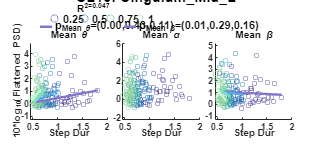



 CL13) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat      pValue 
                                     __________    ________    ________    _______

    (Intercept)                         0.67901     0.51266      1.3245    0.18702
    cond_char_0.5                        0.5868     0.86806     0.67599    0.49992
    cond_char_0.75                      0.92306     0.79475      1.1615    0.24699
    cond_char_1.0                      -0.22328     0.77679    -0.28744    0.77411
    mean_UDexc_COV                   -0.0057247    0.025186     -0.2273    0.82045
    cond_char_0.5:mean_UDexc_COV      -0.035697     0.05531    -0.64539     0.5

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      1.9817         3      0.66058      0.78415    0.50421
    mean_UDexc_COV                0.55221         1      0.55221       0.6555    0.41922
    cond_char:mean_UDexc_COV       1.9525         3      0.65082      0.77256    0.51075
    Error                          151.64       180      0.84242                        
    Total                          155.59       187                                     





 CL13) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.9628      0.6946      4.2656    3.2166e-05
    cond_char_0.5                     -0.22809      1.1761    -0.19393       0.84645
    cond_char_0.75                    -0.84653      1.0768    -0.78615       0.43281
    cond_char_1.0                     0.036039      1.0525    0.034242       0.97272
    mean_UDexc_COV                   -0.094672    0.034125     -2.7743     0.0061157
    cond_char_0.5:mean_UDexc_COV     -0.027008     0.07494    -0.

                                SumOfSquares    DF     MeanSquares       F         pValue  
                                ____________    ___    ___________    _______    __________

    cond_char                      1.2129         3      0.40429      0.26143       0.85311
    mean_UDexc_COV                 23.472         1       23.472       15.178    0.00013784
    cond_char:mean_UDexc_COV       3.4879         3       1.1626      0.75179       0.52264
    Error                          278.37       180       1.5465                           
    Total                          308.32       187                                        





 CL13) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate         SE         tStat       pValue 
                                     ___________    ________    _________    ________

    (Intercept)                           1.7332     0.52202       3.3202    0.001089
    cond_char_0.5                       0.038572     0.88392     0.043638     0.96524
    cond_char_0.75                      -0.35735     0.80927     -0.44157     0.65933
    cond_char_1.0                        -0.5936     0.79098     -0.75046     0.45396
    mean_UDexc_COV                     -0.039116    0.025646      -1.5252     0.12896
    cond_char_0.5:mean_UDexc_COV       -0.018935    0.05632

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.65743         3      0.21914       0.25088    0.86063
    mean_UDexc_COV                 2.3859         1       2.3859        2.7314    0.10013
    cond_char:mean_UDexc_COV      0.10129         3     0.033762      0.038652    0.98982
    Error                          157.23       180      0.87348                         
    Total                          161.78       187                                      



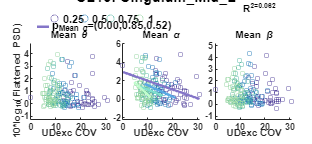



 CL13) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         0.9956    0.38405      2.5924    0.010314
    cond_char_0.5                     -0.11023    0.74579     -0.1478     0.88266
    cond_char_0.75                    0.035408    0.86589    0.040893     0.96743
    cond_char_1.0                      0.27034    0.83154     0.32511     0.74547
    mean_UDexc_mean                    -29.035     24.349     -1.1924     0.23466
    cond_char_0.5:mean_UDexc_mean       19.287     39.249      0.4914     0.62374
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.13527         3     0.045089      0.053245    0.98376
    mean_UDexc_mean                  1.185         1        1.185        1.3994    0.23839
    cond_char:mean_UDexc_mean      0.34269         3      0.11423       0.13489    0.93914
    Error                           152.43       180      0.84681                         
    Total                           155.59       187                                      





 CL13) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         1.7913    0.54225      3.3035    0.001152
    cond_char_0.5                     -0.42605      1.053     -0.4046     0.68625
    cond_char_0.75                     -1.0173     1.2226    -0.83206     0.40648
    cond_char_1.0                      -1.4809     1.1741     -1.2613     0.20883
    mean_UDexc_mean                    -46.599      34.38     -1.3554     0.17699
    cond_char_0.5:mean_UDexc_mean       30.369     55.417       0.548     0.58437
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       3.2657         3       1.0886      0.64482    0.58718
    mean_UDexc_mean                0.33924         1      0.33924      0.20095     0.6545
    cond_char:mean_UDexc_mean       4.1647         3       1.3882      0.82232    0.48311
    Error                           303.87       180       1.6882                        
    Total                           308.32       187                                     





 CL13) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat        pValue  
                                      ________    _______    ________    __________

    (Intercept)                        1.5357     0.38562      3.9824    9.8891e-05
    cond_char_0.5                     0.40031     0.74885     0.53457       0.59361
    cond_char_0.75                    0.35465     0.86944      0.4079       0.68383
    cond_char_1.0                     0.38956     0.83495     0.46657       0.64137
    mean_UDexc_mean                   -38.644      24.449     -1.5806       0.11573
    cond_char_0.5:mean_UDexc_mean     -9.3641       39.41    -0.23761   

                                 SumOfSquares    DF     MeanSquares       F         pValue 
                                 ____________    ___    ___________    ________    ________

    cond_char                      0.39783         3      0.13261       0.15532     0.92615
    mean_UDexc_mean                 7.2494         1       7.2494         8.491    0.004022
    cond_char:mean_UDexc_mean      0.20529         3      0.06843      0.080149     0.97072
    Error                           153.68       180      0.85378                          
    Total                           161.78       187                                       



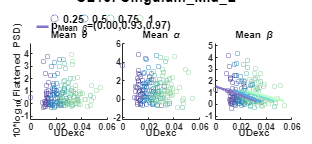



 CL13) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                      -0.24011     0.5035    -0.47689     0.63402
    cond_char_0.5                    -0.39766    0.99992    -0.39769     0.69133
    cond_char_0.75                    -1.8761     1.4827     -1.2653      0.2074
    cond_char_1.0                      -1.122     1.6679    -0.67268     0.50201
    mean_StanceDur                    0.48033     0.2895      1.6592    0.098822
    cond_char_0.5:mean_StanceDur      0.75154    0.84492     0.88947     0.37494
    

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      1.5402         3       0.5134      0.63703      0.59208
    mean_StanceDur                 6.4603         1       6.4603       8.0161    0.0051642
    cond_char:mean_StanceDur       3.8695         3       1.2898       1.6005      0.19092
    Error                          145.07       180      0.80592                          
    Total                          155.59       187                                       





 CL13) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE         tStat      pValue 
                                     _________    _______    _________    _______

    (Intercept)                        0.38816    0.72655      0.53425    0.59383
    cond_char_0.5                     -0.29238     1.4429     -0.20264    0.83965
    cond_char_0.75                   -0.084945     2.1395    -0.039702    0.96837
    cond_char_1.0                      -2.4877     2.4068      -1.0336    0.30272
    mean_StanceDur                     0.42549    0.41775       1.0185     0.3098
    cond_char_0.5:mean_StanceDur       0.44825     1.2192      0.36765    0.71357
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      1.8057         3       0.6019      0.35867    0.78293
    mean_StanceDur                  4.175         1        4.175       2.4879    0.11648
    cond_char:mean_StanceDur       2.7166         3      0.90553       0.5396    0.65576
    Error                          302.07       180       1.6781                        
    Total                          308.32       187                                     





 CL13) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate       SE        tStat       pValue 
                                     _________    _______    ________    ________

    (Intercept)                         1.1007    0.51958      2.1185    0.035505
    cond_char_0.5                       0.2016     1.0319     0.19537     0.84532
    cond_char_0.75                      1.8333     1.5301      1.1982     0.23243
    cond_char_1.0                       3.5991     1.7212       2.091    0.037931
    mean_StanceDur                   -0.081029    0.29875    -0.27123     0.78653
    cond_char_0.5:mean_StanceDur      -0.23606    0.87191    -0.27074      0.7869
    <

                                SumOfSquares    DF     MeanSquares      F        pValue  
                                ____________    ___    ___________    ______    _________

    cond_char                      4.6611         3       1.5537      1.8104       0.1469
    mean_StanceDur                 6.4888         1       6.4888      7.5607    0.0065744
    cond_char:mean_StanceDur       6.0079         3       2.0026      2.3334     0.075602
    Error                          154.48       180      0.85823                         
    Total                          161.78       187                                      



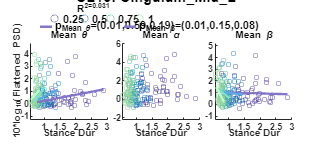



 CL13) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                         -0.29079    0.52423    -0.55471     0.57978
    cond_char_0.5                       -0.53663     1.0243    -0.52392     0.60098
    cond_char_0.75                        -2.166     1.4444     -1.4996     0.13548
    cond_char_1.0                        -1.4101     1.6095    -0.87612     0.38213
    mean_GaitCycleDur                    0.37488    0.22208      1.6881     0.09313
    cond_char_0.5:mean_GaitCycleDur      0.56829    0.58561     0.970

                                   SumOfSquares    DF     MeanSquares       F         pValue  
                                   ____________    ___    ___________    _______    __________

    cond_char                         2.1939         3      0.73128      0.92186       0.43144
    mean_GaitCycleDur                 8.9965         1       8.9965       11.341    0.00092709
    cond_char:mean_GaitCycleDur       4.8265         3       1.6088       2.0281        0.1116
    Error                             142.79       180      0.79327                           
    Total                             155.59       187                                        





 CL13) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE         tStat      pValue 
                                        ________    _______    _________    _______

    (Intercept)                          0.42949    0.76345      0.56257    0.57443
    cond_char_0.5                       -0.20776     1.4917     -0.13928    0.88939
    cond_char_0.75                      -0.18166     2.1035    -0.086359    0.93128
    cond_char_1.0                        -2.3225     2.3439     -0.99088    0.32307
    mean_GaitCycleDur                    0.29437    0.32342       0.9102    0.36394
    cond_char_0.5:mean_GaitCycleDur      0.21242    0.85284      0.24

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         1.6543         3      0.55142      0.32775    0.80529
    mean_GaitCycleDur                 3.9893         1       3.9893       2.3711    0.12535
    cond_char:mean_GaitCycleDur       2.3358         3      0.77861      0.46279    0.70862
    Error                             302.84       180       1.6824                        
    Total                             308.32       187                                     





 CL13) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                           1.2147      0.547      2.2206    0.027625
    cond_char_0.5                        0.23824     1.0688     0.22291     0.82386
    cond_char_0.75                         1.446     1.5072     0.95944     0.33862
    cond_char_1.0                         2.9885     1.6794      1.7795    0.076844
    mean_GaitCycleDur                   -0.10933    0.23173     -0.4718     0.63764
    cond_char_0.5:mean_GaitCycleDur     -0.19681    0.61105    -0.3220

                                   SumOfSquares    DF     MeanSquares      F        pValue 
                                   ____________    ___    ___________    ______    ________

    cond_char                         3.2631         3       1.0877      1.2593     0.28984
    mean_GaitCycleDur                 5.5553         1       5.5553      6.4321    0.012058
    cond_char:mean_GaitCycleDur       4.4885         3       1.4962      1.7323     0.16201
    Error                             155.46       180      0.86369                        
    Total                             161.78       187                                     



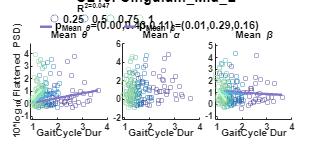



 CL13) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    _______    ________    ________

    (Intercept)                                1.0753     0.41369      2.5993    0.010116
    cond_char_0.5                             0.39853     0.80675     0.49399     0.62191
    cond_char_0.75                              0.856     0.91022     0.94044     0.34825
    cond_char_1.0                             0.75764     0.85046     0.89086     0.37419
    mean_PeakUpDownVel_mean                   -4.3291      3.3349     -1.2981     0.19591
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                               1.1485         3      0.38283      0.46476     0.70723
    mean_PeakUpDownVel_mean                 5.4015         1       5.4015       6.5575    0.011265
    cond_char:mean_PeakUpDownVel_mean      0.28045         3     0.093485      0.11349     0.95212
    Error                                   148.27       180      0.82371                         
    Total                                   155.59       187                                      





 CL13) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat        pValue  
                                              ________    _______    ________    __________

    (Intercept)                                 2.0207    0.58858      3.4333    0.00074006
    cond_char_0.5                             -0.11797     1.1478    -0.10278       0.91825
    cond_char_0.75                             0.31172      1.295     0.24071       0.81005
    cond_char_1.0                             -0.79129       1.21    -0.65396       0.51397
    mean_PeakUpDownVel_mean                    -7.8115     4.7448     -1.6463       0.10144
    cond_char_0.

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                              0.97357         3      0.32452      0.19463     0.89996
    mean_PeakUpDownVel_mean                 7.1465         1       7.1465       4.2861    0.039853
    cond_char:mean_PeakUpDownVel_mean       3.6981         3       1.2327       0.7393     0.52989
    Error                                   300.13       180       1.6674                         
    Total                                   308.32       187                                      





 CL13) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue  
                                              ________    _______    ________    _________

    (Intercept)                                 1.3288    0.42639      3.1164    0.0021311
    cond_char_0.5                              0.51486     0.8315     0.61919      0.53657
    cond_char_0.75                             0.65664    0.93815     0.69993      0.48487
    cond_char_1.0                             -0.22764    0.87656     -0.2597      0.79539
    mean_PeakUpDownVel_mean                    -3.0984     3.4373    -0.90143      0.36857
    cond_char_0.5:mean_P

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                              0.87123         3      0.29041      0.33188    0.80231
    mean_PeakUpDownVel_mean                 3.4467         1       3.4467       3.9389     0.0487
    cond_char:mean_PeakUpDownVel_mean       1.2242         3      0.40807      0.46634    0.70613
    Error                                   157.51       180      0.87504                        
    Total                                   161.78       187                                     



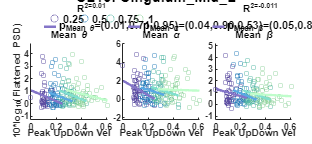



 CL14) Variable: mean_APexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat       pValue 
                                     __________    ________    _________    ________

    (Intercept)                         0.71678     0.38162       1.8782    0.061695
    cond_char_0.5                    -0.0084055     0.64437    -0.013045      0.9896
    cond_char_0.75                      0.75548     0.68825       1.0977     0.27356
    cond_char_1.0                       0.71395     0.58907        1.212     0.22684
    mean_APexc_COV                   -0.0046272    0.015854     -0.29186     0.77067
    cond_char_0.5:mean_APexc_COV     -0.0021084    0.029148    -0

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      2.6945         3      0.89818      0.81703     0.48569
    mean_APexc_COV                 3.6924         1       3.6924       3.3588    0.068222
    cond_char:mean_APexc_COV       2.2123         3      0.73745      0.67082     0.57079
    Error                          237.45       216       1.0993                         
    Total                          243.72       223                                      





 CL14) Variable: mean_APexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue 
                                     _________    ________    ________    ________

    (Intercept)                         1.2958     0.69565      1.8628    0.063852
    cond_char_0.5                     -0.59524      1.1746    -0.50676     0.61284
    cond_char_0.75                    -0.06431      1.2546    -0.05126     0.95917
    cond_char_1.0                      0.32231      1.0738     0.30016     0.76435
    mean_APexc_COV                   0.0075915      0.0289     0.26268     0.79305
    cond_char_0.5:mean_APexc_COV      0.016459    0.053133     0.30977     0.75

                                SumOfSquares    DF     MeanSquares        F        pValue 
                                ____________    ___    ___________    _________    _______

    cond_char                       1.9877        3      0.66256        0.18138    0.90896
    mean_APexc_COV                0.029659        1     0.029659      0.0081195    0.92828
    cond_char:mean_APexc_COV        2.0214        3      0.67381        0.18446    0.90689
    Error                           789.01      216       3.6528                          
    Total                           794.85      223                                       





 CL14) Variable: mean_APexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat      pValue  
                                     _________    ________    _______    _________

    (Intercept)                         2.0545     0.62686     3.2774    0.0012206
    cond_char_0.5                      -1.5819      1.0584    -1.4946      0.13649
    cond_char_0.75                     -1.5726      1.1305    -1.3911      0.16563
    cond_char_1.0                      -1.4894      0.9676    -1.5393      0.12521
    mean_APexc_COV                   0.0040582    0.026042    0.15583      0.87631
    cond_char_0.5:mean_APexc_COV      0.071245    0.047879      1.488       0.13

                                SumOfSquares    DF     MeanSquares      F        pValue  
                                ____________    ___    ___________    ______    _________

    cond_char                      11.319         3       3.773        1.272      0.28488
    mean_APexc_COV                     25         1          25       8.4285    0.0040772
    cond_char:mean_APexc_COV       11.243         3      3.7476       1.2635      0.28784
    Error                          640.68       216      2.9661                          
    Total                          671.32       223                                      



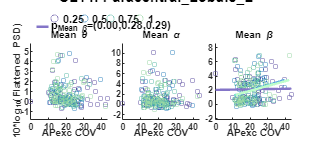



 CL14) Variable: mean_APexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat       pValue 
                                      _________    _______    __________    _______

    (Intercept)                       -0.047276    0.42819      -0.11041    0.91219
    cond_char_0.5                      0.085856    0.66672       0.12877    0.89766
    cond_char_0.75                    -0.089479    0.75515      -0.11849    0.90579
    cond_char_1.0                       0.28221    0.75913       0.37176    0.71044
    mean_APexc_mean                      10.897     6.6798        1.6314    0.10427
    cond_char_0.5:mean_APexc_mean     -0.034166     12.056    -0.002833

                                 SumOfSquares    DF     MeanSquares       F         pValue 
                                 ____________    ___    ___________    ________    ________

    cond_char                      0.22375         3     0.074583      0.068481     0.97664
    mean_APexc_mean                 5.5404         1       5.5404        5.0871    0.025107
    cond_char:mean_APexc_mean      0.42434         3      0.14145       0.12987     0.94227
    Error                           235.25       216       1.0891                          
    Total                           243.72       223                                       





 CL14) Variable: mean_APexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                        1.3841     0.77689      1.7815    0.076228
    cond_char_0.5                     0.67257      1.2097     0.55599     0.57879
    cond_char_0.75                       1.48      1.3701      1.0802     0.28127
    cond_char_1.0                      1.0954      1.3773     0.79531     0.42731
    mean_APexc_mean                    1.3488      12.119     0.11129     0.91149
    cond_char_0.5:mean_APexc_mean     -18.996      21.875    -0.86842     0.38613
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       4.9982         3      1.6661       0.46471     0.70721
    mean_APexc_mean                 14.369         1      14.369        4.0079    0.046539
    cond_char:mean_APexc_mean       11.002         3      3.6673        1.0229     0.38335
    Error                            774.4       216      3.5852                          
    Total                           794.85       223                                      





 CL14) Variable: mean_APexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_APexc_mean

Estimated Coefficients:
                                      Estimate      SE         tStat        pValue  
                                      ________    _______    _________    __________

    (Intercept)                         3.4231    0.70459       4.8583    2.2736e-06
    cond_char_0.5                     -0.14642     1.0971     -0.13346       0.89395
    cond_char_0.75                     0.49479     1.2426      0.39819       0.69088
    cond_char_1.0                     -0.70962     1.2492     -0.56807       0.57058
    mean_APexc_mean                    -21.082     10.992       -1.918      0.056425
    cond_char_0.5:mean_APexc_mean      -4.7406     19.839     -0.

                                 SumOfSquares    DF     MeanSquares       F        pValue  
                                 ____________    ___    ___________    _______    _________

    cond_char                       2.0848         3      0.69495      0.23566      0.87145
    mean_APexc_mean                 24.075         1       24.075       8.1639    0.0046908
    cond_char:mean_APexc_mean       3.2118         3       1.0706      0.36303      0.77976
    Error                           636.98       216        2.949                          
    Total                           671.32       223                                       



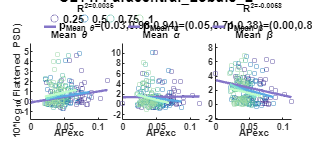



 CL14) Variable: mean_MLexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat      pValue 
                                     __________    ________    _________    _______

    (Intercept)                         0.24801     0.35672      0.69523    0.48766
    cond_char_0.5                      -0.30122     0.59648     -0.50499    0.61408
    cond_char_0.75                      0.14471     0.60944      0.23745    0.81253
    cond_char_1.0                     0.0095146     0.65975     0.014421    0.98851
    mean_MLexc_COV                     0.032094    0.028832       1.1131    0.26688
    cond_char_0.5:mean_MLexc_COV       0.019955    0.047803      0.41744

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                     0.50401         3        0.168      0.15281      0.9278
    mean_MLexc_COV                 4.6346         1       4.6346       4.2155    0.041261
    cond_char:mean_MLexc_COV      0.38345         3      0.12782      0.11626     0.95051
    Error                          237.47       216       1.0994                         
    Total                          243.72       223                                      





 CL14) Variable: mean_MLexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                      Estimate        SE        tStat       pValue 
                                     __________    ________    ________    ________

    (Intercept)                          1.5549     0.64961      2.3935    0.017544
    cond_char_0.5                       -0.1576      1.0862    -0.14509     0.88478
    cond_char_0.75                      0.29632      1.1098       0.267     0.78972
    cond_char_1.0                       0.13414      1.2014     0.11165     0.91121
    mean_MLexc_COV                   -0.0078259    0.052505    -0.14905     0.88165
    cond_char_0.5:mean_MLexc_COV     -0.0092826    0.087052    -0.10663 

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    ________    _______

    cond_char                     0.52739         3       0.1758      0.048217    0.98595
    mean_MLexc_COV                 2.5904         1       2.5904        0.7105    0.40021
    cond_char:mean_MLexc_COV       1.1536         3      0.38453       0.10547    0.95682
    Error                          787.52       216       3.6459                         
    Total                          794.85       223                                      





 CL14) Variable: mean_MLexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                     _________    ________    ________    __________

    (Intercept)                         2.9893     0.59282      5.0425    9.7163e-07
    cond_char_0.5                     -0.36176     0.99125    -0.36495       0.71551
    cond_char_0.75                    -0.33262      1.0128    -0.32842       0.74291
    cond_char_1.0                     -0.55851      1.0964     -0.5094       0.61099
    mean_MLexc_COV                   -0.074174    0.047914     -1.5481       0.12307
    cond_char_0.5:mean_MLexc_COV      0.022801    0.079441     0.2

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                     0.96948         3      0.32316      0.10643     0.95626
    mean_MLexc_COV                 11.003         1       11.003        3.624    0.058281
    cond_char:mean_MLexc_COV      0.99759         3      0.33253      0.10952     0.95447
    Error                          655.83       216       3.0363                         
    Total                          671.32       223                                      



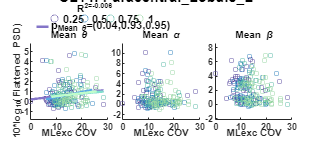



 CL14) Variable: mean_MLexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate       SE         tStat      pValue 
                                      _________    _______    _________    _______

    (Intercept)                         0.57775    0.48929       1.1808    0.23898
    cond_char_0.5                     -0.037655    0.72194    -0.052157    0.95845
    cond_char_0.75                    -0.030839    0.78292    -0.039389    0.96862
    cond_char_1.0                      0.078474    0.81593     0.096178    0.92347
    mean_MLexc_mean                     0.28921     3.8238     0.075635    0.93978
    cond_char_0.5:mean_MLexc_mean      0.025234     6.5002     0.003882    0.9

                                 SumOfSquares    DF     MeanSquares        F        pValue 
                                 ____________    ___    ___________    _________    _______

    cond_char                      0.024606        3     0.0082021     0.0073137    0.99914
    mean_MLexc_mean                 0.10989        1       0.10989      0.097985    0.75456
    cond_char:mean_MLexc_mean      0.070812        3      0.023604      0.021047    0.99585
    Error                            242.24      216        1.1215                         
    Total                            243.72      223                                       





 CL14) Variable: mean_MLexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE       tStat      pValue 
                                      ________    ______    ________    _______

    (Intercept)                        1.2643     0.8786       1.439    0.15159
    cond_char_0.5                      1.0831     1.2964     0.83548    0.40437
    cond_char_0.75                    0.58567     1.4059     0.41659    0.67739
    cond_char_1.0                     0.94121     1.4651     0.64241    0.52129
    mean_MLexc_mean                    1.6449     6.8662     0.23956     0.8109
    cond_char_0.5:mean_MLexc_mean     -13.514     11.672     -1.1578    0.24823
    cond_ch

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.9219         3      0.97397      0.26935    0.84746
    mean_MLexc_mean                 6.4757         1       6.4757       1.7908    0.18224
    cond_char:mean_MLexc_mean       6.8808         3       2.2936      0.63428    0.59366
    Error                           781.07       216       3.6161                        
    Total                           794.85       223                                     





 CL14) Variable: mean_MLexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_MLexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         2.6516    0.81038       3.272    0.001243
    cond_char_0.5                      0.02664     1.1957     0.02228     0.98225
    cond_char_0.75                    -0.26225     1.2967    -0.20224     0.83992
    cond_char_1.0                     -0.33492     1.3514    -0.24784      0.8045
    mean_MLexc_mean                    -4.1331     6.3331    -0.65262      0.5147
    cond_char_0.5:mean_MLexc_mean      -2.7146     10.766    -0.25214     0.80117
    

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    ________    _______

    cond_char                      0.33365         3      0.11122      0.036151    0.99078
    mean_MLexc_mean                  3.049         1        3.049       0.99111    0.32058
    cond_char:mean_MLexc_mean      0.27212         3     0.090707      0.029485    0.99316
    Error                            664.5       216       3.0764                         
    Total                           671.32       223                                      



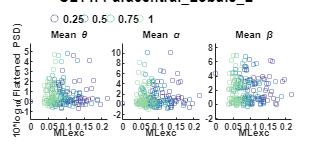



 CL14) Variable: mean_StepDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue 
                                   ________    _______    ________    ________

    (Intercept)                    -0.58547    0.57503     -1.0182     0.30974
    cond_char_0.5                   0.11331     1.0371     0.10926      0.9131
    cond_char_0.75                 -0.61685     1.3479    -0.45764     0.64767
    cond_char_1.0                   -1.1449     1.6545    -0.69197      0.4897
    mean_StepDur                     1.0325    0.48084      2.1473    0.032887
    cond_char_0.5:mean_StepDur      0.27099     1.1683     0.23194      0.8168
    cond_char_0.75:mea

                              SumOfSquares    DF     MeanSquares       F        pValue 
                              ____________    ___    ___________    _______    ________

    cond_char                   0.76575         3      0.25525      0.23929     0.86888
    mean_StepDur                 8.2153         1       8.2153       7.7016    0.006001
    cond_char:mean_StepDur        2.477         3      0.82567      0.77404     0.50964
    Error                        230.41       216       1.0667                         
    Total                        243.72       223                                      





 CL14) Variable: mean_StepDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE       tStat       pValue 
                                   ________    ______    ________    ________

    (Intercept)                      1.8223    1.0598      1.7195    0.086961
    cond_char_0.5                    1.1573    1.9113     0.60551     0.54548
    cond_char_0.75                   1.3816    2.4842     0.55616     0.57867
    cond_char_1.0                   0.09307    3.0494    0.030521     0.97568
    mean_StepDur                   -0.30707    0.8862    -0.34651      0.7293
    cond_char_0.5:mean_StepDur      -1.9271    2.1533    -0.89493     0.37182
    cond_char_0.75:mean_StepDu

                              SumOfSquares    DF     MeanSquares       F       pValue 
                              ____________    ___    ___________    _______    _______

    cond_char                    2.0483         3      0.68277      0.18844     0.9042
    mean_StepDur                 4.2087         1       4.2087       1.1616    0.28234
    cond_char:mean_StepDur       4.8288         3       1.6096      0.44423    0.72163
    Error                        782.64       216       3.6233                        
    Total                        794.85       223                                     





 CL14) Variable: mean_StepDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StepDur

Estimated Coefficients:
                                   Estimate      SE        tStat       pValue  
                                   ________    _______    _______    __________

    (Intercept)                      3.791     0.94948     3.9927    8.9538e-05
    cond_char_0.5                   1.1487      1.7124    0.67083       0.50305
    cond_char_0.75                  2.2652      2.2256     1.0178       0.30991
    cond_char_1.0                   1.8843      2.7319    0.68974        0.4911
    mean_StepDur                   -1.4175     0.79395    -1.7854      0.075602
    cond_char_0.5:mean_StepDur     -2.2421      1.9291    -1.1622       0.24643
    cond_char_0

                              SumOfSquares    DF     MeanSquares       F        pValue  
                              ____________    ___    ___________    _______    _________

    cond_char                     4.249         3      1.4163       0.48701      0.69166
    mean_StepDur                 28.941         1      28.941        9.9515    0.0018361
    cond_char:mean_StepDur       12.894         3       4.298        1.4779      0.22149
    Error                        628.18       216      2.9082                           
    Total                        671.32       223                                       



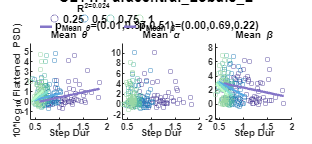



 CL14) Variable: mean_UDexc_COV, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate       SE        tStat     pValue 
                                     ________    ________    _______    _______

    (Intercept)                       0.24298     0.57115    0.42543    0.67095
    cond_char_0.5                     -1.1123     0.87222    -1.2752    0.20361
    cond_char_0.75                    0.14762     0.81213    0.18176    0.85594
    cond_char_1.0                     0.22063     0.79938      0.276    0.78281
    mean_UDexc_COV                   0.019399    0.029021    0.66844    0.50457
    cond_char_0.5:mean_UDexc_COV     0.080737     0.05338     1.5125    0.13187
    cond_cha

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      3.1601         3       1.0534      0.96519    0.41002
    mean_UDexc_COV                 3.6862         1       3.6862       3.3776    0.06746
    cond_char:mean_UDexc_COV       2.5494         3      0.84981      0.77868    0.50701
    Error                          235.73       216       1.0913                        
    Total                          243.72       223                                     





 CL14) Variable: mean_UDexc_COV, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                     Estimate        SE        tStat       pValue  
                                     _________    ________    ________    _________

    (Intercept)                         2.9162      1.0134      2.8777    0.0044075
    cond_char_0.5                      0.26998      1.5475     0.17446      0.86167
    cond_char_0.75                    -0.52748      1.4409    -0.36608      0.71467
    cond_char_1.0                      0.96942      1.4183     0.68351      0.49502
    mean_UDexc_COV                      -0.076     0.05149      -1.476       0.1414
    cond_char_0.5:mean_UDexc_COV      -0.06266    0.094709    -0.66161  

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                      3.9414         3      1.3138       0.38242     0.76577
    mean_UDexc_COV                 46.727         1      46.727        13.601    0.000286
    cond_char:mean_UDexc_COV       13.291         3      4.4304        1.2896     0.27888
    Error                          742.07       216      3.4355                          
    Total                          794.85       223                                      





 CL14) Variable: mean_UDexc_COV, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_COV

Estimated Coefficients:
                                      Estimate        SE         tStat        pValue  
                                     __________    ________    _________    __________

    (Intercept)                          4.5549     0.92584       4.9198    1.7165e-06
    cond_char_0.5                      -0.62206      1.4139     -0.43996       0.66041
    cond_char_0.75                     -0.88206      1.3165     -0.67002       0.50356
    cond_char_1.0                        -1.171      1.2958     -0.90368       0.36717
    mean_UDexc_COV                     -0.12626    0.047043       -2.684     0.0078391
    cond_char_0.5:mean_UDexc_COV     -0.0073298     

                                SumOfSquares    DF     MeanSquares       F         pValue  
                                ____________    ___    ___________    _______    __________

    cond_char                        2.53         3      0.84334      0.29408       0.82966
    mean_UDexc_COV                 39.838         1       39.838       13.892    0.00024731
    cond_char:mean_UDexc_COV       1.2184         3      0.40614      0.14163       0.93494
    Error                          619.43       216       2.8677                           
    Total                          671.32       223                                        



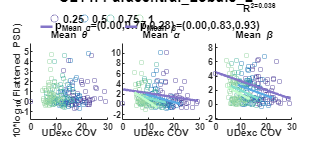



 CL14) Variable: mean_UDexc_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                       0.89291     0.46165      1.9342    0.054401
    cond_char_0.5                     0.36448      0.7587      0.4804     0.63143
    cond_char_0.75                     1.0243     0.86559      1.1834     0.23797
    cond_char_1.0                      0.4986      0.8963     0.55629     0.57859
    mean_UDexc_mean                   -19.156      30.129     -0.6358     0.52558
    cond_char_0.5:mean_UDexc_mean     -15.996      42.502    -0.37636     0.70702
   

                                 SumOfSquares    DF     MeanSquares       F        pValue 
                                 ____________    ___    ___________    _______    ________

    cond_char                       1.5992         3      0.53305       0.4867     0.69187
    mean_UDexc_mean                 5.0248         1       5.0248       4.5878    0.033319
    cond_char:mean_UDexc_mean      0.87314         3      0.29105      0.26574     0.85004
    Error                           236.57       216       1.0952                         
    Total                           243.72       223                                      





 CL14) Variable: mean_UDexc_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue 
                                      ________    _______    ________    ________

    (Intercept)                         1.8077    0.84237       2.146    0.032987
    cond_char_0.5                      0.26736     1.3844     0.19313     0.84704
    cond_char_0.75                    -0.79851     1.5794    -0.50557     0.61367
    cond_char_1.0                     -0.92943     1.6355     -0.5683     0.57042
    mean_UDexc_mean                    -23.416     54.975    -0.42593     0.67058
    cond_char_0.5:mean_UDexc_mean      -21.783     77.553    -0.28087     0.77908
   

                                 SumOfSquares    DF     MeanSquares       F       pValue 
                                 ____________    ___    ___________    _______    _______

    cond_char                       2.5831         3      0.86103      0.23612    0.87112
    mean_UDexc_mean                 1.0653         1       1.0653      0.29214    0.58941
    cond_char:mean_UDexc_mean       3.0737         3       1.0246      0.28097    0.83911
    Error                           787.65       216       3.6465                        
    Total                           794.85       223                                     





 CL14) Variable: mean_UDexc_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_UDexc_mean

Estimated Coefficients:
                                      Estimate      SE        tStat       pValue  
                                      ________    _______    _______    __________

    (Intercept)                        3.2106     0.77099     4.1643    4.5143e-05
    cond_char_0.5                     -1.7893      1.2671    -1.4122       0.15934
    cond_char_0.75                    -1.8253      1.4456    -1.2627       0.20806
    cond_char_1.0                     -2.0549      1.4969    -1.3728       0.17123
    mean_UDexc_mean                   -72.949      50.317    -1.4498       0.14857
    cond_char_0.5:mean_UDexc_mean      103.17      70.981     1.4536       0.14

                                 SumOfSquares    DF     MeanSquares        F         pValue 
                                 ____________    ___    ___________    __________    _______

    cond_char                        10.412        3        3.4708         1.1362    0.33534
    mean_UDexc_mean               0.0030089        1     0.0030089     0.00098502    0.97499
    cond_char:mean_UDexc_mean        9.0062        3        3.0021        0.98277    0.40174
    Error                            659.82      216        3.0547                          
    Total                            671.32      223                                        



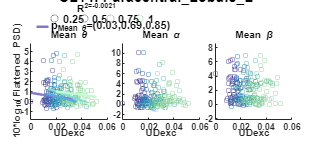



 CL14) Variable: mean_StanceDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE         tStat       pValue 
                                     ________    _______    _________    ________

    (Intercept)                      -0.54754    0.54728      -1.0005      0.3182
    cond_char_0.5                    -0.02535      1.021    -0.024828     0.98021
    cond_char_0.75                   -0.58095     1.3932     -0.41698     0.67711
    cond_char_1.0                     -1.0501     1.7375     -0.60434     0.54625
    mean_StanceDur                     0.6769    0.30882       2.1919    0.029456
    cond_char_0.5:mean_StanceDur      0.39091    0.85234      0.45864     0.64696
    

                                SumOfSquares    DF     MeanSquares       F        pValue 
                                ____________    ___    ___________    _______    ________

    cond_char                     0.54088         3      0.18029      0.16869     0.91743
    mean_StanceDur                 6.7923         1       6.7923        6.355    0.012427
    cond_char:mean_StanceDur       2.4296         3      0.80987      0.75773     0.51896
    Error                          230.86       216       1.0688                         
    Total                          243.72       223                                      





 CL14) Variable: mean_StanceDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue 
                                     ________    _______    ________    ________

    (Intercept)                         2.036     1.0057      2.0244    0.044156
    cond_char_0.5                      1.0482     1.8763     0.55866     0.57698
    cond_char_0.75                     1.7276     2.5603     0.67477     0.50055
    cond_char_1.0                     0.17118      3.193    0.053611     0.95729
    mean_StanceDur                   -0.33253    0.56751    -0.58594     0.55852
    cond_char_0.5:mean_StanceDur      -1.4341     1.5663    -0.91561     0.36089
    

                                SumOfSquares    DF     MeanSquares       F       pValue 
                                ____________    ___    ___________    _______    _______

    cond_char                      2.3307         3      0.77688      0.21524    0.88577
    mean_StanceDur                 5.6272         1       5.6272        1.559    0.21316
    cond_char:mean_StanceDur        6.206         3       2.0687      0.57313    0.63327
    Error                          779.64       216       3.6094                        
    Total                          794.85       223                                     





 CL14) Variable: mean_StanceDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_StanceDur

Estimated Coefficients:
                                     Estimate      SE        tStat       pValue  
                                     ________    _______    _______    __________

    (Intercept)                        3.7681    0.90286     4.1735    4.3482e-05
    cond_char_0.5                       1.054     1.6844    0.62572       0.53216
    cond_char_0.75                     2.7007     2.2985      1.175       0.24129
    cond_char_1.0                      1.7613     2.8665    0.61443       0.53958
    mean_StanceDur                   -0.94634    0.50947    -1.8575      0.064601
    cond_char_0.5:mean_StanceDur      -1.6777     1.4061    -1.1932       0.23412
    <

                                SumOfSquares    DF     MeanSquares       F        pValue  
                                ____________    ___    ___________    _______    _________

    cond_char                      4.9656         3      1.6552       0.56901      0.63599
    mean_StanceDur                 25.821         1      25.821        8.8764    0.0032193
    cond_char:mean_StanceDur       15.044         3      5.0145        1.7239      0.16305
    Error                          628.32       216      2.9089                           
    Total                          671.32       223                                       



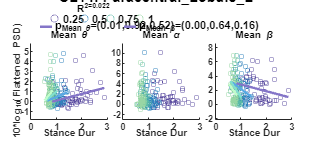



 CL14) Variable: mean_GaitCycleDur, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                         -0.58683    0.57479      -1.021     0.30842
    cond_char_0.5                        0.11486     1.0359     0.11088     0.91182
    cond_char_0.75                      -0.62054     1.3512    -0.45924     0.64652
    cond_char_1.0                        -1.1066     1.6519    -0.66992     0.50362
    mean_GaitCycleDur                    0.51636    0.24009      2.1507    0.032611
    cond_char_0.5:mean_GaitCycleDur      0.13511    0.58326     0.231

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    _______    ________

    cond_char                        0.73668         3      0.24556      0.23015     0.87533
    mean_GaitCycleDur                 8.1271         1       8.1271       7.6172    0.006278
    cond_char:mean_GaitCycleDur       2.4269         3      0.80897      0.75821     0.51868
    Error                             230.46       216       1.0669                         
    Total                             243.72       223                                      





 CL14) Variable: mean_GaitCycleDur, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue 
                                        ________    _______    ________    ________

    (Intercept)                            1.834     1.0593      1.7314    0.084807
    cond_char_0.5                         1.1347     1.9091     0.59437     0.55289
    cond_char_0.75                        1.3748     2.4901     0.55208     0.58147
    cond_char_1.0                       0.035661     3.0442    0.011714     0.99066
    mean_GaitCycleDur                   -0.15843    0.44246    -0.35808     0.72063
    cond_char_0.5:mean_GaitCycleDur     -0.95157     1.0749    -0.885

                                   SumOfSquares    DF     MeanSquares       F       pValue 
                                   ____________    ___    ___________    _______    _______

    cond_char                         2.0139         3      0.6713       0.18526    0.90635
    mean_GaitCycleDur                 4.1208         1      4.1208        1.1372    0.28743
    cond_char:mean_GaitCycleDur       4.7508         3      1.5836       0.43703    0.72672
    Error                             782.69       216      3.6235                         
    Total                             794.85       223                                     





 CL14) Variable: mean_GaitCycleDur, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_GaitCycleDur

Estimated Coefficients:
                                        Estimate      SE        tStat       pValue  
                                        ________    _______    _______    __________

    (Intercept)                           3.8015    0.94905     4.0056    8.5121e-05
    cond_char_0.5                         1.1333     1.7105    0.66257       0.50831
    cond_char_0.75                        2.2741      2.231     1.0193        0.3092
    cond_char_1.0                         1.7852     2.7274    0.65454       0.51346
    mean_GaitCycleDur                   -0.71262    0.39642    -1.7976      0.073631
    cond_char_0.5:mean_GaitCycleDur      -1.1137    0.96303    

                                   SumOfSquares    DF     MeanSquares       F        pValue 
                                   ____________    ___    ___________    _______    ________

    cond_char                         4.1437         3      1.3812       0.47486     0.70011
    mean_GaitCycleDur                 28.578         1      28.578        9.8247    0.001961
    cond_char:mean_GaitCycleDur       12.692         3      4.2306        1.4545     0.22798
    Error                             628.29       216      2.9087                          
    Total                             671.32       223                                      



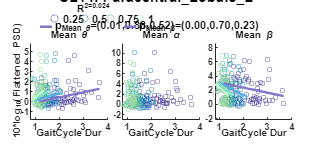



 CL14) Variable: mean_PeakUpDownVel_mean, EEG_band: theta_avg_power

Linear regression model:
    theta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat       pValue 
                                              ________    _______    ________    ________

    (Intercept)                                0.93194    0.49785      1.8719    0.062568
    cond_char_0.5                             0.025223    0.83747    0.030118       0.976
    cond_char_0.75                              1.1139    0.91908      1.2119     0.22686
    cond_char_1.0                               1.2094    0.96562      1.2524     0.21177
    mean_PeakUpDownVel_mean                    -2.7656     4.1467    -0.66696     0.50551
    cond_char_0.5:mean_PeakUpD

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    _______    ________

    cond_char                               3.0095         3       1.0032      0.92186     0.43107
    mean_PeakUpDownVel_mean                 4.5042         1       4.5042       4.1392    0.043124
    cond_char:mean_PeakUpDownVel_mean      0.47295         3      0.15765      0.14487     0.93288
    Error                                   235.05       216       1.0882                         
    Total                                   243.72       223                                      





 CL14) Variable: mean_PeakUpDownVel_mean, EEG_band: alpha_avg_power

Linear regression model:
    alpha_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate       SE         tStat       pValue 
                                              _________    _______    _________    ________

    (Intercept)                                  2.0467    0.90998       2.2491    0.025512
    cond_char_0.5                             -0.018816     1.5307    -0.012292      0.9902
    cond_char_0.75                               -1.307     1.6799     -0.77799     0.43743
    cond_char_1.0                               -1.9394      1.765      -1.0988     0.27307
    mean_PeakUpDownVel_mean                     -5.0398     7.5794     -0.66494      0.5068
    cond_char_0.

                                         SumOfSquares    DF     MeanSquares       F       pValue 
                                         ____________    ___    ___________    _______    _______

    cond_char                               6.1174         3       2.0391      0.56088    0.64139
    mean_PeakUpDownVel_mean                0.71338         1      0.71338      0.19622    0.65823
    cond_char:mean_PeakUpDownVel_mean       5.7323         3       1.9108      0.52557    0.66516
    Error                                   785.29       216       3.6356                        
    Total                                   794.85       223                                     





 CL14) Variable: mean_PeakUpDownVel_mean, EEG_band: beta_avg_power

Linear regression model:
    beta_avg_power ~ 1 + cond_char*mean_PeakUpDownVel_mean

Estimated Coefficients:
                                              Estimate      SE        tStat      pValue  
                                              ________    _______    _______    _________

    (Intercept)                                2.9842     0.83472     3.5751    0.0004319
    cond_char_0.5                             -1.7982      1.4041    -1.2807      0.20168
    cond_char_0.75                            -1.8284       1.541    -1.1866      0.23671
    cond_char_1.0                             -2.2228       1.619     -1.373      0.17119
    mean_PeakUpDownVel_mean                    -7.278      6.9525    -1.0468      0.29635
    cond_char_0.5:mean_PeakUpDo

                                         SumOfSquares    DF     MeanSquares       F        pValue 
                                         ____________    ___    ___________    ________    _______

    cond_char                               9.4537         3       3.1512        1.0301    0.38012
    mean_PeakUpDownVel_mean                0.14342         1      0.14342      0.046883    0.82878
    cond_char:mean_PeakUpDownVel_mean       6.1183         3       2.0394       0.66668    0.57335
    Error                                   660.76       216       3.0591                         
    Total                                   671.32       223                                      



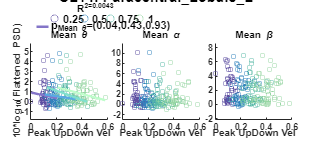

for cl_i = 1:length(clusters)
    %##
    for var_i = 1:length(varnames)
        %%
        atlas_name = atlas_name_store{cl_i};
        fig = figure('color','white','renderer','Painters');
        sgtitle(atlas_name,'FontName',PLOT_STRUCT.font_name,'FontSize',12,'FontWeight','bold','Interpreter','none');
        set(fig,'Units','inches','Position',[0.5,0.5,6.5,3])
        set(fig,'PaperUnits','inches','PaperSize',[1 1],'PaperPosition',[0 0 1 1])
        hold on;
        set(gca,AXES_DEFAULT_PROPS{:})
        vert_shift = 0;
        for des_i = 2
            switch des_i
                case 1
                    color_dark = COLORS_MAPS_TERRAIN;
                    color_light = COLORS_MAPS_TERRAIN;
                    GROUP_CMAP_OFFSET = [0,0.1,0.1];
                    xtick_label_g = {'flat','low','med','high'};
                case 2
                    color_dark = COLOR_MAPS_SPEED;
                    color_light = COLOR_MAPS_SPEED+0.15;
                    GROUP_CMAP_OFFSET = [0.15,0,0];
                    xtick_label_g = {'0.25','0.50','0.75','1.0'};
            end
            horiz_shift = 0;
            stats_store = [];
            for meas_i = 1:length(measure_name_plot)
                measure_name = measure_name_plot{meas_i};
                %##
                cond_plot_store = [];
                % inds = psd_feature_stats.study == num2str(des_i) & psd_feature_stats.cluster == num2str(cl_i) & psd_feature_stats.group==groups(group_i);
                % T_stats_plot = psd_feature_stats(inds,:);
                inds = TMP_FOOOF_T.design_id == designs(des_i) & TMP_FOOOF_T.cluster_id == clusters(cl_i);
                T_vals_plot = TMP_FOOOF_T(inds,:);
                % T_vals_plot.cond_char = double(string(T_vals_plot.cond_char));
                loc_cond_chars = unique(T_vals_plot.cond_char);
                y_lim_calc = [min(T_vals_plot.(measure_name))-std(T_vals_plot.(measure_name)),max(T_vals_plot.(measure_name))+std(T_vals_plot.(measure_name))];
                T_vals_plot = table(double(T_vals_plot.(measure_name)),categorical(string(T_vals_plot.cond_char)),categorical(string(T_vals_plot.group_char)),double(T_vals_plot.(varnames{var_i})),...
                    'VariableNames',{measure_name,'cond_char','group_char',varnames{var_i}});
                try
                    mod = sprintf('%s ~ 1 + cond_char + %s + cond_char:%s',measure_name,varnames{var_i},varnames{var_i});
                    % stats_out = fitlme(T_vals_plot,mod);
                    stats_out = fitlm(T_vals_plot,mod);
                    % anova_out = anova(stats_out);
                    out = anova(T_vals_plot,mod,'SumOfSquaresType',"three",'CategoricalFactors',{'cond_char'},...
                            'ModelSpecification','linear');
                    anova_out = out.stats();
                    % anova_out = anovan(double(T_vals_plot.(measure_name)),{T_vals_plot.group_char,T_vals_plot.cond_char},...
                    %         'model','interaction',...
                    %         'model',2,...
                    %         'sstype',3,...
                    %         'varnames',strvcat('group','speed'));
                    R2 = stats_out.Rsquared.Adjusted;
                    fprintf('\n\n CL%s) Variable: %s, EEG_band: %s',string(clusters(cl_i)),varnames{var_i},measure_name)
                    disp(stats_out)
                    disp(anova_out);
                    % %## PRINT TABLES
                    % t = sprintf_table(anova_out);
                    % t.saveToFile([tmp_savedir filesep sprintf('cl%s_%s_%s_ANOVA.txt',string(clusters(cl_i)),varnames{var_i},measure_name)]);
                    % t = sprintf_table(stats_out.Coefficients);
                    % t.saveToFile([tmp_savedir filesep sprintf('cl%s_%s_%s_LM.txt',string(clusters(cl_i)),varnames{var_i},measure_name)]);
                    %-
                    anova_p_cond = anova_out.pValue(strcmp(anova_out.Properties.RowNames,'cond_char'));
                    anova_p_var = anova_out.pValue(strcmp(anova_out.Properties.RowNames,varnames{var_i}));
                    anova_p_inter = anova_out.pValue(strcmp(anova_out.Properties.RowNames,sprintf('cond_char:%s',varnames{var_i})));
                    %-
                    pval_inter = double(stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'(Intercept)')));
                    pval_0p5 = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_0.5'));
                    pval_0p75 = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_0.75'));
                    pval_1p0 = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_1.0'));
                    pval_var = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,varnames{var_i}));
                    pval_0p5_var = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('cond_char_0.5:%s',varnames{var_i})));
                    pval_0p75_var = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('cond_char_0.75:%s',varnames{var_i})));
                    pval_1p0_var = stats_out.Coefficients.pValue(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('cond_char_1.0:%s',varnames{var_i})));
                    %-
                    slope_inter = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'(Intercept)')));
                    slope_0p5 = stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_0.5'));
                    slope_0p75 = stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_0.75'));
                    slope_1p0 = stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,'cond_char_1.0'));
                    slope_var = stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,varnames{var_i}));
                    slope_0p5_var = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('cond_char_0.5:%s',varnames{var_i}))));
                    slope_0p75_var = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('cond_char_0.75:%s',varnames{var_i}))));
                    slope_1p0_var = double(stats_out.Coefficients.Estimate(strcmp(stats_out.Coefficients.Properties.RowNames,sprintf('cond_char_1.0:%s',varnames{var_i}))));
                catch e
                    fprintf('Error. Cluster %s\n\n%s\n',string(clusters(cl_i)),getReport(e))
                    R2 = 0;
                    pval = 1;
                    slope = 0;
                    inter = 0;
                end
                %## SCATTER
                axes();
                hold on;
                for cond_i = 1:length(loc_cond_chars)
                    inds = T_vals_plot.cond_char==loc_cond_chars(cond_i);
                    data = T_vals_plot(inds,:);
                    [vals,inds] = sort(data.(varnames{var_i}));
                    data = data(inds,:);
                    ss = scatter(data,varnames{var_i},measure_name,'DisplayName',sprintf('%s',GROUP_SHORTS{group_i}));
                    ss.CData = color_dark(cond_i,:);
                    ss.SizeData = 15;
                    ss.Marker = GROUP_MARKS{group_i};
                    if meas_i == 1
                        cond_plot_store = [cond_plot_store, ss];
                    end
                end
                %## LINEAR MODEL FIT
                hold on;
                for cond_i = 1:length(loc_cond_chars)
                    switch cond_i
                        case 1
                            c2 = 0;
                            c3 = 0;
                            c4 = 0;
                        case 2
                            c2 = 1;
                            c3 = 0;
                            c4 = 0;
                        case 3
                            c2 = 0;
                            c3 = 1;
                            c4 = 0;
                        case 4
                            c2 = 0;
                            c3 = 0;
                            c4 = 1;
                    end
                    inds = T_vals_plot.cond_char==loc_cond_chars(cond_i);
                    data = T_vals_plot(inds,:);
                    [vals,inds] = sort(data.(varnames{var_i}));
                    data = data(inds,:);
                    if anova_p_var < 0.05 || anova_p_cond < 0.05 || anova_p_inter < 0.05
                        x = unique(data.(varnames{var_i}));
                        y = [];
                        for i = 1:length(x)
                            y(i) = x(i)*slope_var + slope_0p5*c2 + slope_0p75*c3 + slope_1p0*c4 + slope_0p5_var*x(i)*c2 + slope_0p75_var*x(i)*c3 + slope_1p0_var*x(i)*c4 + slope_inter ;
                        end
                        pp = plot(x,y,...
                            'DisplayName',sprintf('p_{%s}=(%0.2f,%0.2f,%0.2f)',MEASURE_NAME_LABS{meas_i},anova_p_var,anova_p_cond,anova_p_inter),...
                            'LineWidth',2);
                        pp.LineStyle = GROUP_LINESTYLES{group_i};
                        pp.Color = color_light(cond_i,:);
                        if cond_i == 1
                            % eq = sprintf('y=(%0.1g)*x+(%0.1g)*%0.2f+(%0.1g)*x+(%0.1g)',slope_var,slope_cnd,loc_cond_chars(cond_i),slope_grp,inter_mn);
                            % eq = sprintf('y=(%0.1g)*x+(%0.1g)*c_i\n%6s+(%0.1g)',slope_var,slope_cnd,'',inter_mn);
                            eq = '';
                            x_txt = 0.15;
                            y_txt = 0.7;
                            if anova_p_var > 0.01 & anova_p_var < 0.05
                                text(x_txt,y_txt,sprintf('* %s\nR^2=%0.2g',eq,R2),...
                                    'FontSize',REGRESS_TXT_SIZE,...
                                    'FontName',PLOT_PARAMS.font_name,...
                                    'FontWeight','bold','Units','normalized');
                            elseif anova_p_var <= 0.01 & anova_p_var > 0.001 
                                text(x_txt,y_txt,sprintf('** %s\nR^2=%0.2g',eq,R2),...
                                    'FontSize',REGRESS_TXT_SIZE,...
                                    'FontName',PLOT_PARAMS.font_name,...
                                    'FontWeight','bold','Units','normalized');
                            else
                                text(x_txt,y_txt,sprintf('*** %s\nR^2=%0.2g',eq,R2),...
                                    'FontSize',REGRESS_TXT_SIZE,...
                                    'FontName',PLOT_PARAMS.font_name,...
                                    'FontWeight','bold','Units','normalized');
                            end
                            stats_store = [stats_store, pp];
                        end
                    end
                end
                if meas_i ==1
                    ylabel('10*log_{10}(Flattened PSD)');
                else
                    ylabel('');
                end
                xlabel(varnames_labs{var_i});
                title(MEASURE_NAME_LABS{meas_i});
                set(gca,'FontWeight','bold');
                ylim(y_lim_calc)
                %## legend
                if meas_i == 1
                    %- lg2
                    legend(gca,cond_plot_store);
                    [lg2,icons,plots,txt]  = legend('boxoff');
                    tmp = get(lg2,'String');
                    cnt = 1;
                    for i = 1:length(cond_plot_store)
                        tmp{i} = sprintf('%0.2g',double(string(loc_cond_chars(cnt))));
                        cnt = cnt + 1;
                    end
                    set(lg2,'String',tmp,'FontName','Arial','FontSize',9)
                    set(lg2,'Orientation','horizontal')
                    set(lg2,'Position',[0.1,0.84,lg2.Position(3),lg2.Position(4)]);
                    lg2.ItemTokenSize(1) = 18;
                elseif meas_i == 2
                    % %- lg1
                    % legend(gca,group_plot_store);
                    % [lg1,icons,plots,txt] = legend('boxoff');
                    % set(lg1,'Orientation','horizontal')
                    % set(lg1,'FontName','Arial','FontSize',9)
                    % % set(lg1,'Position',[0.1,SCATTER_BOTTOM+AX_W*im_resize-vert_shift,lg1.Position(3),lg1.Position(4)]);
                    % set(lg1,'Position',[0.1,SCATTER_BOTTOM+AX_W*im_resize-vert_shift+0.025,lg1.Position(3),lg1.Position(4)]);
                    % lg1.ItemTokenSize(1) = 18;
                elseif meas_i == 3
                    %- lg3
                    if ~isempty(stats_store)
                        legend(gca,stats_store);
                        [lg3,~,~,~] = legend('boxoff');
                        set(lg3,'Orientation','horizontal')
                        set(lg3,'FontName','Arial','FontSize',9)
                        % set(lg1,'Position',[0.1,SCATTER_BOTTOM+AX_W*im_resize-vert_shift,lg1.Position(3),lg1.Position(4)]);
                        set(lg3,'Position',[0.1,0.775,lg3.Position(3),lg3.Position(4)]);
                        lg3.ItemTokenSize(1) = 18;
                    end
                end
                set(gca,'Position',[horiz_shift+0.1,SCATTER_BOTTOM-vert_shift,AX_W*im_resize,AX_H*im_resize]);  %[left bottom width height]
                horiz_shift = horiz_shift + AX_W*im_resize + 0.05;
            end
            %## TITLE
            % annotation('textbox',[0.5-0.1,SCATTER_BOTTOM-vert_shift-0.05+AX_H*im_resize,0.2,0.2],...
            %     'String',string(design_chars(des_i)),'HorizontalAlignment','center',...
            %     'VerticalAlignment','middle','LineStyle','none','FontName',PLOT_PARAMS.font_name,...
            %     'FontSize',14,'FontWeight','Bold','Units','normalized');
            % vert_shift = vert_shift + AX_H*im_resize+0.1;
        end
        hold off;
        %##
        % exportgraphics(fig,[tmp_savedir filesep sprintf('cl%s_%s_eeg-kin-speed-inter.tiff',string(clusters(cl_i)),varnames{var_i})],'Resolution',300)
        % close(fig)
    end
end